## SHALLOW LEARNING

#### Playing with MATLAB's FITRNET Function

Inbuilt function to train a regression neural net

This appears to just be an ANN

rng("default")

N = 15000; %datapoints
m = 10; %num input features
input_data = [rand(N,m)] %input data normalised to btwn 0 and 1

input_data =     0.8147    0.2858    0.8252    0.1839    0.6388    0.3175    0.8937    0.2068    0.0886    0.3919
    0.9058    0.9312    0.0908    0.0488    0.2237    0.6382    0.8162    0.4302    0.4828    0.6212
    0.1270    0.7999    0.2064    0.5280    0.1693    0.2119    0.9474    0.9661    0.9015    0.4001
    0.9134    0.3311    0.7932    0.6577    0.3909    0.4541    0.2403    0.8127    0.5778    0.4569
    0.6324    0.7374    0.6817    0.3300    0.4590    0.5029    0.5797    0.6967    0.9693    0.3711
    0.0975    0.5674    0.4700    0.1683    0.8454    0.7209    0.1888    0.1507    0.4572    0.4465
    0.2785    0.0161    0.8978    0.1655    0.5333    0.5400    0.3513    0.8656    0.8015    0.2468
    0.5469    0.4255    0.4085    0.0459    0.0713    0.1541    0.6063    0.7257    0.3339    0.0212
    0.9575    0.0294    0.6585    0.2291    0.3536    0.1219    0.6446    0.5820    0.1271    0.1138
    0.9649    0.7842    0.9584    0.5768    0.9280    0.5349    0.6153    0.12


powers = randi([1,6],[1,m])

powers =      5     3     5     1     5     1     6     2     5     6


coeffs = [randn(m,1)]

coeffs =     0.6616
   -0.1329
    1.6312
    1.6487
   -0.2863
    0.6266
    0.8173
   -0.9155
    0.0620
    1.6330


const = rand(1)

const = 0.2846

actual_model = @(X) X*coeffs+const + 0.2.*sin(X*coeffs);

[output_data, shift, scale] = normalize(actual_model(input_data))

output_data =     0.4975
   -0.4860
   -1.0178
    0.4903
   -0.1764
   -0.8510
   -0.8117
   -2.0834
   -0.6044
    2.5352


shift = 3.1847

scale = 0.8260


partition_variable = cvpartition(N, "Holdout",0.3);
trainingIndices = training(partition_variable);
trainInput = input_data(trainingIndices,:);
trainOutput = output_data(trainingIndices,:);

testIndices = test(partition_variable);
testInput = input_data(testIndices,:);
testOutput = output_data(testIndices,:);


allModels = {};
i = 1;
lambda = [1e-8,1e-7, 1e-6,1e-5, 2e-5, 1e-4, 2e-4, 5e-4, 1e-3, 2e-3, 5e-3, 0.01, 0.02, 0.04, 0.08, 0.16, 0.32, 0.64, 1.28];

for L = drange(lambda)
    allModels(i) = {fitrnet(trainInput, trainOutput, 'Standardize', false, ...
    'LayerSizes', [5,5], 'Lambda', L)};
    i = i+1;
end

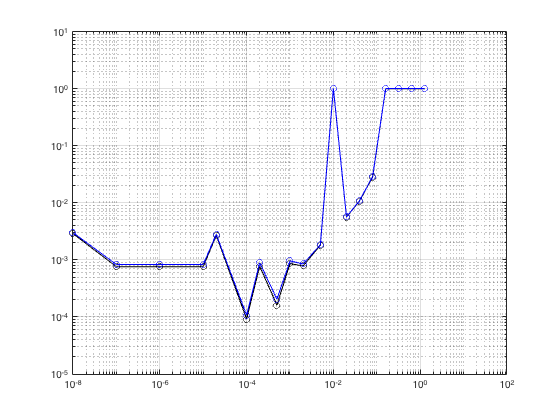


trainLoss = [];
testLoss = [];
for i=1:length(lambda)
    trainLoss(i) = loss(allModels{i}, trainInput, trainOutput);;
    testLoss(i) = loss(allModels{i}, testInput, testOutput);
end
clf
loglog(lambda, trainLoss, '-ok')
hold on
loglog(lambda, testLoss, '-ob')

grid on

InputCheck = rand([1,10])
fprintf('Actual -> %.4f', actual_model(InputCheck))
fprintf('Predicted -> %.4f', predict(allModels{3}, InputCheck)*scale+shift)


#### Playing with Patternnet

Same example as above

The perform function uses MSE but seems to be a lot higher than just calculating the MSE myself??

net = patternnet([5,5]);
% net.numInputs = m;
net.layers{1}.transferFcn = 'purelin';
net.layers{2}.transferFcn = 'purelin';
net.layers{3}.transferFcn = 'purelin';
% net.performParam.regularization = 1e-4;
net.performFcn = 'mse';
% net.inputConnect = [ones(1,m); zeros(2,m)];
% net.trainFcn = 'trainbfg';
% view(net)
% trainInputCell = mat2cell(trainInput', [ones(1,m)], [length(trainInput)]);
% trainOutputCell = mat2cell(trainOutput', [ones(1,1)], [length(trainOutput)]);
% 
% testInputCell = mat2cell(testInput', [ones(1,m)], [length(testInput)]);
% testOutputCell = mat2cell(testOutput', [ones(1,1)], [length(testOutput)]);

% net = train(net, trainInput', trainOutput')
% perform(net, testInput', testOutput')


mse_history = [];
training_data_sizes = floor(logspace(0,4,12));
for i=training_data_sizes
    tempnet = net; %must reset net between iterations
%     trainInputCell = mat2cell(trainInput(1:i,:)', [ones(1,m)], [i]);
%     trainOutputCell = mat2cell(trainOutput(1:i,:)', [ones(1,1)], [i]);

    tempnet = train(tempnet, trainInput(1:i,:)', trainOutput(1:i,:)');
%     [i, perform(tempnet, trainInput, trainOutput), perform(tempnet, testInput, testOutput)]
    mse_history = [mse_history; mean((trainOutput' - tempnet(trainInput')).^2), mean((testOutput' - tempnet(testInput')).^2)];
end
net = tempnet;

clf
loglog(training_data_sizes, mse_history(:,1))
hold on
loglog(training_data_sizes, mse_history(:,2))
grid on
xlabel("Size of Dataset")
ylabel("MSE")

InputCheck = rand([10,1]);
fprintf('Actual -> %.4f', actual_model(InputCheck'))
fprintf('Predicted -> %.4f', tempnet(InputCheck)*scale+shift)

play_in = 0:0.05:1;
clf
plot(play_in, actual_model([play_in', zeros(length(play_in),m-1)]))
hold on
plot(play_in, net([play_in', zeros(length(play_in),m-1)]'))
grid on


#### Random Forest

Was used by Q. Xie in "Machine Learning Methods for Real-Time Blood Pressure Measurement Based on Photoplethysmography". There is a high level Matlab way to implement but requires reading up about the technique a bit and considering properties properly

#### LSTM 

Was used by L. Harfiya in "Continuous Blood Pressure Estimation Using Exclusively Photopletysmography by LSTM-Based Signal-to-Signal Translation". There is a high level Matlab way to implement but requires reading up about the technique a bit and considering properties properly

#### Support Vector Machine Regression

https://towardsdatascience.com/unlocking-the-true-power-of-support-vector-regression-847fd123a4a0

rsvmModel = fitrsvm(trainInput, trainOutput);

frpintf("Converged? %i", rsvmModel.ConvergenceInfo.Converged)

rsvmModel

i = randi(length(testInput));
fprintf("Actual Model -> %.4f", actual_model(testInput(i,:)))
fprintf("Predicted Model -> %.4f", predict(rsvmModel, testInput(i,:)).*scale+shift)



### Playing With Actual Data

%for feature files if the files are too big, tall arrays may be needed
[inputdata, outputdata, normFactors] = MLFeatureRead();

Removed 0 rows from datainput features has 13725 rows and 612 columns 
output features has 13725 rows and 605 columns 


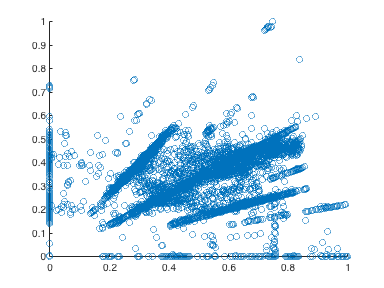


partition_variable = cvpartition(height(inputdata), "Holdout",0.25);
trainingIndices = training(partition_variable);
trainInput = inputdata(trainingIndices,:);
trainOutput = outputdata(trainingIndices,:);

testIndices = test(partition_variable);
testInput = inputdata(testIndices,:);
testOutput = outputdata(testIndices,:);

clf
scatter(inputdata.PPGBW, outputdata.ABPBW)

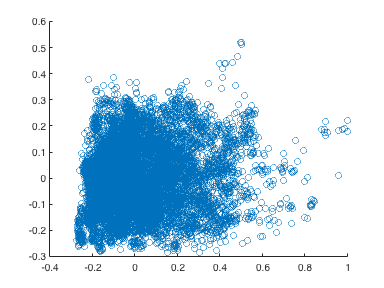

% xtitle("PPG Bandwidth(norm)")
% ytitle("ABP Bandwidth(norm)")

clf
scatter(inputdata.CT, outputdata.MAP)

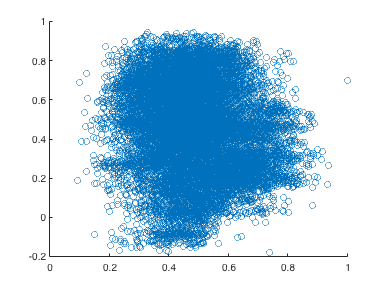


clf
scatter(inputdata.RespRate, outputdata.MeanSBP)

#### rSVM

rsvmmodel = fitrsvm(trainInput, trainOutput.MAP, 'KernelFunction', 'linear','KernelScale', 1);

actualMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedMAP = predict(rsvmmodel, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedMAP-actualMAP)./actualMAP;
% testingError = testingError(find(~isnan(testingError)));

actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(rsvmmodel, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = (predictedTrainMAP-actualTrainMAP)./actualTrainMAP;
% trainingError = trainingError(find(~isnan(trainingError)));

fprintf("Average MAP test error: %.2f%%", mean(abs(testingError(find(~isnan(testingError))))).*100)

Average MAP test error: 9.32%

fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError(find(~isnan(trainingError))))).*100)

Average MAP train error: 9.16%

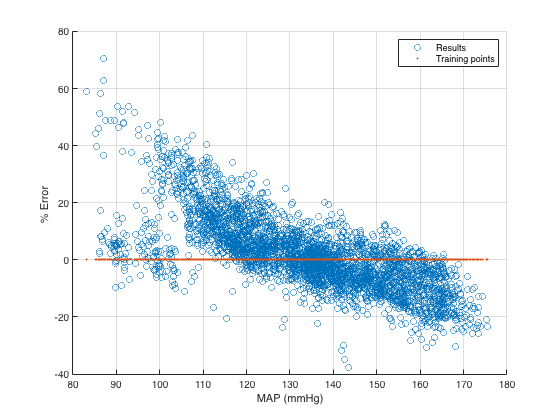


clf
scatter(actualMAP, testingError.*100);
hold on
scatter(actualMAP, 0.*actualMAP, '.')
xlabel("MAP (mmHg)")
ylabel("% Error ")
grid on
legend("Results", "Training points")

rng default
rsvmmodel_opt = fitrsvm(trainInput, trainOutput.MAP, 'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus', 'UseParallel', true));

Copying objective function to workers...
Done copying objective function to workers.
|==============================================================================================================================|
| Iter | Active  | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |      Epsilon |
|      | workers | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              |
|==============================================================================================================================|
|    1 |       3 | Best   |    0.015215 |      6.6696 |    0.015215 |    0.015215 |       27.209 |     0.011201 |       2.7307 |
|    2 |       3 | Accept |    0.015215 |      6.9131 |    0.015215 |    0.015215 |     0.011062 |       545.55 |       7.2124 |
|    3 |       4 | Accept |    0.015215 |      3.7663 |    0.015215 |    0.015215 |       16.258 |     0.011103 |        11.56 |
|    4 |    


actualMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedMAP = predict(rsvmmodel_opt, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedMAP-actualMAP)./actualMAP;

actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(rsvmmodel_opt, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = (predictedTrainMAP-actualTrainMAP)./actualTrainMAP;


clf
scatter(actualMAP, testingError.*100);
xlabel("MAP (mmHg)")
ylabel("% Error ")
grid on

fprintf("Average MAP test error: %.2f%%", mean(abs(testingError)).*100)
fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError)).*100)

#### ANNs with Extracted Feature Inputs 

**Layers: [5,5]**

rnetModels2_5={};
dataSizes = floor(logspace(0, log10(height(trainInput)),20 ));
trainingError=[];
testingError=[];


for idx=1:length(dataSizes)
    N = dataSizes(idx);
    rnetModels2_5{idx} = fitrnet(trainInput(1:N,:), trainOutput.MAP(1:N), 'Standardize', false, ...
        'LayerSizes', [5,5], 'Lambda', 0);

    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels2_5{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);

    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels2_5{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end

clf
semilogx(dataSizes, trainingError.*100, 'o-')
hold on
semilogx(dataSizes, testingError.*100, '*-')
legend("Train", "Test")
ylim([0,45])
title("[5,5]")
xlabel("Training Set Size")
ylabel("Mean Absolute Error (%)")
grid on

clf
% scatter(actualTestMAP, actualTestMAP, '.')
hold on
scatter(actualTestMAP, (predictedTestMAP-actualTestMAP)./actualTestMAP.*100 )
xlabel("MAP (mmHg)")
ylabel("MAE (%)")
grid on

% fprintf("-- rANN --")
% fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError)).*100)
% fprintf("Average MAP test error: %.2f%%", mean(abs(testingError)).*100)


rnetModels2_5a = fitrnet(trainInput, trainOutput.MAP, 'Standardize', false, ...
    'LayerSizes', [5,5], 'Lambda', 0);


actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestMAP = predict(rnetModels2_5a, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
% notNanIdx = find(~isnan(predictedTestMAP));
% predictedTestMAP  = predictedTestMAP(notNanIdx);
% actualTestMAP = actualTestMAP(notNanIdx);
testingError = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP)

testingError = 0.0746

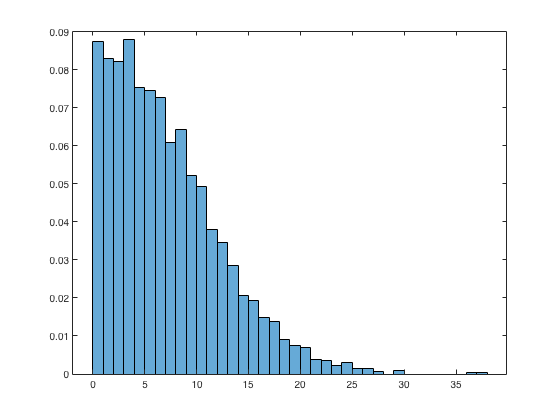

clf
histogram(abs(actualTestMAP-predictedTestMAP), 'Normalization', 'probability')


actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(rnetModels2_5a, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
% notNanIdx = find(~isnan(predictedTrainMAP));
% predictedTrainMAP  = predictedTrainMAP(notNanIdx);
% actualTrainMAP = actualTrainMAP(notNanIdx);
trainingError = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP)

trainingError = 0.0732


fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError)).*100)

Average MAP train error: 7.32%

fprintf("Average MAP test error: %.2f%%", mean(abs(testingError)).*100)

Average MAP test error: 7.46%

fprintf("Probs of error less than 10 mmHg: %2.2f%%", 100*sum(abs(actualTestMAP-predictedTestMAP)<10)./length(actualTestMAP))

Probs of error less than 10 mmHg: 74.00%

fprintf("μ ± SD: %3.2f ± %3.2f mmHg ", mean(abs(actualTestMAP-predictedTestMAP)), std(abs(actualTestMAP-predictedTestMAP)) )

μ ± SD: 7.13 ± 5.31 mmHg 

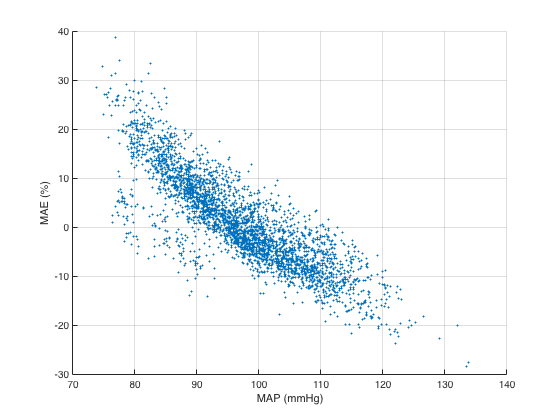



clf
% scatter(actualTestMAP, actualTestMAP, '.')
hold on
scatter(actualTestMAP, (predictedTestMAP-actualTestMAP)./actualTestMAP.*100,'.' )
xlabel("MAP (mmHg)")
ylabel("MAE (%)")
grid on

#### Layers: [50,50, 50, 50]

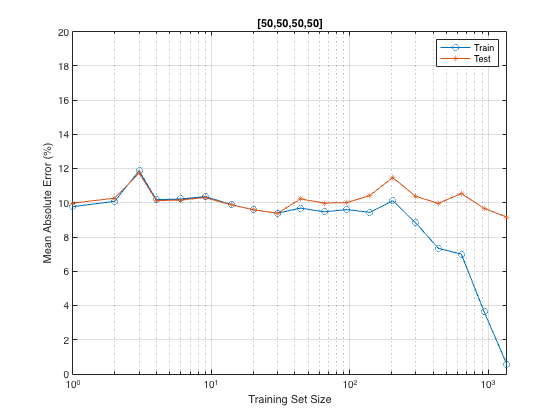

rnetModels4_50={};
dataSizes = floor(logspace(0, log10(height(trainInput)),20 ));
L = floor(logspace(-3, log10(2), 20));
trainingError=[];
testingError=[];


for idx=1:length(dataSizes)
    N = dataSizes(idx);
    rnetModels4_50{idx} = fitrnet(trainInput(1:N,:), trainOutput.MAP(1:N), 'Standardize', false, ...
        'LayerSizes', [50,50,50,50], 'Lambda', 0.001);
    
    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels4_50{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);
    
    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels4_50{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end
clf
semilogx(dataSizes, trainingError.*100, 'o-')
hold on
semilogx(dataSizes, testingError.*100, '*-')
legend("Train", "Test")
title("[50,50,50,50]")
ylim([0,20])
xlabel("Training Set Size")
ylabel("Mean Absolute Error (%)")
grid on

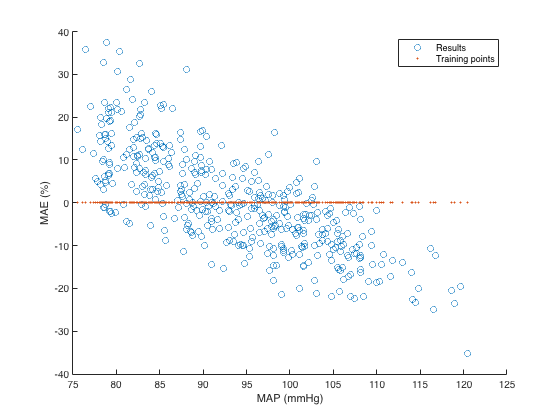




tErr = predict(rnetModels4_50{20}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
clf
scatter(actualTestMAP, (tErr-actualTestMAP)./actualTestMAP.*100)
hold on
scatter(actualTestMAP, 0.*actualTestMAP, '.')
xlabel("MAP (mmHg)")
ylabel("MAE (%)")
legend("Results", "Training points")

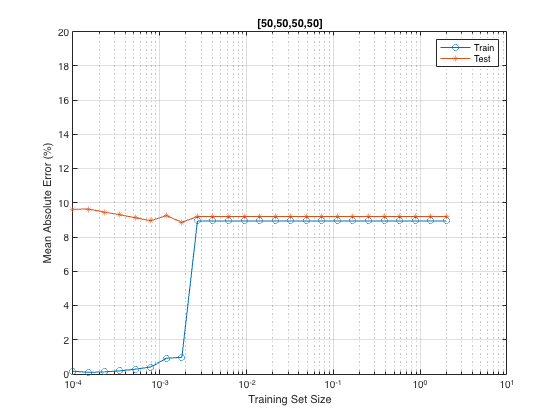

rnetModels4_50={};
L = logspace(-4, log10(2), 25);
trainingError=[];
testingError=[];

for idx=1:length(L)
    rnetModels4_50{idx} = fitrnet(trainInput, trainOutput.MAP, 'Standardize', false, ...
        'LayerSizes', [50,50,50,50], 'Lambda', L(idx));
    
    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels4_50{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);
    
    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels4_50{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end
clf
semilogx(L, trainingError.*100, 'o-')
hold on
semilogx(L, testingError.*100, '*-')
legend("Train", "Test")
title("[50,50,50,50]")
ylim([0,20])
xlabel("Training Set Size")
ylabel("Mean Absolute Error (%)")
grid on

#### Layers: [600]

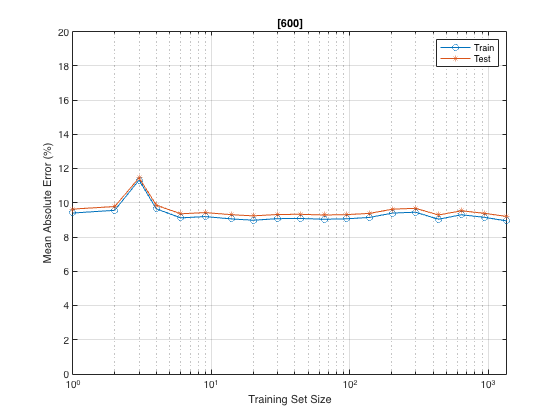

rnetModels1_600={};
dataSizes = floor(logspace(0, log10(height(trainInput)),5 ));
trainingError=[];
testingError=[];


for idx=1:length(dataSizes)
    N = dataSizes(idx);
    rnetModels1_600{idx} = fitrnet(trainInput(1:N,:), trainOutput.MAP(1:N), 'Standardize', false, ...
        'LayerSizes', [600], 'Lambda', 1);

    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels1_600{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);

    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels1_600{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end

clf
semilogx(dataSizes, trainingError.*100, 'o-')
hold on
semilogx(dataSizes, testingError.*100, '*-')
legend("Train", "Test")
title("[600]")
ylim([0,20])
xlabel("Training Set Size")
ylabel("Mean Absolute Error (%)")
grid on

% pool = parpool
rnetModels1_600a = fitrnet(trainInput, trainOutput.MAP, 'Standardize', true, ...
     'LayerSizes', [600], 'Lambda', 1e-3, 'Verbose',1, 'VerboseFrequency', 5)
actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestMAP = predict(rnetModels1_600a, testInput,'useParallel','yes')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP)

actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(rnetModels1_600a, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP)

fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError)).*100)
fprintf("Average MAP test error: %.2f%%", mean(abs(testingError)).*100)
fprintf("Probs of error less than 10 mmHg: %2.2f%%", 100*sum(abs(actualTestMAP-predictedTestMAP)<10)./length(actualTestMAP))
fprintf("μ ± SD: %3.2f ± %3.2f mmHg ", mean(abs(actualTestMAP-predictedTestMAP)), std(abs(actualTestMAP-predictedTestMAP)) )


clf
% scatter(actualTestMAP, actualTestMAP, '.')
hold on
scatter(actualTestMAP, (predictedTestMAP-actualTestMAP)./actualTestMAP.*100,'.' )
xlabel("MAP (mmHg)")
ylabel("MAE (%)")
grid on

rnetModels1_600={};
L = logspace(-4, log10(2), 5);
trainingError=[];
testingError=[];

parfor idx=1:length(L)
    fprintf("iter %i",idx)
    rnetModels1_600{idx} = fitrnet(trainInput, trainOutput.MAP, 'Standardize', false, ...
        'LayerSizes', [600], 'Lambda', L(idx));
    
    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels1_600{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);
    
    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels1_600{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end

iter 1iter 5iter 2iter 3iter 4

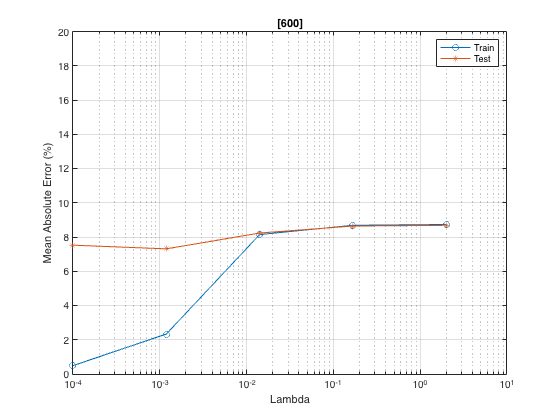

clf
semilogx(L, trainingError.*100, 'o-')
hold on
semilogx(L, testingError.*100, '*-')
legend("Train", "Test")
title("[600]")
ylim([0,20])
xlabel("Lambda")
ylabel("Mean Absolute Error (%)")
grid on

**Layers: [600,600,600]**

rnetModels3_600={};
L = logspace(-4, log10(2), 25);
trainingError=[];
testingError=[];

for idx=1:length(L)
    idx
    rnetModels3_600{idx} = fitrnet(trainInput, trainOutput.MAP, 'Standardize', false, ...
        'LayerSizes', [600,600,600], 'Lambda', L(idx));
    
    actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTestMAP = predict(rnetModels3_600{idx}, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingError(idx) = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);
    
    actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    predictedTrainMAP = predict(rnetModels3_600{idx}, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    trainingError(idx) = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);
end

idx = 1

idx = 2

idx = 3

clf
semilogx(L, trainingError.*100, 'o-')
hold on
semilogx(L, testingError.*100, '*-')
legend("Train", "Test")
title("[600,600,600]")
ylim([0,20])
xlabel("Training Set Size")
ylabel("Mean Absolute Error (%)")
grid on


rnetModels3_600a = fitrnet(trainInput, trainOutput.MAP, 'Standardize', false, ...
    'LayerSizes', [600,600,600], 'Lambda', 1e-3);

actualTestMAP = testOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestMAP = predict(rnetModels3_600a, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = mean(abs(predictedTestMAP-actualTestMAP)./actualTestMAP);

actualTrainMAP = trainOutput.MAP(:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(rnetModels3_600a, trainInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = mean(abs(predictedTrainMAP-actualTrainMAP)./actualTrainMAP);

fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError)).*100)

Average MAP train error: 4.95%

fprintf("Average MAP test error: %.2f%%", mean(abs(testingError)).*100)

Average MAP test error: 7.85%

fprintf("Probs of error less than 10 mmHg: %2.2f%%", 100*sum(abs(actualTestMAP-predictedTestMAP)<10)./length(actualTestMAP))

Probs of error less than 10 mmHg: 71.58%

fprintf("μ ± SD: %3.2f ± %3.2f mmHg ", mean(abs(actualTestMAP-predictedTestMAP)), std(abs(actualTestMAP-predictedTestMAP)) )

μ ± SD: 7.54 ± 5.75 mmHg 

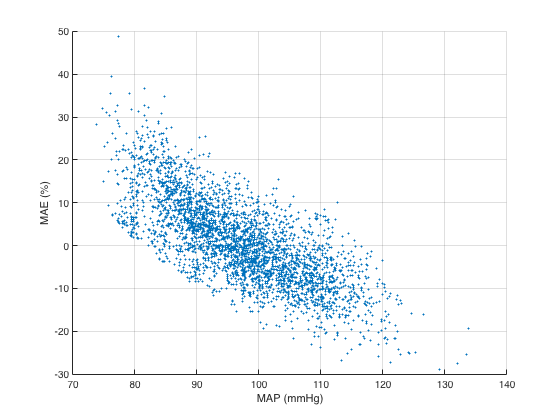


clf
% scatter(actualTestMAP, actualTestMAP, '.')
hold on
scatter(actualTestMAP, (predictedTestMAP-actualTestMAP)./actualTestMAP.*100,'.' )
xlabel("MAP (mmHg)")
ylabel("MAE (%)")
grid on

#### **LSTM With Extracted Features**

numFeatures = width(trainInput);

% trainInputLSTM = {};
% trainOutputLSTM = {};
% for i = 1:height(trainInput)
%     trainInputLSTM(i) = table2cell(trainInput(i,:));
%     trainOutputLSTM(i) = {trainOutput.MAP};
% end
% 
% testInputLSTM = {};
% testOutputLSTM = {};
% for i = 1:height(testInput)
%     testInputLSTM(i) = table2cell(testInput(i,:));
%     testOutputLSTM(i) = {testOutput.MAP};
% end


layers = [...
    sequenceInputLayer(numFeatures)
    batchNormalizationLayer
    bilstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    lstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    lstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    fullyConnectedLayer(1)
    regressionLayer]

layers =   10×1 Layer array with layers:

     1   ''   Sequence Input        Sequence input with 612 dimensions
     2   ''   Batch Normalization   Batch normalization
     3   ''   BiLSTM                BiLSTM with 128 hidden units
     4   ''   Batch Normalization   Batch normalization
     5   ''   LSTM                  LSTM with 128 hidden units
     6   ''   Batch Normalization   Batch normalization
     7   ''   LSTM                  LSTM with 128 hidden units
     8   ''   Batch Normalization   Batch normalization
     9   ''   Fully Connected       1 fully connected layer
    10   ''   Regression Output     mean-squared-error


%**should change test data to validation data
%loss function should be huber https://www.mathworks.com/help/deeplearning/ug/define-custom-regression-output-layer.html

% a = table2cell(trainInput);
% b = {};
% for i=1:height(trainOutput)
%     b(i) = {trainOutput.MAP};
% end
inputTrainLSTM = table2array(trainInput);
inputTrainLSTM  = reshape(inputTrainLSTM, [], height(trainInput));
outputTrainLSTM = [trainOutput.MAP]';
inputTestLSTM = table2array(testInput);
inputTestLSTM  = reshape(inputTestLSTM, [], height(testInput));
outputTestLSTM = [testOutput.MAP]';

options = trainingOptions('sgdm',...
    'MiniBatchSize', 32,...
    'InitialLearnRate', 0.001, ...
    'OutputNetwork', 'best-validation-loss', ...
    'ValidationData', {inputTestLSTM, outputTestLSTM}, ...
    'ExecutionEnvironment', 'cpu',...
    'MaxEpochs', 20,...
    'ValidationFrequency', 10,...
    'VerboseFrequency', 10)

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 20
                   MiniBatchSize: 32
                         Verbose: 1
                VerboseFrequency: 10
                  ValidationData: {[612×3431 double]  [0.0057 -0.1217 -0.0609 0.0297 -0.0649 -0.0125 -0.1734 -0.1717 0.0768 0.0683 -0.0180 -0.0968 -0.1431 -0.0437 -0.1355 -0.1480 -0.0636 0.0730 -0.0932 -0.0869 -0.0467 0.0246 0.0658 0.0950 0.1162 … ]}
             ValidationFrequency: 10
             


[netLSTM, info] = trainNetwork(inputTrainLSTM,outputTrainLSTM, layers, options)

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:27 |         1.68 |         3.23 |       1.4126 |       5.2202 |          0.0010 |


a = predict(netLSTM,inputTestLSTM).*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');  
b = outputTestLSTM.*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');

mean(abs(a-b))

ans = single
13.3325

options = trainingOptions('rmsprop',...
    'MiniBatchSize', 32,...
    'InitialLearnRate', 0.001, ...
    'ValidationData', {inputTestLSTM, outputTestLSTM}, ...
    'ExecutionEnvironment', 'gpu',...
    'MaxEpochs', 150,...
    'ValidationFrequency', 10,...
    'VerboseFrequency', 10)

#### LSTMs With Full Waveforms (Full PPG and ABP)

[https://www.mathworks.com/help/deeplearning/ug/long-short-term-memory-networks.html](https://www.mathworks.com/help/deeplearning/ug/long-short-term-memory-networks.html)

see sequence to sequence regression

[https://www.mathworks.com/help/deeplearning/ug/sequence-to-sequence-regression-using-deep-learning.html](https://www.mathworks.com/help/deeplearning/ug/sequence-to-sequence-regression-using-deep-learning.html)

**Extracting Interpolated Waveforms**

addSubPaths();
opts = readOptionsStruct();
fileList = dir(opts.segmented_file_dir+"*.txt");
numFiles = length(fileList);

inputFeats = [];
outputFeats = [];

interp_pts = 0:0.01:18;

for idx=1:numFiles
    fprintf("\b\b\b\b\b\b%6i", idx);

    dataFile = fopen(opts.segmented_file_dir + fileList(idx).name);
    if(dataFile == -1)
        inputFeatures = [];
        fprintf("%s not found. Returning from function.", opts.segmented_file_dir+segmentName)
        return; 
    end
    data = cell2mat(textscan( dataFile, ...
    '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
    fclose(dataFile);

    time = data(:,1);
    abp_wave = data(:,2);
    ppg_wave = data(:,3);

    interp_ppg = interp1(time, ppg_wave, interp_pts);
    interp_abp = interp1(time, abp_wave, interp_pts);
    [f, PPG_fft] = singlesidedFFT(interp_pts, interp_ppg);
    stopIdx = find(f >= 20,1);
    [~, ABP_fft] = singlesidedFFT(interp_pts, interp_abp);
    
    inputFeats(idx, :) = [abs(PPG_fft(1:stopIdx)), angle(PPG_fft(1:stopIdx))];
    outputFeats(idx,:) = [abs(ABP_fft(1:stopIdx)), angle(ABP_fft(1:stopIdx))];

end

  1818

partition_variable = cvpartition(height(inputFeats), "Holdout",0.25);
trainingIndices = training(partition_variable);
trainInputF = inputFeats(trainingIndices,:);
trainOutputF = outputFeats(trainingIndices,:);

testIndices = test(partition_variable);
testInputF = inputFeats(testIndices,:);
testOutputF = outputFeats(testIndices,:); 


**LSTM(200) - FC(50) **


numFeatures = width(trainInputF);
numResponses = width(trainOutputF);
numHiddenUnits = 200;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(50)
    dropoutLayer(0.1)
    fullyConnectedLayer(numResponses)
    regressionLayer];

maxEpochs = 60;
miniBatchSize = 20;

options = trainingOptions('adam', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'InitialLearnRate',0.01, ...
    'GradientThreshold',1, ...
    'Shuffle','never', ...
    'Plots','training-progress',...
    'Verbose',0);

net = trainNetwork(trainInputF',trainOutputF',layers,options);


YPred = predict(net,testInputF(200,:)','MiniBatchSize',1)
actFFT = testOutputF(200,1:362).*exp(i.*testOutputF(200,363:end));
PredFFT = YPred(1:362).*exp(i.*YPred(363:end));
deltaf = 1/(0.01.*1801);
[pred_time, pred_abp] = singlesidedIFFT([0:deltaf:20+deltaf], PredFFT);
[act_time, act_abp] = singlesidedIFFT([0:deltaf:20+deltaf], actFFT);

clf
plot(pred_time, pred_abp)
hold on
plot(act_time, act_abp)


Following LSTM from Paviglianiti et al. [https://link.springer.com/content/pdf/10.1007/s12559-021-09910-0.pdf](https://link.springer.com/content/pdf/10.1007/s12559-021-09910-0.pdf) 

**Extracting Full Waveforms With a 20% Overlap**

addSubPaths();
opts = readOptionsStruct();
load('NormalisationFactors.mat')
fileList = dir(opts.segmented_file_dir+"*.txt");
numFiles = length(fileList);

inputFeats = zeros(5000,1250);
outputFeats = zeros(5000,1250);

segLength = 10;
segOverlap = 0.2; %proportion that the interpolated points are allowed to overlap in the same segment 

numIndices = 0;
for idx=1:numFiles
    fprintf("\b\b\b\b\b\b%6i", idx);

    dataFile = fopen(opts.segmented_file_dir + fileList(idx).name);
    if(dataFile == -1)
        inputFeatures = [];
        fprintf("%s not found. Returning from function.", opts.segmented_file_dir+segmentName)
        continue; 
    end
    data = cell2mat(textscan( dataFile, ...
    '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
    fclose(dataFile);

    time = data(:,1);
    abp_wave = data(:,2);
    ppg_wave = data(:,3);

    numAvailableSegs = floor(time(end)/segLength*(1+segOverlap));
    
    for i = 1:numAvailableSegs
        numIndices = numIndices+1;
        startInterp = 10*(i-1)*(1-segOverlap);
        if(i == 1); startInterp = 0; end;
        endInterp = startInterp +10;
        interp_pts = linspace(startInterp,endInterp,1250);

        interp_ppg = interp1(time, ppg_wave, interp_pts);
        interp_ppg = (interp_ppg-normFactors('PPGAmpMean'))./normFactors('PPGAmpScale');
        interp_abp = interp1(time, abp_wave, interp_pts);
        interp_abp = (interp_abp-normFactors('ABPAmpMean'))./normFactors('ABPAmpScale');
        
        if(~isempty(find(isnan(interp_ppg))) && ~isempty(find(isnan(interp_abp)))); continue; end;
        inputFeats(numIndices, :) = interp_ppg;
        outputFeats(numIndices, :) = interp_abp;
    end

end

  1818

 
% load('inputFeatsTime.mat')
% load('outputFeatsTime.mat')

partition_variable = cvpartition(height(inputFeats), "Holdout",0.25);
trainingIndices = training(partition_variable);
trainInputT = inputFeats(trainingIndices,:);
trainOutputT = outputFeats(trainingIndices,:);

testIndices = test(partition_variable);
testInputT = inputFeats(testIndices,:);
testOutputT = outputFeats(testIndices,:);

**BiLSTM(128)-LSTM(128)-LSTM(128)-FC(1250)**

%try batches and batch normalisation next
layers = [...
    sequenceInputLayer(1250)
    bilstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    lstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    lstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    fullyConnectedLayer(1250)
    regressionLayer]

layers =   9×1 Layer array with layers:

     1   ''   Sequence Input        Sequence input with 1250 dimensions
     2   ''   BiLSTM                BiLSTM with 128 hidden units
     3   ''   Batch Normalization   Batch normalization
     4   ''   LSTM                  LSTM with 128 hidden units
     5   ''   Batch Normalization   Batch normalization
     6   ''   LSTM                  LSTM with 128 hidden units
     7   ''   Batch Normalization   Batch normalization
     8   ''   Fully Connected       1250 fully connected layer
     9   ''   Regression Output     mean-squared-error


options = trainingOptions('adam',...
    'MiniBatchSize', 32,...
    'InitialLearnRate', 0.001, ...
    'OutputNetwork', 'best-validation-loss', ...
    'ValidationData', {testInputT', testOutputT'}, ...
    'ExecutionEnvironment', 'cpu',...
    'MaxEpochs', 80,...
    'ValidationFrequency', 10,...
    'VerboseFrequency', 10)

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 80
                   MiniBatchSize: 32
                         Verbose: 1
                VerboseFrequency: 10
                  ValidationData: {[1250×1672 double]  [1250×1672 double]}
             ValidationFrequency: 10
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
            ExecutionEnvironment: 'cpu'
                      WorkerLoad:

%**should change test data to validation data
%loss function should be huber https://www.mathworks.com/help/deeplearning/ug/define-custom-regression-output-layer.html


[netLSTM, info] = trainNetwork(trainInputT', trainOutputT', layers, options)

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:20 |        17.75 |        17.19 |     157.4815 |     147.7888 |          0.0010 |
|      10 |          10 |       00:03:00 |        10.59 |        10.56 |      56.1050 |      55.7622 |          0.0010 |


%train from prev iteration
% [netLSTM, info] = trainNetwork(trainInputT', trainOutputT', netLSTM.Layers, options)


**Extracting 10s PPG Waveform With Mean SBP, DBP and MAP**

addSubPaths();
opts = readOptionsStruct();
load('NormalisationFactors.mat')
fileList = dir(opts.segmented_file_dir+"*.txt");
numFiles = length(fileList);

inputFeats = zeros(5000,1250);
outputFeats = zeros(5000,3);

segLength = 10;
segOverlap = 0.2; %proportion that the interpolated points are allowed to overlap in the same segment 

numIndices = 0;
for idx=1:numFiles
    fprintf("\b\b\b\b\b\b%6i", idx);

    dataFile = fopen(opts.segmented_file_dir + fileList(idx).name);
    if(dataFile == -1)
        inputFeatures = [];
        fprintf("%s not found. Returning from function.", opts.segmented_file_dir+segmentName)
        continue; 
    end
    data = cell2mat(textscan( dataFile, ...
    '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
    fclose(dataFile);

    time = data(:,1);
    abp_wave = data(:,2);
    ppg_wave = data(:,3);

    numAvailableSegs = floor(time(end)/segLength*(1+segOverlap));
    
    for i = 1:numAvailableSegs
        numIndices = numIndices+1;
        startInterp = 10*(i-1)*(1-segOverlap);
        if(i == 1); startInterp = 0; end;
        endInterp = startInterp +10;
        interp_pts = linspace(startInterp,endInterp,1250);

        interp_ppg = interp1(time, ppg_wave, interp_pts);
        interp_ppg = (interp_ppg-normFactors('PPGAmpMean'))./normFactors('PPGAmpScale');
        interp_abp = interp1(time, abp_wave, interp_pts);
        interp_abp = (interp_abp-normFactors('ABPAmpMean'))./normFactors('ABPAmpScale');
        
        if(~isempty(find(isnan(interp_ppg))) && ~isempty(find(isnan(interp_abp)))); continue; end;
        inputFeats(numIndices, :) = interp_ppg;
        [~, ~, meanSBP, meanDBP, MAP] = findABPPeaks(interp_abp,125);
        outputFeats(numIndices,:) = [meanSBP, meanDBP, MAP];
    end

end

  1818

 
% load('inputFeatsTime.mat')
% load('outputFeatsTime.mat')

partition_variable = cvpartition(height(inputFeats), "Holdout",0.25);
trainingIndices = training(partition_variable);
trainInputT = inputFeats(trainingIndices,:);
trainOutputT = outputFeats(trainingIndices,:);

testIndices = test(partition_variable);
testInputT = inputFeats(testIndices,:);
testOutputT = outputFeats(testIndices,:);

**rSVM**

% netRSVM = fitrsvm(trainInputT, trainOutputT(:,3), 'KernelFunction', 'linear',...
%     'KernelScale', 1);
netRSVM_sbp = fitrtree(trainInput, trainOutput(:,3),'MergeLeaves','off',...
    'MinParentSize',1,'Surrogate','on', 'Verbose', 1);

actualMAP = testOutputT(:,3)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedMAP = predict(netRSVM, testInputT)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedMAP-actualMAP)./actualMAP;
% testingError = testingError(find(~isnan(testingError)));

actualTrainMAP = trainOutputT(:,3)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(netRSVM, trainInputT)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = (predictedTrainMAP-actualTrainMAP)./actualTrainMAP;
% trainingError = trainingError(find(~isnan(trainingError)));

fprintf("Average MAP test error: %.2f%%", mean(abs(testingError(find(~isnan(testingError))))).*100)

Average MAP test error: 6.20%

fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError(find(~isnan(trainingError))))).*100)

Average MAP train error: 0.15%


mean(abs(actualMAP-predictedMAP))

ans = 5.7729

**Regression Tree**

netTree = fitrtree(trainInputT', trainOutputT','MergeLeaves','off','MinParentSize',1,'Surrogate','on');


actualMAP = testOutputT*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedMAP = predict(netTree, testInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedMAP'-actualMAP)./actualMAP;

actualTrainMAP = trainOutputT*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(netTree, trainInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = (predictedTrainMAP'-actualTrainMAP)./actualTrainMAP;

% fprintf("Average MAP test error: %.2f%%", mean(abs(testingError(find(~isnan(testingError))))).*100)
% fprintf("Average MAP train error: %.2f%%", mean(abs(trainingError(find(~isnan(trainingError))))).*100)

mean(abs(actualMAP'-predictedMAP))

ans = 2.5368

sum(abs(actualMAP'-predictedMAP)<10)./length(actualMAP)

ans = 0.9074

actualValMAP = validOutputT*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedValMAP = predict(netTree, validInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
valError = (predictedValMAP'-actualValMAP)./actualValMAP;
sum(abs(actualValMAP'-predictedValMAP)<10)./length(actualValMAP)

load('netTreeTimes.mat')
actualMAP = testOutputT*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedMAP = predict(netTree, testInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedMAP'-actualMAP)./actualMAP;

actualTrainMAP = trainOutputT*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(netTree, trainInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = (predictedTrainMAP'-actualTrainMAP)./actualTrainMAP;

mean(abs(predictedMAP'-actualMAP))

ans = 6.9321

sum(abs(predictedMAP'-actualMAP)<10)./length(actualMAP)

ans = 0.7210

clf
scatter(actualMAP, (predictedMAP'-actualMAP),'.')
grid on
xlabel('MAP (mmHg)')
ylabel('Error (mmHg)')

## DEEP LEARNING

If feature extraction -> ML -> output fails we can try reproduce some of the studies that used the entire PPG waveform with a deep learning model

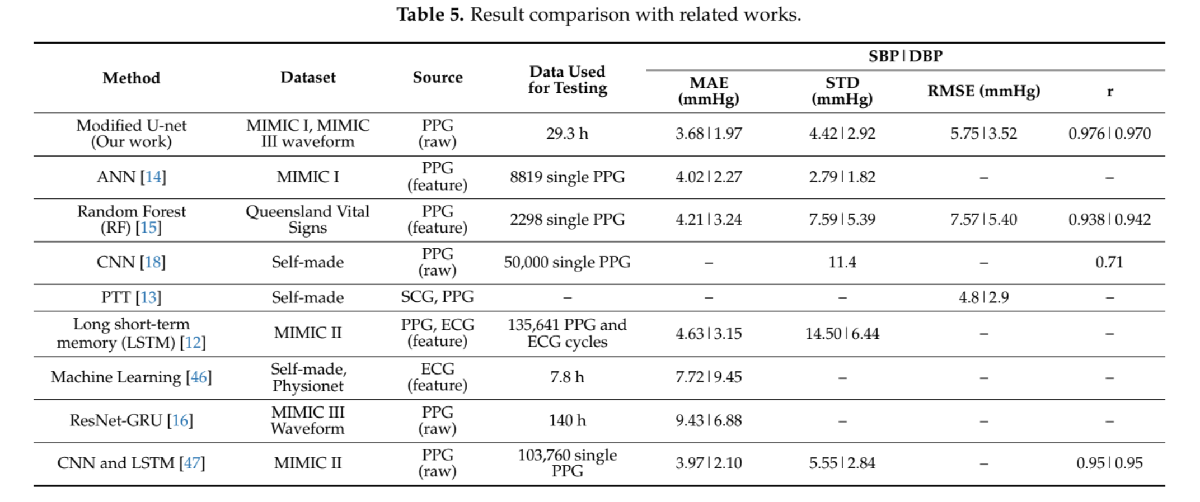

source: T. Athaya, S. Choi "An Estimation Method of Continuous Non-Invasive Arterial Blood Pressure Waveform Using Photoplethysmography: A U-Net Architecture-Based Approach" p. 13


nn4_512m =  fitrnet(trainInputT', trainOutputT', 'Standardize', true, 'LayerSizes',[512,512,512,512,512], 'Verbose',1,'VerboseFrequency',5)  


actualTrainMAP = trainOutputT'*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(dN6, trainInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = mean(abs(predictedTrainMAP-actualTrainMAP))
actualTestMAP = testOutputT'*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestMAP = predict(dN6, testInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = mean(abs(predictedTestMAP-actualTestMAP))

% load('dnn512_4.mat');
actualTestMAP = outputFeats'*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestMAP = predict(dN5, inputFeats)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedTestMAP-actualTestMAP');
mean(abs(testingError));
clf
scatter(actualTestMAP, testingError,'.')
xlabel("MAP (mmHg)")
ylabel("MAE (mmHg)")
grid on

#### **Extracting 10s of PPG, Last Sec of ABP Wave and BP Values**

addSubPaths();
opts = readOptionsStruct();
load('NormalisationFactors.mat')
fileList = dir(opts.segmented_file_dir+"*.txt");
numFiles = length(fileList);

inputFeats = zeros(200000,1250);
outputFeatsWave = zeros(200000,25);
outputFeatsBP = zeros(200000,3);

segLength = 10;
segOverlap = 0.2; %proportion that the interpolated points are allowed to overlap in the same segment 

numIndices = 0;
for idx=1:numFiles
    fprintf("\b\b\b\b\b\b%6i", idx);

    dataFile = fopen(opts.segmented_file_dir + fileList(idx).name);
    if(dataFile == -1)
        inputFeatures = [];
        fprintf("%s not found. Returning from function.", opts.segmented_file_dir+segmentName)
        continue; 
    end
    data = cell2mat(textscan( dataFile, ...
    '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
    fclose(dataFile);

    time = data(:,1);
    abp_wave = data(:,2);
    ppg_wave = data(:,3);

    numAvailableSegs = floor(time(end)/segLength*(1+segOverlap));
    
%     outputFeats=outputFeats;
    
    for i = 1:numAvailableSegs
        startInterp = 10*(i-1)*(1-segOverlap);
        if(i == 1); startInterp = 0; end;
        endInterp = startInterp +10;
        interp_pts_ppg = linspace(startInterp,endInterp,1250);
        interp_pts_abp = linspace(startInterp,endInterp,1250);

        interp_ppg = interp1(time, ppg_wave, interp_pts_ppg);
        interp_ppg = (interp_ppg-normFactors('PPGAmpMean'))./normFactors('PPGAmpScale');
        interp_abp = interp1(time, abp_wave, interp_pts_abp);
        interp_abp = (interp_abp-normFactors('ABPAmpMean'))./normFactors('ABPAmpScale');
        
        if(~isempty(find(isnan(interp_ppg))) && ~isempty(find(isnan(interp_abp)))); continue; end;
        inputFeats(numIndices+1, :) = interp_ppg;
        [sys, dias, meanSBP, meanDBP, MAP] = findABPPeaks(interp_abp,125,false,false);
        if(isempty(sys) || isempty(dias)); continue; end;
%         MAP = (mean(abp_wave((endInterp-4)*125:endInterp*125))-normFactors('ABPAmpMean'))./normFactors('ABPAmpScale');
        MAP = mean(interp_abp);
       numIndices = numIndices+1;
%         plot(interp_pts_abp, interp_abp); hold on; scatter(interp_pts_abp(sys), interp_abp(sys)); scatter(interp_pts_abp(dias), interp_abp(dias),'*');
        outputFeatsBP(numIndices, :) = [meanSBP, meanDBP, MAP];
%         interp_pts_abpwave = linspace(endInterp-1,endInterp,25);
%         outputFeatsWave(numIndices, :) = (interp1(time, abp_wave, interp_pts_abpwave)-normFactors('ABPAmpMean'))./normFactors('ABPAmpScale');
    end

end

  1818


inputFeats(numIndices:end, :) = [];
outputFeatsBP(numIndices:end, :)=[];
outputFeatsWave(numIndices:end, :)=[];


partition_variable = cvpartition(height(inputFeats), "Holdout",0.30);
trainingIndices = training(partition_variable);
trainInputT = inputFeats(trainingIndices,:);
trainOutputT = outputFeatsBP(trainingIndices,:);

nonTrainIndices = test(partition_variable);
nonTrainInputT = inputFeats(nonTrainIndices, :);
nonTrainOutputBP = outputFeatsBP(nonTrainIndices, :);
validation_partition = cvpartition(length(nonTrainInputT), "Holdout", 0.5);
testIndices = training(validation_partition);
testInputT = nonTrainInputT(testIndices,:);
testOutputT = nonTrainOutputBP(testIndices,:);
validIndices = test(validation_partition);
validInputT = nonTrainInputT(validIndices,:);
validOutputT = nonTrainOutputBP(validIndices,:);







**Playing With Deep Learning Models for Discrete Predictions**


% layers = [ ...
%     sequenceInputLayer(1250)
%     batchNormalizationLayer
%     fullyConnectedLayer(1024)
%     reluLayer
%     batchNormalizationLayer
%     fullyConnectedLayer(1024)
%     reluLayer
%     batchNormalizationLayer
%     fullyConnectedLayer(1024)
%     reluLayer
%     batchNormalizationLayer
%     fullyConnectedLayer(1024)
%     reluLayer
%     fullyConnectedLayer(1024)
%     reluLayer
%     batchNormalizationLayer
%     fullyConnectedLayer(2)
%     regressionLayer];
% 
% layers = [ ...
%     featureInputLayer(1250)
%     bilstmLayer(128, 'OutputMode', 'sequence')
%     batchNormalizationLayer
%     lstmLayer(128, 'OutputMode', 'sequence')
%     reluLayer
%     fullyConnectedLayer(512)
%     reluLayer
%     fullyConnectedLayer(1)
%     reluLayer];

% layers = [...
%     sequenceInputLayer(1250)
%     bilstmLayer(128, 'OutputMode', 'sequence')
%     batchNormalizationLayer
%     lstmLayer(128, 'OutputMode', 'sequence')
%     batchNormalizationLayer
%     lstmLayer(128, 'OutputMode', 'sequence')
%     batchNormalizationLayer
%     fullyConnectedLayer(1)
%     reluLayer
%     regressionLayer]

%    bilstmLayer(500)
%     batchNormalizationLayer

layers = [ ...
    sequenceInputLayer(1250)
    bilstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(3)
    regressionLayer];
options = trainingOptions('adam',...
    'ExecutionEnvironment', 'cpu',...
    'MaxEpochs',1000,...
    'L2Regularization', 0, ...
    'InitialLearnRate',5e-6,...
    'MiniBatchSize',128,...
    'ValidationData', {validInputT', validOutputT'}, ...
    'VerboseFrequency',1,...
    'ValidationFrequency', 1)
[net_lstm, info] = trainNetwork(trainInputT', trainOutputT', layers, options)


layers = [ ...
    sequenceInputLayer(1250)
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];
% fullyConnectedLayer(5000)
% reluLayer
% fullyConnectedLayer(2500)
% reluLayer

layers = [
    sequenceInputLayer(1250,"Name","input")
    convolution1dLayer(10,125,"Name","conv1d","Padding","same")
    reluLayer("Name","relu_1")
    batchNormalizationLayer
    dropoutLayer(0.2,"Name","drop")
    convolution1dLayer(5,256,"Name","conv1d_2","Padding","same")
    reluLayer("Name","relu_2")
    batchNormalizationLayer
    convolution1dLayer(3,128,"Name","conv1d_3","Padding","same")
    reluLayer("Name","relu_3")
    batchNormalizationLayer
    fullyConnectedLayer(1,"Name","fc")
    reluLayer("Name","relu_4")
    regressionLayer("Name","regressionoutput")];
layers = [
    sequenceInputLayer(1250,"Name","input")
    convolution1dLayer(10,125,"Name","conv1d","Padding","same")
    reluLayer("Name","relu_1")
    batchNormalizationLayer
    fullyConnectedLayer(512,"Name","fc")
    reluLayer("Name","relu_4")
    fullyConnectedLayer(512,"Name","fc")
    reluLayer("Name","relu_4")
    fullyConnectedLayer(1,"Name","fc")
    reluLayer("Name","relu_4")
    regressionLayer("Name","regressionoutput")];

options = trainingOptions('adam',...
    'MaxEpochs',250,...
    'ExecutionEnvironment', 'cpu',...
    'L2Regularization', 0, ...
    'InitialLearnRate', 5e-5,...
    'MiniBatchSize',height(trainInputT),...
    'VerboseFrequency',5, ...
    'ValidationFrequency', 5)
%'ValidationData', {validInputT(1:end,:)', validOutputT(1:end,1)'}, ...
[net_over_sbp, info] = trainNetwork(trainInputT(1:10e3,:)', trainOutputT(1:10e3,1)', layers, options)
[net_conv_sbp, info] = trainNetwork(trainInputT', trainOutputT(:,1)', layers, options)


gp_dbp = fitrgp(trainInputT(1:10e3, :), trainOutputT(1:10e3, 2),'Standardize',1)

individual_sbp_2L = fitrnet(trainInputT(1:end,:), trainOutputT(1:end,2), 'Standardize', true, 'LayerSizes',[512, 512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 500, 'Lambda', 0, 'ValidationData', {testInputT(:,:), testOutputT(:,1)}, 'StoreHistory',0);  


individual_sbp_4L = fitrnet(trainInputT(:,:), trainOutputT(:,1), 'Standardize', true, 'LayerSizes',[512,1024,512,512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 1000, 'Lambda', 5e-5, 'ValidationData', {testInputT(:,:), testOutputT(:,1)}, 'ValidationPatience', inf,...
    'OptimizeHyperparameters','none', 'HyperparameterOptimizationOptions', struct('UseParallel',true), 'StoreHistory',0)


individual_sbp_2L = fitrnet(trainInputT(:,:), trainOutputT(:,1), 'Standardize', true, 'LayerSizes',[1024,1024], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 1000, 'Lambda', 5e-5, 'ValidationData', {testInputT(:,:), testOutputT(:,1)}, 'ValidationPatience', inf, 'StoreHistory',0)

actualTestSBP = testOutputT(1:9e3,1)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestSBP = predict(net_over_sbp, testInputT(1:9e3,:)')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingErrorSBP = (predictedTestSBP-actualTestSBP');
mean(abs(testingErrorSBP))
sum(abs(testingErrorSBP)<10)/length(testingErrorSBP)
fitlm(actualTestSBP, predictedTestSBP)
scatter(actualTestSBP, predictedTestSBP, '.'); xlabel("Actual (mmHg)"); ylabel("Predicted (mmHg)"); grid on;

loss(gp_dbp, testInputT, testOutputT(:,2))            


actualTestDBP = testOutputT(1:5e3,2)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestDBP = predict(gam_dbp_comp, testInputT(1:5e3,:))*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingErrorDBP = (predictedTestDBP-actualTestDBP);
mean(abs(testingErrorDBP))
sum(abs(testingErrorDBP)<10)/length(testingErrorDBP)
% mean(( testOutputT(1:end,2) -  predict(tree_dbp,testInputT(1:end,:)) ).^2)
fitlm(actualTestDBP, predictedTestDBP)
scatter(actualTestDBP, predictedTestDBP, '.'); xlabel("Actual (mmHg)"); ylabel("Predicted (mmHg)"); grid on;


layers = [ ...
    featureInputLayer(10)
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(1)
    reluLayer
    regressionLayer];
options = trainingOptions('adam',...
    'ExecutionEnvironment', 'gpu',...
    'MaxEpochs',30,...
    'L2Regularization', 0, ...
    'InitialLearnRate', 1e-4,...
    'VerboseFrequency',5,...
    'ValidationFrequency', 5, ...
    'ValidationData', {validInput, validOutput(:,2)}, ...
    'MiniBatchSize',1024 )
[net_feat_dbp, info] = trainNetwork(trainInput, trainOutput(:,2), layers, options)


layers = [ ...
    featureInputLayer(250)
    fullyConnectedLayer(500)
    reluLayer
    fullyConnectedLayer(1000)
    reluLayer
    fullyConnectedLayer(1500)
    reluLayer
    fullyConnectedLayer(1000)
    reluLayer
    fullyConnectedLayer(500)
    reluLayer
    fullyConnectedLayer(3)
    reluLayer
    regressionLayer];

layers = [...
    imageInputLayer([1,250])
    convolution2dLayer([1,2], 125)
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([1,10],250)
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([1,10], 125)
    batchNormalizationLayer
    reluLayer
    globalAveragePooling2dLayer
    reluLayer
    fullyConnectedLayer(1)
    reluLayer
    regressionLayer
]
layers = [...
    imageInputLayer([1,250])
    convolution2dLayer([1,5], 250)
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer([1,2])
    reluLayer
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(1)
    reluLayer
    regressionLayer
]
numObs = height(trainInputT);
trainInputT_re = reshape(trainInputT(:,1001:end), [1, 250, 1, numObs]);
numValidations = height(validInputT);
validInputT_re = reshape(validInputT(:,1001:end), [1,250, 1, numValidations]);
options = trainingOptions('adam',...
    'ExecutionEnvironment', 'gpu',...
    'MaxEpochs',50,...
    'L2Regularization', 0, ...
    'InitialLearnRate', 2e-5,...
    'MiniBatchSize',256,...
    'VerboseFrequency',5,...
    'ValidationData', {validInputT_re, validOutputT(:,1)}, ...
    'ValidationFrequency', 50)
[conv_sbp, info] = trainNetwork(trainInputT_re, trainOutputT(:,1), layers, options)



layers = [ ...
    featureInputLayer(1250)
    bilstmLayer(256)
    reluLayer
    lstmLayer(256)
    reluLayer
    fullyConnectedLayer(256)
    reluLayer
    fullyConnectedLayer(3)
    reluLayer
    regressionLayer];

options = trainingOptions('adam',...
    'ExecutionEnvironment', 'gpu',...
    'MaxEpochs',30,...
    'L2Regularization', 0, ...
    'InitialLearnRate', 1e-4,...
    'VerboseFrequency',5,...
    'ValidationFrequency', 5)

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-06
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 0
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 5
                   MiniBatchSize: 1000
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: {[975×1250 double]  [975×3 double]}
             ValidationFrequency: 5
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
            ExecutionEnvironment: 'cpu'
                      WorkerLoad: []
          

        'ValidationData', {validInputT, validOutputT}, ...
    'MiniBatchSize',5000,...




  options = trainingOptions('adam',...
    'ExecutionEnvironment', 'gpu',...
    'MaxEpochs',30,...
    'L2Regularization', 0, ...
    'InitialLearnRate', 1e-4,...
    'VerboseFrequency',5,...
    'ValidationFrequency', 5, ...
    'ValidationData', {validInput, validOutput}, ...
    'MiniBatchSize',128 )
  [featNet_all, info] = trainNetwork(trainInput, trainOutput, layers, options)


[net_all, info] = trainNetwork(trainInputT, trainOutputT, net_all.Layers, options); save('TESTALLOVERNIGHT', 'net_map')


[net_all, info] = trainNetwork(trainInputT, trainOutputT, layers, options); save('TESTMAPOVERNIGHT', 'net_map')

[net_temp, info] = trainNetwork(trainInputT, trainOutputT, net_temp.Layers, options)

[net_sbp, info] = trainNetwork(trainInputT', trainOutputT(:,1)', net.Layers, options)

% 
% 
% nn4_512m =  fitrnet(trainInputT, trainOutputT(:,3), 'Standardize', true, 'LayerSizes',[512,512,512,512], 'Verbose',1,'VerboseFrequency',5)  
nn4_512s =  fitrnet(trainInputT(1:50e3,:), trainOutputT(1:50e3,1), 'Standardize', true, 'LayerSizes',[512,512,512,512], 'Verbose',1,'VerboseFrequency',5)  

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           5|    0.000173|    0.006165|    0.003739|    0.078033|
|================================================================|


nn4_512s =   RegressionNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 5
               LayerSizes: [512 512 512 512]
              Activations: 'relu'
    OutputLayerActivation: 'linear'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [7×7 table]


  Properties, Methods


individual_sbp_512_4 = fitrnet(trainInputT, trainOutputT(:,2), 'Standardize', true, 'LayerSizes',[512,512,512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 20e3, 'Lambda', 0)  

% 
% 
% nn5_512s =  fitrnet(trainInputT', trainOutputT(1,:)', 'Standardize', true,...
%     'LayerSizes',[512,512,512,512,512], 'Verbose',1,'VerboseFrequency',5,...
%     'IterationLimit',2e3, 'ValidationData', {validInputT', validOutputT(1,:)'})  
% % 
% % 
% nn3_1024s =  fitrnet(trainInputT, trainOutputT(:,1), 'Standardize', true, 'LayerSizes',[1024,1024,1024], 'Verbose',1,'VerboseFrequency',5)  



% n=1;
% actualTrainMAP = trainOutputT(n,:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
% predictedTrainMAP = predict(net1, trainInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
% trainingError = (predictedTrainMAP(:,n)-actualTrainMAP');
% mean(abs(trainingError))
% sum(abs(trainingError)<10)/length(trainingError)
load('netRetrainedOnAll3.mat')

    predictedTestBP = predict(featNet_all testInputT)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    n=1

n = 1

    actualTestSBP = testOutputT(:,n)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingErrorSBP = (predictedTestBP(:,n)-actualTestSBP);
    mean(abs(testingErrorSBP))

ans = single
5.1171

    sum(abs(testingErrorSBP)<10)/length(testingErrorSBP)

ans = 0.8504

    fitlm(actualTestSBP, predictedTestBP(:,n))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     18.493       1.7461    10.591    6.4653e-25
    x1             0.85719     0.011998    71.443             0


Number of observations: 1003, Error degrees of freedom: 1001
Root Mean Squared Error: 6.73
R-squared: 0.836,  Adjusted R-Squared: 0.836
F-statistic vs. constant model: 5.1e+03, p-value = 0

    
    n=2

n = 2

    actualTestDBP = testOutputT(:,n)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingErrorDBP = (predictedTestBP(:,n)-actualTestDBP);
    mean(abs(testingErrorDBP))
    sum(abs(testingErrorDBP)<10)/length(testingErrorDBP)
    fitlm(actualTestDBP, predictedTestBP(:,n))

ans = single
3.5831

ans = 0.9601

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat     pValue
                   ________    ________    ______    ______

    (Intercept)     30.144       1.2624    23.878      0   
    x1             0.60443     0.017019    35.515      0   


Number of observations: 1003, Error degrees of freedom: 1001
Root Mean Squared Error: 3.74
R-squared: 0.558,  Adjusted R-Squared: 0.557
F-statistic vs. constant model: 1.26e+03, p-value = 0

    
    n=3

n = 3

    actualTestMAP = testOutputT(:,n)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
    testingErrorMAP = (predictedTestBP(:,n)-actualTestMAP);
    mean(abs(testingErrorMAP))
    sum(abs(testingErrorMAP)<10)/length(testingErrorMAP)
    fitlm(actualTestMAP, predictedTestBP(:,n))

ans = single
4.4598

ans = 0.9143

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     18.805       1.8184    10.341    6.9329e-24
    x1             0.82022     0.018525    44.277             0


Number of observations: 1003, Error degrees of freedom: 1001
Root Mean Squared Error: 5.49
R-squared: 0.662,  Adjusted R-Squared: 0.662
F-statistic vs. constant model: 1.96e+03, p-value = 0



actualTestSBP = testOutputT(:,1)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestSBP = predict(net_over_sbp, testInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingErrorSBP = (predictedTestSBP-actualTestSBP');
mean(abs(testingErrorSBP))
sum(abs(testingErrorSBP)<10)/length(testingErrorSBP)
fitlm(actualTestSBP, predictedTestSBP)


actualTestDBP = testOutputT(:,2)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestDBP = predict(fitr_dbp, testInputT)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingErrorDBP = (predictedTestDBP-actualTestDBP);
mean(abs(testingErrorDBP))
sum(abs(testingErrorDBP)<10)/length(testingErrorDBP)
fitlm(actualTestDBP, predictedTestDBP)
% 
% clf
% scatter(actualTestMAP, testingError,'.')
% xlabel("MAP (mmHg)")
% ylabel("MAE (mmHg)")
% grid on

% nn

actualTestSBP = testOutputT(:,1)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');

predictedTestVals = predict(net1, testInputT)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean')

predictedTestVals = 977×3 single matrix
  141.6868   73.1291   96.9831
  143.6987   73.1215   97.3457
  142.0318   71.5986   96.3838
  142.8706   72.3194   96.9476
  141.9903   71.2243   95.6903
  141.7363   73.0146   96.6298
  143.7596   72.9352   97.2908
  142.4828   72.4470   96.6940
  142.1115   72.6089   96.7723
  142.9499   72.4189   96.9142



sbp_est = 3.*predictedTestVals(:,3)-2.*predictedTestVals(:,2)

sbp_est = 977×1 single column vector
  144.6909
  145.7943
  145.9541
  146.2040
  144.6224
  143.8602
  146.0021
  145.1879
  145.0991
  145.9046



mean(abs(sbp_est - actualTestSBP))

ans = single
10.0798

sum(abs(sbp_est-actualTestSBP)<10)/length(sbp_est)

ans = 0.5865

#### Simple ResNet


lgraph = layerGraph();
tempLayers = sequenceInputLayer(1250,"Name","sequence");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    convolution1dLayer(3,1250,"Name","conv1d_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    convolution1dLayer(3,1250,"Name","conv1d_2","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","addition_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    convolution1dLayer(3,1250,"Name","conv1d_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")
    convolution1dLayer(3,1250,"Name","conv1d_4","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_2")
    fullyConnectedLayer(1,"Name","fc")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

lgraph = connectLayers(lgraph,"sequence","batchnorm_1");
lgraph = connectLayers(lgraph,"sequence","addition_1/in2");
lgraph = connectLayers(lgraph,"conv1d_2","addition_1/in1");
lgraph = connectLayers(lgraph,"addition_1","batchnorm_3");
lgraph = connectLayers(lgraph,"addition_1","addition_2/in2");
lgraph = connectLayers(lgraph,"conv1d_4","addition_2/in1");
plot(lgraph);

options = trainingOptions('adam',...
    'initialLearnRate',0.00001,...
    'miniBatchSize', 1024,...
    'ExecutionEnvironment', 'cpu',...
    'ValidationData', {testInputT', testOutputT(:,1)'}, ...
    'MaxEpochs', 150,...
    'L2Regularization', 1e-4, ...
    'ValidationFrequency', 10)

[net1, info] = trainNetwork(trainInputT', trainOutputT(:,1)', lgraph, options)


options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 150
                   MiniBatchSize: 32
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: {[1250×975 double]  [0.0362 0.1943 0.2746 -0.1254 -0.0922 0.0136 -0.0297 -0.0514 -0.0768 -0.1014 -0.1183 -0.1184 -0.1190 -0.1538 -0.0419 0.0845 0.0824 0.0863 -0.1585 -0.1834 -0.1626 -0.1406 -0.1269 -0.0624 -0.0280 … ]}
             ValidationFrequency: 10
          

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         1.31 |       131.88 |       0.8539 |    8695.6572 |          0.0010 |
|      10 |          10 |       00:00:33 |        42.67 |        45.59 |     910.2108 |    1039.0339 |          0.0010 |
|      20 |          20 |       00:01:05 |        18.81 |        17.83 |     176.9078 |     158.9161 |          0.0010 |
|      30 |          30 |       00:01:42 |        11.72 |         9.51 |      68.6473 |      45.2534 |          0.0010 |
|      40 |          40 |       

net1 =   DAGNetwork with properties:

         Layers: [17×1 nnet.cnn.layer.Layer]
    Connections: [18×2 table]
     InputNames: {'sequence'}
    OutputNames: {'regressionoutput'}


info = struct with fields:
              TrainingLoss: [0.8539 8.6552e+03 570.0748 2.6104e+03 2.9703e+03 1.6150e+03 491.7362 146.1958 485.8831 910.2108 973.7999 695.7820 351.6597 187.5314 207.0840 267.8114 289.6032 259.8833 211.1339 176.9078 162.7363 151.1103 123.7740 91.6277 … ]
              TrainingRMSE: [1.3069 131.5692 33.7661 72.2555 77.0753 56.8330 31.3604 17.0995 31.1732 42.6664 44.1316 37.3037 26.5202 19.3665 20.3511 23.1435 24.0667 22.7984 20.5492 18.8100 18.0409 17.3845 15.7337 13.5372 11.4873 10.9772 12.1391 … ]
            ValidationLoss: [8.6957e+03 NaN NaN NaN NaN NaN NaN NaN NaN 1.0390e+03 NaN NaN NaN NaN NaN NaN NaN NaN NaN 158.9161 NaN NaN NaN NaN NaN NaN NaN NaN NaN 45.2534 NaN NaN NaN NaN NaN NaN NaN NaN NaN 6.1471 NaN NaN NaN NaN NaN NaN NaN NaN NaN … ]
            ValidationRMSE: [131.8761 NaN NaN NaN NaN NaN NaN NaN NaN 45.5858 NaN NaN NaN NaN NaN NaN NaN NaN NaN 17.8278 NaN NaN NaN NaN NaN NaN NaN NaN NaN 9.5135 NaN NaN NaN NaN NaN NaN NaN NaN NaN 3.5063 NaN NaN

ans = single
19.9131

ans = 0.4066

ans = single
22.9724

ans = 0.3651

ans = 1×5 cell array
    {512×1250 double}    {512×512 double}    {512×512 double}    {512×512 double}    {[-0.1578 -0.1157 0.0467 0.2167 -0.0953 0.0940 0.1312 -0.2648 -0.1888 -0.2234 -0.0673 0.1480 -0.2268 -0.1223 -0.0412 -0.0974 -0.2337 -0.1926 -0.1140 -0.0655 -0.2110 -0.0029 -0.1377 0.0510 0.0898 0.0343 0.1373 0.1163 0.0115 -0.0943 -0.0707 0.0506 0.0405 0.0371 0.1119 0.0863 -0.0404 0.1634 -0.1753 -0.0691 -0.1358 -0.1116 -0.1573 0.0757 0.0643 0.0826 0.1067 -0.0162 -0.1840 -0.1029 -0.0889 0.0496 -0.0577 -0.1976 0.0685 0.0351 0.0994 -0.0455 -0.1705 0.0974 -0.2155 -0.0975 -0.1089 0.1704 -0.1031 -0.1907 -0.0513 0.0128 0.0141 0.1730 -0.1299 0.0619 0.0125 0.0315 0.1961 -0.1424 0.0821 -0.2331 0.2008 0.0125 -0.1195 -0.1168 0.0884 0.0544 -0.0990 -0.1869 0.1261 0.0801 -0.1114 0.1900 0.0451 -0.1686 0.0598 0.1040 0.1038 -0.0647 -0.0335 -0.0348 -0.0317 0.0715 0.1339 -0.0735 0.2308 -0.1369 0.1501 -0.0616 0.0122 -0.0885 0.1603 0.1336 -0.0454 -0.2067 0.1750 -0.1355 -0.1487 0.0246 0.1180 0.1755 0.075

actualTrainMAP = trainOutputT(1,:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTrainMAP = predict(net1, trainInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
trainingError = (predictedTrainMAP'-actualTrainMAP);
mean(abs(trainingError))
sum(abs(trainingError)<10)/length(trainingError)

actualTestMAP = testOutputT(1,:)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestMAP = predict(net1, testInputT')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingError = (predictedTestMAP'-actualTestMAP);
mean(abs(testingError))
sum(abs(testingError)<10)/length(testingError)

##  Full ResNet

Not implemented because all layers need to be replaced by 1D Layers

lgraph = resnet18('Weights','none');

tempLayers = [regressionLayer("Name","regression_output")];
lgraph = replaceLayer(lgraph, 'ClassificationLayer_predictions', tempLayers);
tempLayers = [reluLayer("Name","relu_output")];
lgraph = replaceLayer(lgraph, 'ClassificationLayer_predictions', tempLayers);
% lgraph = removeLayers(lgraph, 'prob');

lgraph = connectLayers(lgraph, 'fc1000', 'relu_output')
lgraph = connectLayers(lgraph, 'relu_output', 'regression_output')
lgraph.Layers




% options = trainingOptions('adam',...
%     'initialLearnRate',0.001,...
%     'miniBatchSize', 32,...
%     'ExecutionEnvironment', 'gpu',...
%     'ValidationData', {testInputT', testOutputT(:,1)'}, ...
%     'MaxEpochs', 150,...
%     'L2Regularization', 1e-4, ...
%     'ValidationFrequency', 10)
% [net1, info] = trainNetwork(trainInputT', trainOutputT(:,1)', lgraph, options)

%    After more data acquistion
inputFeatsExtra = inputFeats(1:numIndices,:);
outputFeatsBPExtra = outputFeatsBP(1:numIndices,:);
outputFeatsWaveExtra = outputFeatsWave(1:numIndices,:);
% inputFeatsExtra = inputFeats;
% outputFeatsBPExtra = outputFeatsBP;
% outputFeatsWaveExtra = outputFeatsWave;
% trainingIndicesExtra = trainingIndices+31965;
% testIndicesExtra = testIndices+31965;
% validIndicesExtra = validIndices+31965;
% trainInputTExtra = trainInputT;
% trainOutputTExtra = trainOutputT;
% testInputTExtra = testInputT;
% testOutputTExtra = testOutputT;
% validInputTExtra = validInputT;
% validOutputTExtra = validOutputT;
% load('...')
inputFeats = [inputFeats; inputFeatsExtra];
outputFeatsBP = [outputFeatsBP; outputFeatsBPExtra];
outputFeatsWave = [outputFeatsWave; outputFeatsWaveExtra];
trainInputT = [trainInputT; trainInputTExtra];
trainOutputT = [trainOutputT; trainOutputTExtra];
testInputT = [testInputT; testInputTExtra];
testOutputT = [testOutputT; testOutputTExtra];
validInputT = [validInputT; validInputTExtra];
validOutputT = [validOutputT; validOutputTExtra];

save('timeObservationsWithLastSecond.mat', 'inputFeats', 'outputFeatsBP', 'outputFeatsWave', 'trainInputT', 'trainOutputT', 'testInputT', 'testOutputT',...
    'validInputT', 'validOutputT', 'trainingIndices', 'testIndices', 'validIndices', 'normFactors')

tHist = [0.0723, 0.0657, 0.0638, 0.0633, 0.0621, 0.0619, 0.0616, 0.0610, 0.0607, 0.0605, 0.0601, 0.0598, 0.0599, 0.0596, 0.0593, 0.0590, 0.0589, 0.0589, 0.0587, 0.0584, 0.0584, 0.0583, 0.0580, 0.0579, 0.0580, 0.0577, 0.0574, 0.0573, 0.0572, 0.0572, 0.0570, 0.0568, 0.0569, 0.0567, 0.0564, 0.0565, 0.0564, 0.0562, 0.0560, 0.0558, 0.0558, 0.0558, 0.0556, 0.0555, 0.0555, 0.0553, 0.0551, 0.0552, 0.0550, 0.0548, 0.0547, 0.0545, 0.0546, 0.0545, 0.0543, 0.0543, 0.0543, 0.0540, 0.0538, 0.0540, 0.0537, 0.0536, 0.0534, 0.0533, 0.0534, 0.0532, 0.0530, 0.0531, 0.0530, 0.0527, 0.0526, 0.0528, 0.0525, 0.0524, 0.0522, 0.0522, 0.0523, 0.0520, 0.0519, 0.0519, 0.0518, 0.0515, 0.0516, 0.0516, 0.0514, 0.0512, 0.0511, 0.0510, 0.0511, 0.0509, 0.0508, 0.0508, 0.0506, 0.0504, 0.0505, 0.0504, 0.0503, 0.0501, 0.0499, 0.0500, 0.0499, 0.0497, 0.0497, 0.0497, 0.0495, 0.0493, 0.0495, 0.0493, 0.0491, 0.0490, 0.0489, 0.0490, 0.0488, 0.0487, 0.0487, 0.0487, 0.0484, 0.0483, 0.0485, 0.0481, 0.0481, 0.0479, 0.0478, 0.0480, 0.0478, 0.0476, 0.0477, 0.0476, 0.0473, 0.0473, 0.0474, 0.0472, 0.0471, 0.0469, 0.0469, 0.0470, 0.0468, 0.0466, 0.0467, 0.0465, 0.0464, 0.0464, 0.0464, 0.0463, 0.0461, 0.0460, 0.0460, 0.0460, 0.0458, 0.0457, 0.0458, 0.0456, 0.0454, 0.0456, 0.0455, 0.0453, 0.0452, 0.0451, 0.0451, 0.0450, 0.0449, 0.0449, 0.0449, 0.0447, 0.0446, 0.0448, 0.0445, 0.0444, 0.0443, 0.0442, 0.0444, 0.0442, 0.0441, 0.0441, 0.0441, 0.0439, 0.0438, 0.0440, 0.0437, 0.0437, 0.0435, 0.0435, 0.0437, 0.0434, 0.0433, 0.0434, 0.0433, 0.0431, 0.0431, 0.0433, 0.0430, 0.0430, 0.0428, 0.0429, 0.0430, 0.0428, 0.0427, 0.0427, 0.0426, 0.0425, 0.0425, 0.0426, 0.0425, 0.0424, 0.0422, 0.0423, 0.0423, 0.0422, 0.0421, 0.0422, 0.0420, 0.0419, 0.0421, 0.0420, 0.0419, 0.0418, 0.0417, 0.0418, 0.0417, 0.0416, 0.0417, 0.0417, 0.0415, 0.0414, 0.0416, 0.0414, 0.0414, 0.0413, 0.0412, 0.0414, 0.0412, 0.0412, 0.0412, 0.0412, 0.0410, 0.0410, 0.0412, 0.0410, 0.0410, 0.0409, 0.0408, 0.0410, 0.0408, 0.0408, 0.0409, 0.0408, 0.0406, 0.0406, 0.0408, 0.0406, 0.0406, 0.0405, 0.0405, 0.0407, 0.0405, 0.0404, 0.0405, 0.0404, 0.0403, 0.0404, 0.0405, 0.0404, 0.0403, 0.0402, 0.0402, 0.0403, 0.0402, 0.0402, 0.0402, 0.0401, 0.0400, 0.0402, 0.0401, 0.0401, 0.0400, 0.0399, 0.0400, 0.0399, 0.0399, 0.0399, 0.0400, 0.0398, 0.0398, 0.0400, 0.0398, 0.0398, 0.0397, 0.0397, 0.0399, 0.0397, 0.0396, 0.0397, 0.0397, 0.0396, 0.0395, 0.0398, 0.0395, 0.0395, 0.0395, 0.0395, 0.0397, 0.0395, 0.0394, 0.0395, 0.0394, 0.0393, 0.0394, 0.0395, 0.0394, 0.0393, 0.0392, 0.0393, 0.0394, 0.0393, 0.0392, 0.0393, 0.0392, 0.0391, 0.0392, 0.0393, 0.0392, 0.0392, 0.0391, 0.0391, 0.0392, 0.0391, 0.0391, 0.0391, 0.0390, 0.0390, 0.0391, 0.0391, 0.0390, 0.0390, 0.0389, 0.0390, 0.0389, 0.0389, 0.0389, 0.0390, 0.0388, 0.0388, 0.0390, 0.0388, 0.0388, 0.0388, 0.0387, 0.0389, 0.0388, 0.0387, 0.0388, 0.0388, 0.0387, 0.0386, 0.0389, 0.0386, 0.0387, 0.0386, 0.0386, 0.0388, 0.0386, 0.0386, 0.0387, 0.0386, 0.0385, 0.0385, 0.0387, 0.0385, 0.0385, 0.0384, 0.0385, 0.0386, 0.0385, 0.0384, 0.0385, 0.0384, 0.0383, 0.0384, 0.0385, 0.0384, 0.0384, 0.0383, 0.0384, 0.0384, 0.0383, 0.0383, 0.0384, 0.0383, 0.0382, 0.0384, 0.0384, 0.0383, 0.0382, 0.0382, 0.0383, 0.0382, 0.0382, 0.0382, 0.0382, 0.0381, 0.0381, 0.0383, 0.0381, 0.0381, 0.0380, 0.0380, 0.0382, 0.0380, 0.0380, 0.0381, 0.0381, 0.0380, 0.0379, 0.0382, 0.0379, 0.0380, 0.0379, 0.0379, 0.0381, 0.0379, 0.0379, 0.0380, 0.0379, 0.0378, 0.0378, 0.0380, 0.0379, 0.0378, 0.0377, 0.0378, 0.0379, 0.0378, 0.0377, 0.0378, 0.0377, 0.0377, 0.0378, 0.0379, 0.0378, 0.0377, 0.0376, 0.0377, 0.0377, 0.0376, 0.0377, 0.0377, 0.0376, 0.0376, 0.0377, 0.0377, 0.0376, 0.0376, 0.0375, 0.0376, 0.0376, 0.0375, 0.0376, 0.0376, 0.0375, 0.0374, 0.0376, 0.0375, 0.0374, 0.0374, 0.0374, 0.0376, 0.0374, 0.0374, 0.0375, 0.0375, 0.0373, 0.0373, 0.0375, 0.0373, 0.0373, 0.0373, 0.0373, 0.0375, 0.0373, 0.0373, 0.0374, 0.0373, 0.0372, 0.0372, 0.0374, 0.0372, 0.0372, 0.0371, 0.0372, 0.0373, 0.0372, 0.0371, 0.0372, 0.0371, 0.0371, 0.0371, 0.0373, 0.0372, 0.0371, 0.0370, 0.0371, 0.0371, 0.0370, 0.0371, 0.0371, 0.0370, 0.0370, 0.0371, 0.0371, 0.0370, 0.0370, 0.0369, 0.0370, 0.0369, 0.0369, 0.0370, 0.0370, 0.0369, 0.0368, 0.0370, 0.0369, 0.0368, 0.0368, 0.0368, 0.0370, 0.0368, 0.0368, 0.0369, 0.0369, 0.0367, 0.0367, 0.0369, 0.0367, 0.0367, 0.0367, 0.0367, 0.0369, 0.0367, 0.0367, 0.0368, 0.0367, 0.0366, 0.0366, 0.0368, 0.0366, 0.0366, 0.0365, 0.0366, 0.0367, 0.0366, 0.0365, 0.0366, 0.0365, 0.0365, 0.0366, 0.0367, 0.0366, 0.0365, 0.0364, 0.0365, 0.0365, 0.0364, 0.0365, 0.0365, 0.0364, 0.0364, 0.0365, 0.0365, 0.0364, 0.0364, 0.0363, 0.0364, 0.0364, 0.0363, 0.0364, 0.0364, 0.0363, 0.0363, 0.0364, 0.0363, 0.0362, 0.0362, 0.0362, 0.0364, 0.0362, 0.0362, 0.0363, 0.0363, 0.0361, 0.0361, 0.0363, 0.0361, 0.0362, 0.0361, 0.0361, 0.0363, 0.0361, 0.0361, 0.0362, 0.0361, 0.0360, 0.0360, 0.0362, 0.0361, 0.0360, 0.0360, 0.0360, 0.0361, 0.0360, 0.0360, 0.0360, 0.0359, 0.0359, 0.0360, 0.0361, 0.0360, 0.0359, 0.0358, 0.0359, 0.0359, 0.0359, 0.0359, 0.0359, 0.0358, 0.0358, 0.0359, 0.0359, 0.0358, 0.0358, 0.0358, 0.0358, 0.0358, 0.0357, 0.0358, 0.0358, 0.0357, 0.0357, 0.0358, 0.0357, 0.0357, 0.0356, 0.0356, 0.0358, 0.0356, 0.0356, 0.0357, 0.0357, 0.0356, 0.0355, 0.0358, 0.0355, 0.0356, 0.0355, 0.0355, 0.0357, 0.0355, 0.0355, 0.0356, 0.0355, 0.0354, 0.0354, 0.0356, 0.0355, 0.0354, 0.0354, 0.0354, 0.0355, 0.0354, 0.0354, 0.0354, 0.0353, 0.0353, 0.0354, 0.0355, 0.0354, 0.0353, 0.0353, 0.0353, 0.0353, 0.0353, 0.0353, 0.0353, 0.0352, 0.0352, 0.0353, 0.0353, 0.0352, 0.0352, 0.0352, 0.0352, 0.0352, 0.0351, 0.0352, 0.0352, 0.0351, 0.0351, 0.0352, 0.0351, 0.0351, 0.0351, 0.0350, 0.0352, 0.0351, 0.0350, 0.0351, 0.0351, 0.0350, 0.0349, 0.0352, 0.0349, 0.0350, 0.0349, 0.0349, 0.0351, 0.0349, 0.0349, 0.0350, 0.0349, 0.0348, 0.0348, 0.0350, 0.0349, 0.0348, 0.0348, 0.0348, 0.0349, 0.0348, 0.0348, 0.0348, 0.0347, 0.0347, 0.0348, 0.0349, 0.0348, 0.0347, 0.0347, 0.0347, 0.0347, 0.0347, 0.0347, 0.0347, 0.0346, 0.0346, 0.0347, 0.0347, 0.0346, 0.0346, 0.0346, 0.0346, 0.0346, 0.0345, 0.0346, 0.0346, 0.0345, 0.0345, 0.0346, 0.0345, 0.0344, 0.0344, 0.0344, 0.0346, 0.0344, 0.0344, 0.0345, 0.0345, 0.0343, 0.0343, 0.0345, 0.0343, 0.0343, 0.0343, 0.0343, 0.0345, 0.0343, 0.0343, 0.0344, 0.0343, 0.0342, 0.0342, 0.0344, 0.0343, 0.0342, 0.0342, 0.0342, 0.0343, 0.0342, 0.0341, 0.0342, 0.0341, 0.0341, 0.0341, 0.0343, 0.0342, 0.0341, 0.0340, 0.0341, 0.0341, 0.0340, 0.0340, 0.0341, 0.0340, 0.0340, 0.0341, 0.0341, 0.0340, 0.0340, 0.0339, 0.0340, 0.0340, 0.0339, 0.0339, 0.0340, 0.0339, 0.0338, 0.0340, 0.0339, 0.0338, 0.0338, 0.0338, 0.0340, 0.0338, 0.0338, 0.0338, 0.0338, 0.0337, 0.0337, 0.0339, 0.0337, 0.0337, 0.0337, 0.0337, 0.0339, 0.0337, 0.0337, 0.0337, 0.0336, 0.0336, 0.0336, 0.0338, 0.0336, 0.0336, 0.0335, 0.0336, 0.0337, 0.0336, 0.0335, 0.0336, 0.0335, 0.0335, 0.0335, 0.0337, 0.0336, 0.0335, 0.0334, 0.0335, 0.0335, 0.0334, 0.0334, 0.0335, 0.0334, 0.0333, 0.0334, 0.0335, 0.0334, 0.0333, 0.0333, 0.0334, 0.0333, 0.0333, 0.0333, 0.0333, 0.0332, 0.0332, 0.0334, 0.0333, 0.0332, 0.0332, 0.0332, 0.0334, 0.0332, 0.0332, 0.0332, 0.0332, 0.0331, 0.0331, 0.0333, 0.0331, 0.0331, 0.0331, 0.0330, 0.0332, 0.0331, 0.0330, 0.0331, 0.0330, 0.0330, 0.0330, 0.0332, 0.0330, 0.0330, 0.0329, 0.0329, 0.0331, 0.0330, 0.0329, 0.0330, 0.0329, 0.0329, 0.0329, 0.0331, 0.0330, 0.0329, 0.0328, 0.0328, 0.0329, 0.0328, 0.0328, 0.0329, 0.0328, 0.0327, 0.0328, 0.0329, 0.0328, 0.0327, 0.0327, 0.0328, 0.0327, 0.0327, 0.0327, 0.0327, 0.0326, 0.0326, 0.0328, 0.0327, 0.0326, 0.0326, 0.0326, 0.0328, 0.0326, 0.0326, 0.0326, 0.0326, 0.0325, 0.0325, 0.0327, 0.0325, 0.0325, 0.0325, 0.0325, 0.0326, 0.0325, 0.0324, 0.0325, 0.0324, 0.0324, 0.0324, 0.0326, 0.0324, 0.0324, 0.0323, 0.0323, 0.0325, 0.0324, 0.0323, 0.0324, 0.0323, 0.0323, 0.0323, 0.0325, 0.0324, 0.0323, 0.0322, 0.0323, 0.0323, 0.0322, 0.0322, 0.0323, 0.0322, 0.0322, 0.0323, 0.0323, 0.0322, 0.0322, 0.0321, 0.0322, 0.0321, 0.0321, 0.0321, 0.0321, 0.0321, 0.0320, 0.0322, 0.0321, 0.0320, 0.0320, 0.0320, 0.0322, 0.0320, 0.0320, 0.0320, 0.0320, 0.0319, 0.0319, 0.0321, 0.0319, 0.0319, 0.0319, 0.0319, 0.0321, 0.0319, 0.0319, 0.0320, 0.0319, 0.0318, 0.0318, 0.0320, 0.0319, 0.0318, 0.0318, 0.0318, 0.0319, 0.0318, 0.0318, 0.0318, 0.0317, 0.0317, 0.0318, 0.0319, 0.0318, 0.0317, 0.0317, 0.0317, 0.0317, 0.0317, 0.0317, 0.0317, 0.0316, 0.0316, 0.0317, 0.0318, 0.0316, 0.0316, 0.0316, 0.0317, 0.0316, 0.0316, 0.0316, 0.0316, 0.0315, 0.0315, 0.0316, 0.0315, 0.0315, 0.0315, 0.0315, 0.0316, 0.0315, 0.0314, 0.0315, 0.0315, 0.0314, 0.0314, 0.0316, 0.0314, 0.0314, 0.0314, 0.0313, 0.0315, 0.0314, 0.0313, 0.0314, 0.0313, 0.0313, 0.0313, 0.0315, 0.0313, 0.0313, 0.0312, 0.0313, 0.0314, 0.0313, 0.0312, 0.0313, 0.0312, 0.0312, 0.0312, 0.0314, 0.0313, 0.0312, 0.0312, 0.0312, 0.0312, 0.0311, 0.0311, 0.0312, 0.0311, 0.0311, 0.0312, 0.0312, 0.0311, 0.0311, 0.0311, 0.0311, 0.0311, 0.0310, 0.0311, 0.0311, 0.0310, 0.0310, 0.0311, 0.0310, 0.0310, 0.0310, 0.0310, 0.0311, 0.0310, 0.0309, 0.0310, 0.0310, 0.0309, 0.0309, 0.0311, 0.0309, 0.0309, 0.0309, 0.0308, 0.0311, 0.0309, 0.0308, 0.0309, 0.0308, 0.0308, 0.0308, 0.0310, 0.0309, 0.0308, 0.0308, 0.0308, 0.0309, 0.0308, 0.0307, 0.0308, 0.0307, 0.0307, 0.0307, 0.0309, 0.0308, 0.0307, 0.0307, 0.0307, 0.0307, 0.0307, 0.0307, 0.0307, 0.0306, 0.0306, 0.0307, 0.0308, 0.0306, 0.0306, 0.0306, 0.0307, 0.0306, 0.0306, 0.0306, 0.0306, 0.0305, 0.0305, 0.0306, 0.0306, 0.0305, 0.0305, 0.0305, 0.0307, 0.0305, 0.0305, 0.0305, 0.0305, 0.0304, 0.0304, 0.0306, 0.0304, 0.0304, 0.0304, 0.0304, 0.0306, 0.0304, 0.0304, 0.0305, 0.0304, 0.0303, 0.0303, 0.0306, 0.0304, 0.0303, 0.0303, 0.0303, 0.0305, 0.0303, 0.0303, 0.0303, 0.0303, 0.0302, 0.0303, 0.0305, 0.0303, 0.0303, 0.0302, 0.0302, 0.0303, 0.0302, 0.0302, 0.0303, 0.0302, 0.0302, 0.0302, 0.0303, 0.0302, 0.0302, 0.0302, 0.0302, 0.0302, 0.0301, 0.0302, 0.0302, 0.0301, 0.0301, 0.0302, 0.0301, 0.0301, 0.0301, 0.0301, 0.0302, 0.0301, 0.0300, 0.0301, 0.0301, 0.0300, 0.0300, 0.0302, 0.0300, 0.0300, 0.0300, 0.0300, 0.0302, 0.0300, 0.0300, 0.0300, 0.0299, 0.0299, 0.0299, 0.0301, 0.0300, 0.0299, 0.0299, 0.0299, 0.0300, 0.0299, 0.0299, 0.0299, 0.0298, 0.0298, 0.0299, 0.0300, 0.0299, 0.0299, 0.0298, 0.0298, 0.0299, 0.0298, 0.0298, 0.0298, 0.0298, 0.0298, 0.0298, 0.0299, 0.0298, 0.0298, 0.0298, 0.0298, 0.0298, 0.0297, 0.0297, 0.0298, 0.0297, 0.0297, 0.0298, 0.0297, 0.0296, 0.0297, 0.0297, 0.0298, 0.0297, 0.0296, 0.0297, 0.0297, 0.0296, 0.0296, 0.0298, 0.0296, 0.0296, 0.0296, 0.0296, 0.0298, 0.0296, 0.0296, 0.0296, 0.0295, 0.0295, 0.0295, 0.0298, 0.0296, 0.0295, 0.0295, 0.0295, 0.0296, 0.0295, 0.0295, 0.0295, 0.0295, 0.0294, 0.0295, 0.0297, 0.0295, 0.0295, 0.0294, 0.0294, 0.0295, 0.0294, 0.0294, 0.0295, 0.0294, 0.0294, 0.0294, 0.0295, 0.0294, 0.0294, 0.0294, 0.0294, 0.0294, 0.0293, 0.0294, 0.0294, 0.0293, 0.0293, 0.0294, 0.0294, 0.0293, 0.0293, 0.0293, 0.0295, 0.0293, 0.0293, 0.0293, 0.0293, 0.0292, 0.0292, 0.0294, 0.0292, 0.0292, 0.0292, 0.0292, 0.0294, 0.0292, 0.0292, 0.0293, 0.0292, 0.0291, 0.0291, 0.0294, 0.0292, 0.0292, 0.0291, 0.0291, 0.0293, 0.0292, 0.0291, 0.0292, 0.0291, 0.0291, 0.0291, 0.0293, 0.0292, 0.0291, 0.0291, 0.0291, 0.0291, 0.0291, 0.0291, 0.0291, 0.0290, 0.0290, 0.0291, 0.0292, 0.0290, 0.0290, 0.0290, 0.0291, 0.0290, 0.0290, 0.0290, 0.0290, 0.0290, 0.0289, 0.0291, 0.0290, 0.0289, 0.0290, 0.0289, 0.0291, 0.0290, 0.0289, 0.0290, 0.0289, 0.0289, 0.0289, 0.0291, 0.0289, 0.0289, 0.0289, 0.0288, 0.0291, 0.0289, 0.0288, 0.0289, 0.0288, 0.0288, 0.0288, 0.0290, 0.0289, 0.0288, 0.0288, 0.0288, 0.0289, 0.0288, 0.0288, 0.0288, 0.0287, 0.0287, 0.0288, 0.0290, 0.0288, 0.0288, 0.0287, 0.0287, 0.0288, 0.0287, 0.0287, 0.0288, 0.0287, 0.0287, 0.0287, 0.0288, 0.0287, 0.0287, 0.0287, 0.0288, 0.0287, 0.0286, 0.0287, 0.0287, 0.0286, 0.0286, 0.0287, 0.0287, 0.0286, 0.0286, 0.0286, 0.0288, 0.0286, 0.0286, 0.0286, 0.0286, 0.0286, 0.0285, 0.0287, 0.0286, 0.0285, 0.0285, 0.0285, 0.0288, 0.0286, 0.0285, 0.0286, 0.0285, 0.0285, 0.0285, 0.0287, 0.0285, 0.0285, 0.0285, 0.0285, 0.0286, 0.0285, 0.0284, 0.0285, 0.0284, 0.0284, 0.0285, 0.0287, 0.0285, 0.0285, 0.0284, 0.0284, 0.0285, 0.0284, 0.0284, 0.0284, 0.0284, 0.0284, 0.0284, 0.0285, 0.0284, 0.0284, 0.0284, 0.0284, 0.0284, 0.0283, 0.0284, 0.0284, 0.0283, 0.0283, 0.0284, 0.0284, 0.0283, 0.0283, 0.0283, 0.0285, 0.0283, 0.0283, 0.0283, 0.0283, 0.0282, 0.0282, 0.0284, 0.0282, 0.0282, 0.0282, 0.0282, 0.0284, 0.0283, 0.0282, 0.0283, 0.0282, 0.0282, 0.0282, 0.0284, 0.0282, 0.0282, 0.0282, 0.0281, 0.0283, 0.0282, 0.0281, 0.0282, 0.0281, 0.0281, 0.0281, 0.0284, 0.0282, 0.0282, 0.0281, 0.0281, 0.0282, 0.0281, 0.0281, 0.0281, 0.0281, 0.0281, 0.0281, 0.0282, 0.0281, 0.0281, 0.0281, 0.0281, 0.0281, 0.0280, 0.0281, 0.0281, 0.0280, 0.0280, 0.0281, 0.0281, 0.0280, 0.0280, 0.0280, 0.0282, 0.0280, 0.0280, 0.0280, 0.0280, 0.0280, 0.0279, 0.0281, 0.0280, 0.0280, 0.0279, 0.0279, 0.0282, 0.0280, 0.0279, 0.0280, 0.0279, 0.0279, 0.0279, 0.0281, 0.0280, 0.0279, 0.0279, 0.0279, 0.0280, 0.0279, 0.0279, 0.0279, 0.0278, 0.0278, 0.0279, 0.0281, 0.0279, 0.0279, 0.0278, 0.0278, 0.0279, 0.0278, 0.0278, 0.0279, 0.0278, 0.0278, 0.0278, 0.0280, 0.0278, 0.0278, 0.0278, 0.0279, 0.0278, 0.0278, 0.0278, 0.0278, 0.0277, 0.0277, 0.0278, 0.0278, 0.0277, 0.0278, 0.0278, 0.0279, 0.0278, 0.0277, 0.0277, 0.0277, 0.0277, 0.0277, 0.0279, 0.0277, 0.0277, 0.0277, 0.0277, 0.0279, 0.0277, 0.0276, 0.0277, 0.0276, 0.0276, 0.0276, 0.0279, 0.0277, 0.0276, 0.0276, 0.0276, 0.0278, 0.0276, 0.0276, 0.0276, 0.0276, 0.0276, 0.0276, 0.0278, 0.0276, 0.0276, 0.0276, 0.0276, 0.0276, 0.0275, 0.0276, 0.0276, 0.0275, 0.0275, 0.0276, 0.0277, 0.0275, 0.0276, 0.0276, 0.0276, 0.0276, 0.0275, 0.0275, 0.0275, 0.0275, 0.0275, 0.0276, 0.0275, 0.0274, 0.0275, 0.0275, 0.0277, 0.0275, 0.0274, 0.0275, 0.0275, 0.0274, 0.0274, 0.0276, 0.0274, 0.0274, 0.0274, 0.0274, 0.0276, 0.0274, 0.0274, 0.0275, 0.0274, 0.0274, 0.0274, 0.0276, 0.0274, 0.0274, 0.0273, 0.0273, 0.0275, 0.0274, 0.0273, 0.0274, 0.0273, 0.0273, 0.0273, 0.0276, 0.0274, 0.0274, 0.0273, 0.0273, 0.0274, 0.0273, 0.0273, 0.0273, 0.0273, 0.0273, 0.0273, 0.0274, 0.0273, 0.0273, 0.0273, 0.0274, 0.0273, 0.0272, 0.0273, 0.0273, 0.0272, 0.0272, 0.0273, 0.0273, 0.0272, 0.0273, 0.0273, 0.0274, 0.0273, 0.0272, 0.0272, 0.0272, 0.0272, 0.0272, 0.0274, 0.0272, 0.0272, 0.0272, 0.0272, 0.0274, 0.0272, 0.0271, 0.0272, 0.0271, 0.0271, 0.0271, 0.0274, 0.0272, 0.0272, 0.0271, 0.0271, 0.0273, 0.0271, 0.0271, 0.0271, 0.0271, 0.0271, 0.0271, 0.0273, 0.0272, 0.0271, 0.0271, 0.0271, 0.0272, 0.0271, 0.0271, 0.0271, 0.0270, 0.0270, 0.0271, 0.0272, 0.0270, 0.0271, 0.0271, 0.0271, 0.0271, 0.0270, 0.0270, 0.0270, 0.0270, 0.0270, 0.0271, 0.0270, 0.0270, 0.0270, 0.0270, 0.0272, 0.0270, 0.0270, 0.0270, 0.0270, 0.0270, 0.0269, 0.0271, 0.0270, 0.0270, 0.0270, 0.0269, 0.0272, 0.0270, 0.0269, 0.0270, 0.0269, 0.0269, 0.0269, 0.0271, 0.0270, 0.0269, 0.0269, 0.0269, 0.0271, 0.0269, 0.0269, 0.0269, 0.0269, 0.0268, 0.0269, 0.0271, 0.0269, 0.0269, 0.0269, 0.0269, 0.0269, 0.0268, 0.0268, 0.0269, 0.0268, 0.0268, 0.0269, 0.0270, 0.0268, 0.0269, 0.0269, 0.0269, 0.0269, 0.0268, 0.0268, 0.0268, 0.0268, 0.0268, 0.0269, 0.0268, 0.0267, 0.0268, 0.0268, 0.0270, 0.0268, 0.0267, 0.0268, 0.0268, 0.0267, 0.0267, 0.0269, 0.0267, 0.0267, 0.0267, 0.0267, 0.0270, 0.0268, 0.0267, 0.0268, 0.0267, 0.0267, 0.0267, 0.0269, 0.0268, 0.0267, 0.0267, 0.0267, 0.0269, 0.0267, 0.0267, 0.0267, 0.0266, 0.0266, 0.0267, 0.0269, 0.0267, 0.0267, 0.0267, 0.0266, 0.0267, 0.0266, 0.0266, 0.0267, 0.0266, 0.0266, 0.0266, 0.0268, 0.0266, 0.0267, 0.0267, 0.0267, 0.0267, 0.0266, 0.0266, 0.0266, 0.0266, 0.0266, 0.0267, 0.0266, 0.0265, 0.0266, 0.0266, 0.0268, 0.0266, 0.0265, 0.0266, 0.0266, 0.0265, 0.0265, 0.0267, 0.0265, 0.0265, 0.0265, 0.0265, 0.0268, 0.0266, 0.0265, 0.0266, 0.0265, 0.0265, 0.0265, 0.0267, 0.0265, 0.0265, 0.0265, 0.0265, 0.0267, 0.0265, 0.0265, 0.0265, 0.0264, 0.0264, 0.0265, 0.0267, 0.0265, 0.0265, 0.0265, 0.0264, 0.0265, 0.0264, 0.0264, 0.0264, 0.0264, 0.0264, 0.0264, 0.0266, 0.0264, 0.0265, 0.0265, 0.0265, 0.0265, 0.0264, 0.0264, 0.0264, 0.0264, 0.0264, 0.0265, 0.0264, 0.0263, 0.0264, 0.0264, 0.0266, 0.0264, 0.0263, 0.0264, 0.0264, 0.0263, 0.0263, 0.0265, 0.0263, 0.0263, 0.0263, 0.0263, 0.0266, 0.0264, 0.0263, 0.0264, 0.0263, 0.0263, 0.0263, 0.0265, 0.0264, 0.0263, 0.0263, 0.0263, 0.0265, 0.0263, 0.0263, 0.0263, 0.0262, 0.0262, 0.0263, 0.0265, 0.0263, 0.0263, 0.0263, 0.0263, 0.0263, 0.0262, 0.0262, 0.0263, 0.0262, 0.0262, 0.0262, 0.0264, 0.0262, 0.0263, 0.0263, 0.0263, 0.0263, 0.0262, 0.0262, 0.0262, 0.0262, 0.0262, 0.0263, 0.0262, 0.0262, 0.0262, 0.0262, 0.0264, 0.0262, 0.0261, 0.0262, 0.0262, 0.0261, 0.0261, 0.0263, 0.0261, 0.0261, 0.0262, 0.0261, 0.0264, 0.0262, 0.0261, 0.0262, 0.0261, 0.0261, 0.0261, 0.0263, 0.0262, 0.0261, 0.0261, 0.0261, 0.0263, 0.0261, 0.0261, 0.0261, 0.0261, 0.0260, 0.0261, 0.0263, 0.0261, 0.0261, 0.0261, 0.0261, 0.0262, 0.0261, 0.0261, 0.0261, 0.0260, 0.0260, 0.0261, 0.0262, 0.0260, 0.0261, 0.0261, 0.0261, 0.0261, 0.0260, 0.0260, 0.0260, 0.0260, 0.0260, 0.0261, 0.0260, 0.0260, 0.0261, 0.0260, 0.0262, 0.0261, 0.0260, 0.0260, 0.0260, 0.0260, 0.0260, 0.0261, 0.0260, 0.0260, 0.0260, 0.0260, 0.0262, 0.0260, 0.0259, 0.0260, 0.0259, 0.0259, 0.0259, 0.0262, 0.0260, 0.0260, 0.0259, 0.0259, 0.0261, 0.0259, 0.0259, 0.0259, 0.0259, 0.0259, 0.0259, 0.0261, 0.0260, 0.0259, 0.0259, 0.0259, 0.0260, 0.0259, 0.0259, 0.0259, 0.0259, 0.0258, 0.0259, 0.0260, 0.0259, 0.0259, 0.0259, 0.0260, 0.0259, 0.0258, 0.0259, 0.0259, 0.0258, 0.0258, 0.0259, 0.0259, 0.0258, 0.0259, 0.0259, 0.0260, 0.0259, 0.0258, 0.0259, 0.0258, 0.0258, 0.0258, 0.0260, 0.0258, 0.0258, 0.0258, 0.0258, 0.0261, 0.0258, 0.0258, 0.0259, 0.0257, 0.0257, 0.0257, 0.0260, 0.0258, 0.0258, 0.0258, 0.0257, 0.0260, 0.0258, 0.0257, 0.0258, 0.0257, 0.0257, 0.0257, 0.0260, 0.0258, 0.0258, 0.0257, 0.0257, 0.0258, 0.0257, 0.0257, 0.0257, 0.0257, 0.0257, 0.0257, 0.0259, 0.0257, 0.0258, 0.0258, 0.0258, 0.0258, 0.0257, 0.0257, 0.0257, 0.0257, 0.0257, 0.0257, 0.0257, 0.0256, 0.0257, 0.0257, 0.0259, 0.0257, 0.0256, 0.0257, 0.0256, 0.0256, 0.0256, 0.0258, 0.0256, 0.0256, 0.0256, 0.0256, 0.0259, 0.0257, 0.0256, 0.0257, 0.0256, 0.0256, 0.0256, 0.0258, 0.0257, 0.0256, 0.0256, 0.0256, 0.0258, 0.0256, 0.0256, 0.0256, 0.0256, 0.0255, 0.0256, 0.0258, 0.0256, 0.0256, 0.0256, 0.0256, 0.0257, 0.0256, 0.0256, 0.0256, 0.0255, 0.0255, 0.0256, 0.0257, 0.0255, 0.0256, 0.0256, 0.0256, 0.0256, 0.0255, 0.0255, 0.0255, 0.0255, 0.0255, 0.0256, 0.0256, 0.0255, 0.0256, 0.0256, 0.0257, 0.0256, 0.0255, 0.0255, 0.0255, 0.0255, 0.0255, 0.0256, 0.0255, 0.0255, 0.0255, 0.0255, 0.0257, 0.0255, 0.0254, 0.0255, 0.0254, 0.0254, 0.0254, 0.0257, 0.0255, 0.0255, 0.0254, 0.0254, 0.0256, 0.0255, 0.0254, 0.0254, 0.0254, 0.0254, 0.0254, 0.0256, 0.0255, 0.0255, 0.0254, 0.0254, 0.0255, 0.0254, 0.0254, 0.0254, 0.0254, 0.0254, 0.0254, 0.0256, 0.0254, 0.0255, 0.0255, 0.0255, 0.0254, 0.0254, 0.0254, 0.0254, 0.0254, 0.0254, 0.0254, 0.0254, 0.0253, 0.0254, 0.0254, 0.0256, 0.0254, 0.0253, 0.0254, 0.0253, 0.0253, 0.0253, 0.0255, 0.0253, 0.0253, 0.0253, 0.0253, 0.0256, 0.0254, 0.0253, 0.0254, 0.0253, 0.0253, 0.0253, 0.0255, 0.0254, 0.0253, 0.0253, 0.0253, 0.0255, 0.0253, 0.0253, 0.0253, 0.0253, 0.0252, 0.0253, 0.0255, 0.0253, 0.0253, 0.0253, 0.0253, 0.0254, 0.0253, 0.0253, 0.0253, 0.0252, 0.0252, 0.0252, 0.0254, 0.0252, 0.0253, 0.0253, 0.0253, 0.0253, 0.0252, 0.0253, 0.0252, 0.0252, 0.0252, 0.0253, 0.0253, 0.0252, 0.0253, 0.0253, 0.0254, 0.0253, 0.0252, 0.0252, 0.0252, 0.0252, 0.0252, 0.0253, 0.0252, 0.0252, 0.0252, 0.0252, 0.0255, 0.0252, 0.0252, 0.0252, 0.0251, 0.0251, 0.0251, 0.0254, 0.0252, 0.0252, 0.0252, 0.0251, 0.0254, 0.0252, 0.0251, 0.0252, 0.0251, 0.0251, 0.0251, 0.0254, 0.0252, 0.0252, 0.0252, 0.0251, 0.0252, 0.0251, 0.0251, 0.0251, 0.0251, 0.0251, 0.0251, 0.0253, 0.0251, 0.0252, 0.0252, 0.0252, 0.0252, 0.0251, 0.0251, 0.0251, 0.0251, 0.0251, 0.0251, 0.0251, 0.0250, 0.0251, 0.0251, 0.0253, 0.0251, 0.0250, 0.0251, 0.0251, 0.0251, 0.0250, 0.0252, 0.0250, 0.0250, 0.0251, 0.0250, 0.0253, 0.0251, 0.0250, 0.0251, 0.0250, 0.0250, 0.0250, 0.0253, 0.0251, 0.0250, 0.0250, 0.0250, 0.0252, 0.0250, 0.0250, 0.0250, 0.0250, 0.0250, 0.0250, 0.0252, 0.0250, 0.0250, 0.0250, 0.0250, 0.0251, 0.0250, 0.0250, 0.0250, 0.0250, 0.0249, 0.0250, 0.0251, 0.0249, 0.0250, 0.0251, 0.0251, 0.0250, 0.0249, 0.0250, 0.0250, 0.0249, 0.0249, 0.0250, 0.0250, 0.0249, 0.0250, 0.0250, 0.0252, 0.0250, 0.0249, 0.0250, 0.0249, 0.0249, 0.0249, 0.0251, 0.0249, 0.0249, 0.0249, 0.0249, 0.0252, 0.0249, 0.0249, 0.0250, 0.0249, 0.0249, 0.0249, 0.0251, 0.0249, 0.0249, 0.0249, 0.0249, 0.0251, 0.0249, 0.0249, 0.0249, 0.0248, 0.0248, 0.0249, 0.0251, 0.0249, 0.0249, 0.0249, 0.0249, 0.0250, 0.0248, 0.0249, 0.0249, 0.0248, 0.0248, 0.0248, 0.0250, 0.0248, 0.0249, 0.0249, 0.0249, 0.0249, 0.0248, 0.0248, 0.0248, 0.0248, 0.0248, 0.0249, 0.0249, 0.0248, 0.0249, 0.0249, 0.0250, 0.0249, 0.0248, 0.0248, 0.0248, 0.0248, 0.0248, 0.0249, 0.0248, 0.0248, 0.0248, 0.0248, 0.0251, 0.0248, 0.0248, 0.0248, 0.0247, 0.0247, 0.0247, 0.0250, 0.0248, 0.0248, 0.0248, 0.0247, 0.0250, 0.0248, 0.0247, 0.0248, 0.0247, 0.0247, 0.0247, 0.0250, 0.0248, 0.0248, 0.0248, 0.0247, 0.0248, 0.0247, 0.0247, 0.0247, 0.0247, 0.0247, 0.0247, 0.0249, 0.0247, 0.0248, 0.0248, 0.0248, 0.0248, 0.0247, 0.0247, 0.0247, 0.0247, 0.0247, 0.0247, 0.0247, 0.0247, 0.0248, 0.0247, 0.0249, 0.0247, 0.0247, 0.0247, 0.0247, 0.0247, 0.0246, 0.0248, 0.0247, 0.0247, 0.0247, 0.0247, 0.0249, 0.0247, 0.0246, 0.0247, 0.0246, 0.0246, 0.0246, 0.0249, 0.0247, 0.0247, 0.0246, 0.0246, 0.0248, 0.0247, 0.0246, 0.0246, 0.0246, 0.0246, 0.0246, 0.0248, 0.0247, 0.0247, 0.0246, 0.0246, 0.0247, 0.0246, 0.0246, 0.0246, 0.0246, 0.0246, 0.0246, 0.0248, 0.0246, 0.0247, 0.0247, 0.0247, 0.0247, 0.0246, 0.0246, 0.0246, 0.0246, 0.0246, 0.0246, 0.0246, 0.0245, 0.0246, 0.0246, 0.0248, 0.0246, 0.0245, 0.0246, 0.0245, 0.0246, 0.0245, 0.0247, 0.0245, 0.0245, 0.0246, 0.0245, 0.0248, 0.0246, 0.0245, 0.0246, 0.0245, 0.0245, 0.0245, 0.0248, 0.0246, 0.0245, 0.0245, 0.0245, 0.0247, 0.0245, 0.0245, 0.0245, 0.0245, 0.0245, 0.0245, 0.0247, 0.0246, 0.0245, 0.0245, 0.0245, 0.0246, 0.0245, 0.0245, 0.0245, 0.0245, 0.0245, 0.0245, 0.0246, 0.0245, 0.0245, 0.0246, 0.0246, 0.0245, 0.0244, 0.0245, 0.0245, 0.0245, 0.0245, 0.0245, 0.0245, 0.0244, 0.0245, 0.0245, 0.0247, 0.0245, 0.0244, 0.0245, 0.0244, 0.0244, 0.0244, 0.0246, 0.0244, 0.0244, 0.0245, 0.0244, 0.0247, 0.0245, 0.0244, 0.0245, 0.0244, 0.0244, 0.0244, 0.0246, 0.0245, 0.0244, 0.0244, 0.0244, 0.0246, 0.0244, 0.0244, 0.0244, 0.0244, 0.0244, 0.0244, 0.0246, 0.0244, 0.0244, 0.0244, 0.0244, 0.0245, 0.0244, 0.0244, 0.0244, 0.0244, 0.0243, 0.0244, 0.0245, 0.0243, 0.0244, 0.0245, 0.0244, 0.0244, 0.0243, 0.0244, 0.0244, 0.0244, 0.0243, 0.0244, 0.0244, 0.0243, 0.0244, 0.0244, 0.0245, 0.0244, 0.0243, 0.0244, 0.0243, 0.0243, 0.0243, 0.0245, 0.0243, 0.0243, 0.0243, 0.0243, 0.0246, 0.0243, 0.0243, 0.0244, 0.0243, 0.0243, 0.0243, 0.0245, 0.0244, 0.0243, 0.0243, 0.0243, 0.0245, 0.0243, 0.0243, 0.0243, 0.0243, 0.0242, 0.0243, 0.0245, 0.0243, 0.0243, 0.0243, 0.0243, 0.0244, 0.0243, 0.0243, 0.0243, 0.0243, 0.0242, 0.0242, 0.0244, 0.0242, 0.0243, 0.0243, 0.0243, 0.0243, 0.0242, 0.0243, 0.0243, 0.0242, 0.0242, 0.0243, 0.0243, 0.0242, 0.0243, 0.0243, 0.0244, 0.0243, 0.0242, 0.0243, 0.0242, 0.0242, 0.0242, 0.0244, 0.0242, 0.0242, 0.0242, 0.0242, 0.0245, 0.0242, 0.0242, 0.0243, 0.0242, 0.0242, 0.0242, 0.0244, 0.0242, 0.0242, 0.0242, 0.0242, 0.0244, 0.0242, 0.0242, 0.0242, 0.0242, 0.0241, 0.0242, 0.0244, 0.0242, 0.0242, 0.0242, 0.0242, 0.0243, 0.0242, 0.0242, 0.0242, 0.0242, 0.0241, 0.0241, 0.0243, 0.0241, 0.0242, 0.0242, 0.0242, 0.0242, 0.0241, 0.0242, 0.0241, 0.0241, 0.0241, 0.0242, 0.0242, 0.0241, 0.0242, 0.0242, 0.0243, 0.0242, 0.0241, 0.0241, 0.0241, 0.0241, 0.0241, 0.0243, 0.0241, 0.0241, 0.0241, 0.0241, 0.0244, 0.0241, 0.0241, 0.0242, 0.0241, 0.0241, 0.0241, 0.0243, 0.0241, 0.0241, 0.0241, 0.0241, 0.0243, 0.0241, 0.0241, 0.0241, 0.0241, 0.0240, 0.0241, 0.0243, 0.0241, 0.0241, 0.0241, 0.0241, 0.0242, 0.0241, 0.0241, 0.0241, 0.0241, 0.0240, 0.0240, 0.0242, 0.0240, 0.0241, 0.0241, 0.0241, 0.0241, 0.0240, 0.0241, 0.0240, 0.0240, 0.0240, 0.0241, 0.0241, 0.0240, 0.0241, 0.0241, 0.0242, 0.0241, 0.0240, 0.0240, 0.0240, 0.0240, 0.0240, 0.0242, 0.0240, 0.0240, 0.0240, 0.0240, 0.0243, 0.0240, 0.0240, 0.0241, 0.0240, 0.0240, 0.0240, 0.0242, 0.0240, 0.0240, 0.0240, 0.0240, 0.0242, 0.0240, 0.0240, 0.0240, 0.0240, 0.0239, 0.0240, 0.0242, 0.0240, 0.0240, 0.0240, 0.0240, 0.0241, 0.0240, 0.0240, 0.0240, 0.0240, 0.0239, 0.0239, 0.0241, 0.0239, 0.0240, 0.0240, 0.0240, 0.0240, 0.0239, 0.0240, 0.0239, 0.0239, 0.0239, 0.0240, 0.0240, 0.0239, 0.0240, 0.0240, 0.0241, 0.0240, 0.0239, 0.0239, 0.0239, 0.0239, 0.0239, 0.0241, 0.0239, 0.0239, 0.0239, 0.0239, 0.0242, 0.0239, 0.0239, 0.0240, 0.0239, 0.0239, 0.0239, 0.0241, 0.0240, 0.0239, 0.0239, 0.0239, 0.0241, 0.0239, 0.0239, 0.0239, 0.0239, 0.0238, 0.0239, 0.0241, 0.0239, 0.0239, 0.0239, 0.0239, 0.0240, 0.0239, 0.0239, 0.0239, 0.0239, 0.0238, 0.0238, 0.0240, 0.0238, 0.0239, 0.0240, 0.0239, 0.0239, 0.0238, 0.0239, 0.0239, 0.0239, 0.0238, 0.0239, 0.0239, 0.0238, 0.0239, 0.0239, 0.0240, 0.0239, 0.0238, 0.0239, 0.0238, 0.0238, 0.0238, 0.0240, 0.0238, 0.0238, 0.0238, 0.0238, 0.0241, 0.0238, 0.0238, 0.0239, 0.0238, 0.0238, 0.0238, 0.0240, 0.0239, 0.0238, 0.0238, 0.0238, 0.0240, 0.0238, 0.0238, 0.0238, 0.0238, 0.0238, 0.0238, 0.0240, 0.0238, 0.0238, 0.0238, 0.0238, 0.0239, 0.0238, 0.0238, 0.0238, 0.0238, 0.0237, 0.0237, 0.0239, 0.0237, 0.0238, 0.0239, 0.0238, 0.0238, 0.0237, 0.0238, 0.0238, 0.0238, 0.0237, 0.0238, 0.0238, 0.0237, 0.0238, 0.0238, 0.0239, 0.0238, 0.0237, 0.0238, 0.0237, 0.0237, 0.0237, 0.0239, 0.0237, 0.0237, 0.0238, 0.0237, 0.0240, 0.0238, 0.0237, 0.0238, 0.0237, 0.0237, 0.0237, 0.0239, 0.0238, 0.0237, 0.0237, 0.0237, 0.0239, 0.0237, 0.0237, 0.0237, 0.0237, 0.0237, 0.0237, 0.0239, 0.0237, 0.0237, 0.0237, 0.0237, 0.0238, 0.0237, 0.0237, 0.0237, 0.0237, 0.0237, 0.0237, 0.0238, 0.0236, 0.0238, 0.0238, 0.0237, 0.0237, 0.0236, 0.0237, 0.0237, 0.0237, 0.0237, 0.0237, 0.0237, 0.0236, 0.0237, 0.0237, 0.0239, 0.0237, 0.0236, 0.0237, 0.0236, 0.0237, 0.0236, 0.0238, 0.0236, 0.0236, 0.0237, 0.0236, 0.0239, 0.0237, 0.0236, 0.0237, 0.0236, 0.0236, 0.0236, 0.0239, 0.0237, 0.0236, 0.0236, 0.0236, 0.0238, 0.0236, 0.0236, 0.0236, 0.0236, 0.0236, 0.0236, 0.0238, 0.0236, 0.0237, 0.0237, 0.0236, 0.0237, 0.0236, 0.0236, 0.0236, 0.0236, 0.0236, 0.0236, 0.0238, 0.0236, 0.0237, 0.0237, 0.0236, 0.0237, 0.0236, 0.0236, 0.0236, 0.0236, 0.0236, 0.0236, 0.0236, 0.0236, 0.0236, 0.0236, 0.0238, 0.0236, 0.0235, 0.0236, 0.0236, 0.0236, 0.0236, 0.0237, 0.0236, 0.0236, 0.0236, 0.0236, 0.0238, 0.0236, 0.0235, 0.0236, 0.0235, 0.0235, 0.0235, 0.0238, 0.0236, 0.0236, 0.0236, 0.0235, 0.0238, 0.0236, 0.0235, 0.0235, 0.0235, 0.0235, 0.0235, 0.0237, 0.0236, 0.0236, 0.0236, 0.0235, 0.0236, 0.0235, 0.0235, 0.0235, 0.0235, 0.0235, 0.0235, 0.0237, 0.0235, 0.0236, 0.0236, 0.0236, 0.0236, 0.0235, 0.0235, 0.0235, 0.0235, 0.0235, 0.0235, 0.0235, 0.0235, 0.0236, 0.0235, 0.0237, 0.0235, 0.0234, 0.0235, 0.0235, 0.0235, 0.0235, 0.0236, 0.0235, 0.0235, 0.0235, 0.0235, 0.0238, 0.0235, 0.0234, 0.0235, 0.0234, 0.0234, 0.0235, 0.0237, 0.0235, 0.0235, 0.0235, 0.0234, 0.0237, 0.0235, 0.0234, 0.0234, 0.0234, 0.0234, 0.0234, 0.0237, 0.0235, 0.0235, 0.0235, 0.0234, 0.0236, 0.0234, 0.0234, 0.0234, 0.0234, 0.0234, 0.0234, 0.0236, 0.0234, 0.0235, 0.0235, 0.0235, 0.0235, 0.0234, 0.0234, 0.0234, 0.0234, 0.0234, 0.0234, 0.0234, 0.0234, 0.0235, 0.0234, 0.0236, 0.0234, 0.0234, 0.0234, 0.0234, 0.0234, 0.0234, 0.0235, 0.0234, 0.0234, 0.0234, 0.0234, 0.0237, 0.0234, 0.0233, 0.0234, 0.0233, 0.0234, 0.0234, 0.0236, 0.0234, 0.0234, 0.0234, 0.0233, 0.0236, 0.0234, 0.0233, 0.0234, 0.0233, 0.0233, 0.0234, 0.0236, 0.0234, 0.0234, 0.0234, 0.0234, 0.0235, 0.0234, 0.0234, 0.0233, 0.0233, 0.0233, 0.0233, 0.0235, 0.0233, 0.0234, 0.0234, 0.0234, 0.0234, 0.0233, 0.0234, 0.0233, 0.0233, 0.0233, 0.0234, 0.0234, 0.0233, 0.0234, 0.0234, 0.0235, 0.0234, 0.0233, 0.0233, 0.0233, 0.0233, 0.0233, 0.0235, 0.0233, 0.0233, 0.0233, 0.0233, 0.0236, 0.0233, 0.0233, 0.0233, 0.0233, 0.0233, 0.0233, 0.0235, 0.0234, 0.0233, 0.0233, 0.0233, 0.0235, 0.0233, 0.0233, 0.0233, 0.0233, 0.0233, 0.0233, 0.0235, 0.0233, 0.0233, 0.0233, 0.0233, 0.0234, 0.0233, 0.0233, 0.0233, 0.0233, 0.0232, 0.0232, 0.0234, 0.0232, 0.0233, 0.0234, 0.0233, 0.0233, 0.0232, 0.0233, 0.0233, 0.0233, 0.0233, 0.0233, 0.0233, 0.0232, 0.0233, 0.0233, 0.0234, 0.0233, 0.0232, 0.0233, 0.0232, 0.0233, 0.0232, 0.0234, 0.0232, 0.0232, 0.0233, 0.0232, 0.0235, 0.0233, 0.0232, 0.0233, 0.0232, 0.0232, 0.0232, 0.0234, 0.0233, 0.0232, 0.0233, 0.0232, 0.0235, 0.0233, 0.0232, 0.0232, 0.0232, 0.0232, 0.0232, 0.0234, 0.0233, 0.0233, 0.0233, 0.0232, 0.0233, 0.0232, 0.0232, 0.0232, 0.0232, 0.0232, 0.0232, 0.0234, 0.0232, 0.0233, 0.0233, 0.0233, 0.0233, 0.0232, 0.0232, 0.0232, 0.0232, 0.0232, 0.0232, 0.0232, 0.0232, 0.0233, 0.0232, 0.0234, 0.0232, 0.0231, 0.0232, 0.0232, 0.0232, 0.0232, 0.0233, 0.0232, 0.0232, 0.0232, 0.0232, 0.0235, 0.0232, 0.0231, 0.0232, 0.0231, 0.0231, 0.0232, 0.0234, 0.0232, 0.0232, 0.0232, 0.0231, 0.0234, 0.0232, 0.0231, 0.0231, 0.0231, 0.0231, 0.0231, 0.0234, 0.0232, 0.0232, 0.0232, 0.0231, 0.0233, 0.0231, 0.0231, 0.0231, 0.0231, 0.0231, 0.0231, 0.0233, 0.0231, 0.0232, 0.0232, 0.0232, 0.0232, 0.0231, 0.0231, 0.0231, 0.0231, 0.0231, 0.0231, 0.0231, 0.0231, 0.0232, 0.0232, 0.0233, 0.0231, 0.0231, 0.0231, 0.0231, 0.0231, 0.0231, 0.0232, 0.0231, 0.0231, 0.0231, 0.0231, 0.0234, 0.0231, 0.0231, 0.0231, 0.0231, 0.0231, 0.0231, 0.0233, 0.0231, 0.0231, 0.0231, 0.0231, 0.0233, 0.0231, 0.0231, 0.0231, 0.0230, 0.0230, 0.0231, 0.0233, 0.0231, 0.0231, 0.0231, 0.0231, 0.0232, 0.0231, 0.0231, 0.0230, 0.0231, 0.0230, 0.0230, 0.0232, 0.0230, 0.0231, 0.0232, 0.0231, 0.0231, 0.0230, 0.0231, 0.0231, 0.0231, 0.0231, 0.0231, 0.0231, 0.0230, 0.0231, 0.0231, 0.0232, 0.0231, 0.0230, 0.0230, 0.0230, 0.0230, 0.0230, 0.0232, 0.0230, 0.0230, 0.0231, 0.0230, 0.0233, 0.0230, 0.0230, 0.0231, 0.0230, 0.0230, 0.0230, 0.0232, 0.0231, 0.0230, 0.0230, 0.0230, 0.0233, 0.0230, 0.0230, 0.0230, 0.0230, 0.0230, 0.0230, 0.0232, 0.0230, 0.0231, 0.0231, 0.0230, 0.0231, 0.0230, 0.0230, 0.0230, 0.0230, 0.0230, 0.0230, 0.0231, 0.0230, 0.0231, 0.0231, 0.0230, 0.0230, 0.0230, 0.0230, 0.0230, 0.0230, 0.0230, 0.0230, 0.0230, 0.0230, 0.0231, 0.0230, 0.0232, 0.0230, 0.0229, 0.0230, 0.0230, 0.0230, 0.0230, 0.0231, 0.0230, 0.0230, 0.0230, 0.0230, 0.0232, 0.0230, 0.0229, 0.0230, 0.0229, 0.0229, 0.0230, 0.0232, 0.0230, 0.0230, 0.0230, 0.0229, 0.0232, 0.0230, 0.0229, 0.0229, 0.0229, 0.0229, 0.0229, 0.0232, 0.0230, 0.0230, 0.0230, 0.0229, 0.0231, 0.0229, 0.0229, 0.0229, 0.0229, 0.0229, 0.0229, 0.0231, 0.0229, 0.0230, 0.0230, 0.0230, 0.0230, 0.0229, 0.0229, 0.0229, 0.0229, 0.0229, 0.0229, 0.0229, 0.0229, 0.0230, 0.0230, 0.0231, 0.0229, 0.0229, 0.0229, 0.0229, 0.0229, 0.0229, 0.0230, 0.0229, 0.0229, 0.0229, 0.0229, 0.0232, 0.0229, 0.0228, 0.0229, 0.0229, 0.0229, 0.0229, 0.0231, 0.0229, 0.0229, 0.0229, 0.0229, 0.0231, 0.0229, 0.0229, 0.0229, 0.0228, 0.0228, 0.0229, 0.0231, 0.0229, 0.0229, 0.0229, 0.0229, 0.0230, 0.0229, 0.0229, 0.0228, 0.0229, 0.0228, 0.0228, 0.0230, 0.0228, 0.0229, 0.0230, 0.0229, 0.0229, 0.0228, 0.0229, 0.0229, 0.0229, 0.0229, 0.0229, 0.0229, 0.0228, 0.0229, 0.0229, 0.0230, 0.0229, 0.0228, 0.0228, 0.0228, 0.0228, 0.0228, 0.0230, 0.0228, 0.0228, 0.0229, 0.0228, 0.0231, 0.0228, 0.0228, 0.0229, 0.0228, 0.0228, 0.0228, 0.0230, 0.0229, 0.0228, 0.0229, 0.0228, 0.0231, 0.0229, 0.0228, 0.0228, 0.0228, 0.0228, 0.0228, 0.0230, 0.0229, 0.0229, 0.0229, 0.0228, 0.0229, 0.0228, 0.0228, 0.0228, 0.0228, 0.0228, 0.0228, 0.0230, 0.0228, 0.0229, 0.0229, 0.0228, 0.0228, 0.0228, 0.0228, 0.0228, 0.0228, 0.0228, 0.0228, 0.0228, 0.0228, 0.0229, 0.0228, 0.0230, 0.0228, 0.0227, 0.0228, 0.0228, 0.0228, 0.0228, 0.0229];
tHist = [tHist,  0.0207,  0.0205,  0.0207,  0.0205,  0.0204,  0.0204,  0.0203,  0.0203,  0.0202,  0.0203,  0.0202,  0.0202,  0.0201,  0.0201,  0.0202,  0.0201,  0.0201,  0.0201,  0.0201,  0.0201,  0.0200,  0.0201,  0.0201,  0.0202,  0.0200,  0.0200,  0.0201,  0.0200,  0.0200,  0.0200,  0.0199,  0.0200,  0.0199,  0.0200,  0.0199,  0.0201,  0.0199,  0.0200,  0.0199,  0.0199,  0.0199,  0.0199,  0.0198,  0.0198,  0.0198,  0.0198,  0.0198,  0.0199,  0.0198,  0.0199,  0.0198,  0.0198,  0.0198,  0.0198,  0.0198,  0.0197,  0.0198,  0.0197,  0.0197,  0.0197,  0.0197,  0.0198,  0.0197,  0.0197,  0.0197,  0.0197,  0.0197,  0.0197,  0.0197,  0.0197,  0.0196,  0.0196,  0.0196,  0.0198,  0.0196,  0.0196,  0.0196,  0.0196,  0.0197,  0.0196,  0.0196,  0.0196,  0.0197,  0.0195,  0.0196,  0.0196,  0.0195,  0.0195,  0.0196,  0.0195,  0.0195,  0.0195,  0.0195,  0.0195,  0.0197,  0.0195,  0.0196,  0.0195,  0.0195,  0.0195,  0.0195,  0.0194,  0.0194,  0.0194,  0.0194,  0.0194,  0.0195,  0.0194,  0.0196,  0.0194,  0.0194,  0.0194,  0.0194,  0.0194,  0.0194,  0.0194,  0.0194,  0.0193,  0.0194,  0.0194,  0.0195,  0.0194,  0.0193,  0.0193,  0.0193,  0.0194,  0.0193,  0.0194,  0.0193,  0.0193,  0.0193,  0.0193,  0.0194,  0.0193,  0.0193,  0.0193,  0.0193,  0.0193,  0.0193,  0.0193,  0.0193,  0.0194,  0.0192,  0.0193,  0.0193,  0.0192,  0.0192,  0.0193,  0.0192,  0.0192,  0.0192,  0.0192,  0.0192,  0.0194,  0.0192,  0.0193,  0.0192,  0.0192,  0.0192,  0.0192,  0.0191,  0.0191,  0.0191,  0.0192,  0.0191,  0.0192,  0.0191,  0.0193,  0.0192,  0.0191,  0.0191,  0.0191,  0.0191,  0.0191,  0.0191,  0.0191,  0.0191,  0.0191,  0.0191,  0.0192,  0.0191,  0.0191,  0.0191,  0.0191,  0.0191,  0.0191,  0.0191,  0.0191,  0.0190,  0.0190,  0.0190,  0.0192,  0.0190,  0.0190,  0.0190,  0.0190,  0.0191,  0.0190,  0.0190,  0.0190,  0.0191,  0.0190,  0.0190,  0.0191,  0.0190,  0.0190,  0.0190,  0.0190,  0.0190,  0.0189,  0.0190,  0.0189,  0.0191,  0.0189,  0.0191,  0.0190,  0.0189,  0.0189,  0.0190,  0.0189,  0.0189,  0.0189,  0.0189,  0.0189,  0.0190,  0.0189,  0.0190,  0.0189,  0.0189,  0.0189,  0.0189,  0.0189,  0.0189,  0.0189,  0.0189,  0.0188,  0.0189,  0.0189,  0.0190,  0.0189,  0.0188,  0.0188,  0.0189,  0.0189,  0.0188,  0.0189,  0.0188,  0.0188,  0.0188,  0.0188,  0.0190,  0.0188,  0.0188,  0.0188,  0.0188,  0.0188,  0.0188,  0.0188,  0.0188,  0.0189,  0.0187,  0.0188,  0.0189,  0.0188,  0.0188,  0.0188,  0.0188,  0.0188,  0.0187,  0.0188,  0.0187,  0.0189,  0.0187,  0.0189,  0.0188,  0.0187,  0.0187,  0.0187,  0.0187,  0.0187,  0.0187,  0.0187,  0.0187,  0.0188,  0.0187,  0.0188,  0.0187,  0.0187,  0.0187,  0.0187,  0.0187,  0.0187,  0.0187,  0.0187,  0.0186,  0.0187,  0.0187,  0.0188,  0.0187,  0.0186,  0.0186,  0.0187,  0.0187,  0.0186,  0.0187,  0.0186,  0.0186,  0.0186,  0.0186,  0.0188,  0.0186,  0.0186,  0.0186,  0.0186,  0.0186,  0.0186,  0.0186,  0.0186,  0.0187,  0.0186,  0.0186,  0.0187,  0.0186,  0.0186,  0.0186,  0.0186,  0.0186,  0.0185,  0.0186,  0.0185,  0.0187,  0.0185,  0.0187,  0.0186,  0.0185,  0.0185,  0.0186,  0.0185,  0.0185,  0.0185,  0.0185,  0.0185,  0.0186,  0.0185,  0.0186,  0.0185,  0.0185,  0.0185,  0.0185,  0.0185,  0.0185,  0.0185,  0.0185,  0.0184,  0.0185,  0.0185,  0.0186,  0.0185,  0.0185,  0.0184,  0.0185,  0.0185,  0.0185,  0.0185,  0.0185,  0.0184,  0.0184,  0.0184,  0.0186,  0.0185,  0.0184,  0.0184,  0.0185,  0.0185,  0.0184,  0.0184,  0.0185,  0.0185,  0.0184,  0.0184,  0.0185,  0.0184,  0.0184,  0.0184,  0.0184,  0.0184,  0.0184,  0.0184,  0.0184,  0.0185,  0.0184,  0.0185,  0.0184,  0.0184,  0.0184,  0.0184,  0.0183,  0.0183,  0.0184,  0.0184,  0.0183,  0.0184,  0.0184,  0.0185,  0.0184,  0.0184,  0.0183,  0.0183,  0.0183,  0.0183,  0.0184,  0.0183,  0.0183,  0.0183,  0.0183,  0.0184,  0.0184,  0.0183,  0.0183,  0.0183,  0.0184,  0.0183,  0.0184,  0.0183,  0.0183,  0.0183,  0.0183,  0.0185,  0.0183,  0.0183,  0.0183,  0.0183,  0.0183,  0.0183,  0.0183,  0.0183,  0.0183,  0.0182,  0.0183,  0.0184,  0.0183,  0.0183,  0.0183,  0.0183,  0.0183,  0.0182,  0.0182,  0.0182,  0.0184,  0.0182,  0.0184,  0.0183,  0.0182,  0.0182,  0.0182,  0.0182,  0.0182,  0.0182,  0.0182,  0.0182,  0.0183,  0.0182,  0.0183,  0.0182,  0.0182,  0.0182,  0.0182,  0.0182,  0.0182,  0.0182,  0.0182,  0.0181,  0.0182,  0.0182,  0.0183,  0.0182,  0.0182,  0.0181,  0.0182,  0.0182,  0.0182,  0.0182,  0.0182,  0.0181,  0.0181,  0.0181,  0.0183,  0.0182,  0.0181,  0.0181,  0.0182,  0.0182,  0.0181,  0.0181,  0.0182,  0.0182,  0.0181,  0.0182,  0.0182,  0.0181,  0.0181,  0.0181,  0.0181,  0.0181,  0.0181,  0.0181,  0.0181,  0.0182,  0.0181,  0.0183,  0.0181,  0.0181,  0.0181,  0.0181,  0.0181,  0.0181,  0.0181,  0.0181,  0.0180,  0.0182,  0.0181,  0.0182,  0.0181,  0.0181,  0.0180,  0.0181,  0.0181,  0.0180,  0.0181,  0.0180,  0.0180,  0.0181,  0.0180,  0.0182,  0.0181,  0.0180,  0.0180,  0.0180,  0.0181,  0.0180,  0.0181,  0.0181,  0.0180,  0.0180,  0.0180,  0.0182,  0.0181,  0.0180,  0.0180,  0.0180,  0.0180,  0.0180,  0.0180,  0.0181,  0.0181,  0.0180,  0.0180,  0.0181,  0.0180,  0.0180,  0.0180,  0.0180,  0.0180,  0.0180,  0.0180,  0.0180,  0.0181,  0.0179,  0.0181,  0.0180,  0.0180,  0.0180,  0.0180,  0.0179,  0.0179,  0.0180,  0.0179,  0.0179,  0.0180,  0.0180,  0.0181,  0.0180,  0.0179,  0.0179,  0.0179,  0.0179,  0.0179,  0.0180,  0.0179,  0.0179,  0.0179,  0.0179,  0.0180,  0.0180,  0.0179,  0.0179,  0.0179,  0.0180,  0.0179,  0.0180,  0.0179,  0.0179,  0.0179,  0.0179,  0.0181,  0.0179,  0.0179,  0.0179,  0.0179,  0.0179,  0.0179,  0.0179,  0.0180,  0.0179,  0.0179,  0.0179,  0.0180,  0.0179,  0.0179,  0.0179,  0.0179,  0.0179,  0.0178,  0.0179,  0.0179,  0.0180,  0.0178,  0.0180,  0.0179,  0.0178,  0.0178,  0.0179,  0.0178,  0.0178,  0.0178,  0.0178,  0.0178,  0.0179,  0.0178,  0.0179,  0.0179,  0.0178,  0.0178,  0.0178,  0.0178,  0.0178,  0.0179,  0.0178,  0.0178,  0.0178,  0.0178,  0.0179,  0.0179,  0.0178,  0.0178,  0.0178,  0.0178,  0.0178,  0.0179,  0.0178,  0.0178,  0.0178,  0.0178,  0.0180,  0.0178,  0.0178,  0.0177,  0.0178,  0.0178,  0.0178,  0.0178,  0.0178,  0.0178,  0.0177,  0.0178,  0.0179,  0.0178,  0.0178,  0.0178,  0.0178,  0.0178,  0.0177,  0.0178,  0.0177,  0.0179,  0.0177,  0.0179,  0.0178,  0.0177,  0.0177,  0.0178,  0.0177,  0.0177,  0.0177,  0.0177,  0.0177,  0.0178,  0.0177,  0.0178,  0.0178,  0.0177,  0.0177,  0.0177,  0.0177,  0.0177,  0.0178,  0.0177,  0.0177,  0.0177,  0.0177,  0.0178,  0.0178,  0.0177,  0.0177,  0.0177,  0.0177,  0.0177,  0.0178,  0.0177,  0.0177,  0.0177,  0.0177,  0.0178,  0.0177,  0.0177,  0.0176,  0.0177,  0.0177,  0.0177,  0.0177,  0.0177,  0.0177,  0.0176,  0.0177,  0.0178,  0.0177,  0.0177,  0.0177,  0.0177,  0.0177,  0.0176,  0.0176,  0.0176,  0.0178,  0.0176,  0.0178,  0.0177,  0.0176,  0.0176,  0.0177,  0.0176,  0.0176,  0.0176,  0.0176,  0.0176,  0.0177,  0.0176,  0.0177,  0.0177,  0.0176,  0.0176,  0.0176,  0.0176,  0.0176,  0.0177,  0.0176,  0.0176,  0.0176,  0.0176,  0.0177,  0.0177,  0.0176,  0.0176,  0.0176,  0.0176,  0.0176,  0.0177,  0.0176,  0.0176,  0.0176,  0.0176,  0.0177,  0.0176,  0.0176,  0.0175,  0.0176,  0.0176,  0.0176,  0.0176,  0.0176,  0.0176,  0.0175,  0.0176,  0.0177,  0.0176,  0.0176,  0.0176,  0.0176,  0.0176,  0.0175,  0.0175,  0.0175,  0.0176,  0.0175,  0.0177,  0.0176,  0.0175,  0.0175,  0.0176,  0.0175,  0.0175,  0.0175,  0.0175,  0.0175,  0.0176,  0.0175,  0.0176,  0.0176,  0.0175,  0.0175,  0.0175,  0.0175,  0.0175,  0.0176,  0.0175,  0.0175,  0.0175,  0.0175,  0.0176,  0.0176,  0.0175,  0.0175,  0.0175,  0.0175,  0.0175,  0.0176,  0.0175,  0.0175,  0.0175,  0.0175,  0.0176,  0.0175,  0.0175,  0.0174,  0.0175,  0.0175,  0.0175,  0.0175,  0.0176,  0.0175,  0.0174,  0.0175,  0.0176,  0.0175,  0.0175,  0.0175,  0.0175,  0.0175,  0.0174,  0.0175,  0.0175,  0.0176,  0.0174,  0.0176,  0.0175,  0.0174,  0.0174,  0.0175,  0.0174,  0.0174,  0.0174,  0.0174,  0.0174,  0.0175,  0.0175,  0.0175,  0.0175,  0.0174,  0.0174,  0.0174,  0.0174,  0.0174,  0.0175,  0.0174,  0.0174,  0.0174,  0.0174,  0.0175,  0.0175,  0.0174,  0.0174,  0.0174,  0.0174,  0.0174,  0.0175,  0.0174,  0.0174,  0.0174,  0.0174,  0.0176,  0.0174,  0.0174,  0.0174,  0.0174,  0.0174,  0.0174,  0.0174,  0.0175,  0.0174,  0.0174,  0.0174,  0.0175,  0.0174,  0.0174,  0.0174,  0.0174,  0.0174,  0.0173,  0.0174,  0.0174,  0.0175,  0.0173,  0.0175,  0.0174,  0.0174,  0.0173,  0.0174,  0.0173,  0.0173,  0.0174,  0.0173,  0.0173,  0.0174,  0.0174,  0.0174,  0.0174,  0.0173,  0.0173,  0.0173,  0.0173,  0.0173,  0.0174,  0.0173,  0.0173,  0.0173,  0.0173,  0.0174,  0.0174,  0.0173,  0.0173,  0.0173,  0.0173,  0.0173,  0.0174,  0.0174,  0.0173,  0.0173,  0.0173,  0.0175,  0.0174,  0.0173,  0.0173,  0.0173,  0.0173,  0.0173,  0.0173,  0.0174,  0.0173,  0.0173,  0.0173,  0.0174,  0.0173,  0.0173,  0.0173,  0.0173,  0.0173,  0.0173,  0.0173,  0.0173,  0.0174,  0.0173,  0.0175,  0.0173,  0.0173,  0.0173,  0.0173,  0.0173,  0.0172,  0.0173,  0.0173,  0.0172,  0.0173,  0.0173,  0.0174,  0.0173,  0.0173,  0.0172,  0.0173,  0.0172,  0.0172,  0.0173,  0.0172,  0.0172,  0.0173,  0.0172,  0.0173,  0.0173,  0.0172,  0.0172,  0.0173,  0.0173,  0.0172,  0.0173,  0.0173,  0.0172,  0.0172,  0.0172,  0.0174,  0.0173,  0.0172,  0.0172,  0.0173,  0.0172,  0.0172,  0.0172,  0.0173,  0.0173,  0.0172,  0.0173,  0.0173,  0.0172,  0.0172,  0.0172,  0.0172,  0.0172,  0.0172,  0.0172,  0.0172,  0.0173,  0.0172,  0.0174,  0.0172,  0.0172,  0.0172,  0.0172,  0.0172,  0.0172,  0.0172,  0.0172,  0.0171,  0.0172,  0.0172,  0.0173,  0.0172,  0.0172,  0.0172,  0.0172,  0.0172,  0.0172,  0.0172,  0.0172,  0.0171,  0.0172,  0.0172,  0.0173,  0.0173,  0.0171,  0.0171,  0.0172,  0.0172,  0.0172,  0.0172,  0.0172,  0.0171,  0.0171,  0.0171,  0.0173,  0.0172,  0.0171,  0.0171,  0.0172,  0.0172,  0.0171,  0.0172,  0.0172,  0.0172,  0.0171,  0.0172,  0.0172,  0.0171,  0.0171,  0.0172,  0.0172,  0.0171,  0.0171,  0.0171,  0.0171,  0.0172,  0.0171,  0.0173,  0.0172,  0.0171,  0.0171,  0.0171,  0.0171,  0.0171,  0.0171,  0.0171,  0.0171,  0.0172,  0.0171,  0.0172,  0.0172,  0.0171,  0.0171,  0.0171,  0.0171,  0.0171,  0.0172,  0.0171,  0.0171,  0.0171,  0.0171,  0.0172,  0.0172,  0.0171,  0.0171,  0.0171,  0.0171,  0.0171,  0.0172,  0.0171,  0.0171,  0.0171,  0.0171,  0.0172,  0.0171,  0.0171,  0.0170,  0.0171,  0.0171,  0.0171,  0.0171,  0.0171,  0.0171,  0.0170,  0.0171,  0.0171,  0.0171,  0.0171,  0.0171,  0.0171,  0.0171,  0.0170,  0.0171,  0.0170,  0.0171,  0.0170,  0.0172,  0.0171,  0.0170,  0.0170,  0.0171,  0.0170,  0.0170,  0.0170,  0.0170,  0.0170,  0.0171,  0.0171,  0.0171,  0.0171,  0.0170,  0.0170,  0.0170,  0.0170,  0.0170,  0.0171,  0.0170,  0.0170,  0.0170,  0.0170,  0.0171,  0.0171,  0.0170,  0.0170,  0.0170,  0.0170,  0.0170,  0.0171,  0.0170,  0.0170,  0.0170,  0.0170,  0.0172,  0.0171,  0.0170,  0.0170,  0.0170,  0.0170,  0.0170,  0.0170,  0.0171,  0.0170,  0.0170,  0.0170,  0.0171,  0.0170,  0.0170,  0.0170,  0.0170,  0.0170,  0.0170,  0.0170,  0.0170,  0.0171,  0.0170,  0.0172,  0.0170,  0.0170,  0.0170,  0.0170,  0.0170,  0.0169,  0.0170,  0.0170,  0.0169,  0.0170,  0.0170,  0.0171,  0.0170,  0.0170,  0.0169,  0.0170,  0.0169,  0.0169,  0.0170,  0.0170,  0.0169,  0.0170,  0.0169,  0.0170,  0.0170,  0.0169,  0.0169,  0.0170,  0.0170,  0.0170,  0.0170,  0.0170,  0.0169,  0.0169,  0.0169,  0.0171,  0.0170,  0.0169,  0.0169,  0.0170,  0.0170,  0.0169,  0.0169,  0.0170,  0.0170,  0.0169,  0.0170,  0.0170,  0.0169,  0.0169,  0.0169,  0.0169,  0.0169,  0.0169,  0.0169,  0.0169,  0.0170,  0.0169,  0.0171,  0.0169,  0.0169,  0.0169,  0.0169,  0.0169,  0.0169,  0.0169,  0.0169,  0.0169,  0.0170,  0.0169,  0.0170,  0.0170,  0.0169,  0.0169,  0.0169,  0.0169,  0.0169,  0.0170,  0.0169,  0.0168,  0.0169,  0.0169,  0.0170,  0.0170,  0.0168,  0.0169,  0.0169,  0.0169,  0.0169,  0.0170,  0.0169,  0.0168,  0.0169,  0.0169,  0.0170,  0.0169,  0.0168,  0.0168,  0.0169,  0.0169,  0.0169,  0.0169,  0.0169,  0.0169,  0.0168,  0.0169,  0.0169,  0.0169,  0.0169,  0.0169,  0.0169,  0.0169,  0.0168,  0.0168,  0.0168,  0.0169,  0.0168,  0.0170,  0.0169,  0.0168,  0.0168,  0.0169,  0.0168,  0.0168,  0.0168,  0.0168,  0.0168,  0.0169,  0.0169,  0.0169,  0.0169,  0.0168,  0.0168,  0.0168,  0.0168,  0.0168,  0.0169,  0.0168,  0.0168,  0.0168,  0.0168,  0.0169,  0.0169,  0.0168,  0.0168,  0.0168,  0.0168,  0.0168,  0.0169,  0.0168,  0.0168,  0.0168,  0.0168,  0.0169,  0.0169,  0.0168,  0.0168,  0.0168,  0.0168,  0.0168,  0.0168,  0.0169,  0.0168,  0.0168,  0.0168,  0.0169,  0.0168,  0.0168,  0.0168,  0.0168,  0.0168,  0.0168,  0.0168,  0.0168,  0.0169,  0.0168,  0.0170,  0.0168,  0.0168,  0.0168,  0.0168,  0.0168,  0.0167,  0.0168,  0.0168,  0.0167,  0.0168,  0.0168,  0.0169,  0.0168,  0.0168,  0.0167,  0.0168,  0.0167,  0.0167,  0.0168,  0.0168,  0.0167,  0.0168,  0.0168,  0.0168,  0.0168,  0.0167,  0.0167,  0.0168,  0.0168,  0.0168,  0.0168,  0.0168,  0.0167,  0.0167,  0.0167,  0.0169,  0.0168,  0.0167,  0.0167,  0.0168,  0.0168,  0.0167,  0.0168,  0.0168,  0.0168,  0.0167,  0.0168,  0.0168,  0.0167,  0.0167,  0.0168,  0.0168,  0.0167,  0.0167,  0.0167,  0.0167,  0.0168,  0.0167,  0.0169,  0.0168,  0.0167,  0.0167,  0.0167,  0.0167,  0.0167,  0.0167,  0.0167,  0.0167,  0.0168,  0.0167,  0.0168,  0.0168,  0.0167,  0.0167,  0.0167,  0.0167,  0.0167,  0.0168,  0.0167,  0.0166,  0.0167,  0.0167,  0.0168,  0.0168,  0.0167,  0.0167,  0.0167,  0.0167,  0.0167,  0.0168,  0.0167,  0.0167,  0.0167,  0.0167,  0.0168,  0.0167,  0.0167,  0.0166,  0.0167,  0.0167,  0.0167,  0.0167,  0.0167,  0.0167,  0.0167,  0.0167,  0.0167,  0.0167,  0.0167,  0.0167,  0.0167,  0.0167,  0.0166,  0.0167,  0.0166,  0.0167,  0.0167,  0.0168,  0.0167,  0.0167,  0.0167,  0.0167,  0.0166,  0.0166,  0.0167,  0.0166,  0.0166,  0.0167,  0.0167,  0.0167,  0.0167,  0.0166,  0.0166,  0.0167,  0.0166,  0.0166,  0.0167,  0.0166,  0.0166,  0.0166,  0.0166,  0.0167,  0.0167,  0.0166,  0.0166,  0.0167,  0.0167,  0.0166,  0.0167,  0.0167,  0.0166,  0.0166,  0.0166,  0.0168,  0.0167,  0.0166,  0.0166,  0.0167,  0.0166,  0.0166,  0.0166,  0.0167,  0.0166,  0.0166,  0.0167,  0.0167,  0.0166,  0.0166,  0.0166,  0.0166,  0.0166,  0.0166,  0.0166,  0.0166,  0.0167,  0.0166,  0.0168,  0.0166,  0.0166,  0.0166,  0.0166,  0.0166,  0.0166,  0.0166,  0.0166,  0.0165,  0.0166,  0.0166,  0.0167,  0.0167,  0.0166,  0.0166,  0.0166,  0.0166,  0.0166,  0.0167,  0.0166,  0.0165,  0.0166,  0.0166,  0.0167,  0.0167,  0.0165,  0.0165,  0.0166,  0.0166,  0.0166,  0.0167,  0.0166,  0.0165,  0.0166,  0.0166,  0.0167,  0.0166,  0.0165,  0.0165,  0.0166,  0.0166,  0.0166,  0.0166,  0.0166,  0.0166,  0.0165,  0.0166,  0.0166,  0.0166,  0.0166,  0.0166,  0.0166,  0.0166,  0.0165,  0.0165,  0.0165,  0.0166,  0.0165,  0.0167,  0.0166,  0.0165,  0.0165,  0.0166,  0.0165,  0.0165,  0.0165,  0.0165,  0.0165,  0.0166,  0.0166,  0.0166,  0.0166,  0.0165,  0.0165,  0.0165,  0.0165,  0.0165,  0.0166,  0.0165,  0.0165,  0.0165,  0.0165,  0.0166,  0.0166,  0.0165,  0.0165,  0.0166,  0.0165,  0.0165,  0.0166,  0.0165,  0.0165,  0.0165,  0.0165,  0.0166,  0.0166,  0.0165,  0.0165,  0.0166,  0.0165,  0.0165,  0.0165,  0.0166,  0.0165,  0.0165,  0.0166,  0.0166,  0.0165,  0.0165,  0.0165,  0.0165,  0.0165,  0.0165,  0.0165,  0.0165,  0.0165,  0.0165,  0.0167,  0.0165,  0.0165,  0.0165,  0.0165,  0.0165,  0.0164,  0.0165,  0.0165,  0.0164,  0.0165,  0.0165,  0.0166,  0.0165,  0.0165,  0.0164,  0.0165,  0.0165,  0.0164,  0.0165,  0.0165,  0.0164,  0.0165,  0.0165,  0.0165,  0.0166,  0.0164,  0.0164,  0.0165,  0.0165,  0.0165,  0.0166,  0.0165,  0.0164,  0.0164,  0.0164,  0.0166,  0.0165,  0.0164,  0.0164,  0.0165,  0.0165,  0.0165,  0.0165,  0.0165,  0.0165,  0.0164,  0.0165,  0.0165,  0.0165,  0.0165,  0.0165,  0.0165,  0.0165,  0.0164,  0.0164,  0.0164,  0.0165,  0.0164,  0.0166,  0.0165,  0.0164,  0.0164,  0.0165,  0.0164,  0.0164,  0.0164,  0.0164,  0.0164,  0.0165,  0.0164,  0.0165,  0.0165,  0.0164,  0.0164,  0.0164,  0.0164,  0.0164,  0.0165,  0.0164,  0.0164,  0.0164,  0.0164,  0.0165,  0.0165,  0.0164,  0.0164,  0.0164,  0.0164,  0.0164,  0.0165,  0.0164,  0.0164,  0.0164,  0.0164,  0.0165,  0.0164,  0.0164,  0.0164,  0.0165,  0.0164,  0.0164,  0.0164,  0.0165,  0.0164,  0.0164,  0.0165,  0.0165,  0.0164,  0.0164,  0.0164,  0.0164,  0.0164,  0.0164,  0.0164,  0.0164,  0.0164,  0.0164,  0.0166,  0.0164,  0.0164,  0.0164,  0.0164,  0.0164,  0.0163,  0.0164,  0.0164,  0.0163,  0.0164,  0.0164,  0.0165,  0.0164,  0.0164,  0.0163,  0.0164,  0.0164,  0.0163,  0.0164,  0.0164,  0.0163,  0.0164,  0.0164,  0.0164,  0.0165,  0.0163,  0.0163,  0.0164,  0.0164,  0.0164,  0.0165,  0.0164,  0.0163,  0.0163,  0.0163,  0.0165,  0.0164,  0.0163,  0.0163,  0.0164,  0.0164,  0.0163,  0.0164,  0.0164,  0.0164,  0.0163,  0.0164,  0.0164,  0.0164,  0.0164,  0.0164,  0.0164,  0.0164,  0.0163,  0.0163,  0.0163,  0.0164,  0.0163,  0.0165,  0.0164,  0.0163,  0.0163,  0.0164,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0164,  0.0163,  0.0164,  0.0164,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0164,  0.0163,  0.0163,  0.0163,  0.0163,  0.0164,  0.0164,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0164,  0.0163,  0.0163,  0.0163,  0.0163,  0.0164,  0.0163,  0.0163,  0.0163,  0.0164,  0.0163,  0.0163,  0.0163,  0.0164,  0.0163,  0.0163,  0.0164,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0165,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0162,  0.0163,  0.0163,  0.0162,  0.0163,  0.0163,  0.0164,  0.0163,  0.0163,  0.0162,  0.0163,  0.0163,  0.0162,  0.0163,  0.0163,  0.0162,  0.0163,  0.0163,  0.0163,  0.0164,  0.0162,  0.0162,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0162,  0.0162,  0.0162,  0.0164,  0.0163,  0.0162,  0.0162,  0.0163,  0.0163,  0.0162,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0163,  0.0162,  0.0162,  0.0162,  0.0163,  0.0162,  0.0164,  0.0163,  0.0162,  0.0163,  0.0163,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0163,  0.0162,  0.0163,  0.0163,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0163,  0.0162,  0.0162,  0.0162,  0.0162,  0.0163,  0.0163,  0.0162,  0.0162,  0.0163,  0.0162,  0.0162,  0.0163,  0.0162,  0.0162,  0.0162,  0.0162,  0.0163,  0.0163,  0.0162,  0.0162,  0.0163,  0.0162,  0.0162,  0.0162,  0.0163,  0.0162,  0.0162,  0.0163,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0164,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0161,  0.0162,  0.0162,  0.0161,  0.0162,  0.0162,  0.0163,  0.0163,  0.0162,  0.0162,  0.0162,  0.0162,  0.0161,  0.0162,  0.0162,  0.0161,  0.0162,  0.0162,  0.0162,  0.0163,  0.0161,  0.0161,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0161,  0.0162,  0.0161,  0.0163,  0.0162,  0.0161,  0.0161,  0.0162,  0.0162,  0.0161,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0162,  0.0161,  0.0162,  0.0161,  0.0162,  0.0161,  0.0163,  0.0162,  0.0161,  0.0162,  0.0162,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0162,  0.0162,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0162,  0.0161,  0.0161,  0.0161,  0.0161,  0.0162,  0.0162,  0.0161,  0.0161,  0.0162,  0.0161,  0.0161,  0.0162,  0.0161,  0.0161,  0.0161,  0.0161,  0.0162,  0.0162,  0.0161,  0.0161,  0.0162,  0.0161,  0.0161,  0.0161,  0.0162,  0.0161,  0.0161,  0.0162,  0.0161,  0.0161,  0.0161,  0.0162,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0163,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0160,  0.0161,  0.0161,  0.0162,  0.0162,  0.0161,  0.0161,  0.0161,  0.0161,  0.0160,  0.0161,  0.0161,  0.0160,  0.0161,  0.0161,  0.0162,  0.0162,  0.0160,  0.0161,  0.0161,  0.0161,  0.0161,  0.0162,  0.0161,  0.0161,  0.0161,  0.0161,  0.0162,  0.0161,  0.0160,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0161,  0.0160,  0.0161,  0.0160,  0.0161,  0.0160,  0.0162,  0.0161,  0.0161,  0.0161,  0.0161,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0161,  0.0161,  0.0161,  0.0161,  0.0160,  0.0160,  0.0161,  0.0160,  0.0160,  0.0161,  0.0160,  0.0160,  0.0160,  0.0160,  0.0161,  0.0161,  0.0160,  0.0160,  0.0161,  0.0161,  0.0160,  0.0161,  0.0160,  0.0160,  0.0160,  0.0160,  0.0161,  0.0161,  0.0160,  0.0160,  0.0161,  0.0160,  0.0160,  0.0160,  0.0161,  0.0160,  0.0160,  0.0161,  0.0161,  0.0160,  0.0160,  0.0161,  0.0161,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0162,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0159,  0.0160,  0.0160,  0.0161,  0.0161,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0159,  0.0160,  0.0160,  0.0161,  0.0161,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0161,  0.0160,  0.0160,  0.0160,  0.0160,  0.0161,  0.0160,  0.0160,  0.0160,  0.0161,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0161,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0159,  0.0160,  0.0159,  0.0160,  0.0160,  0.0161,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0159,  0.0159,  0.0160,  0.0159,  0.0160,  0.0160,  0.0160,  0.0160,  0.0159,  0.0159,  0.0160,  0.0159,  0.0159,  0.0160,  0.0159,  0.0159,  0.0159,  0.0159,  0.0160,  0.0160,  0.0159,  0.0159,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0159,  0.0159,  0.0159,  0.0161,  0.0160,  0.0159,  0.0159,  0.0160,  0.0160,  0.0159,  0.0160,  0.0160,  0.0160,  0.0159,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0160,  0.0159,  0.0159,  0.0159,  0.0160,  0.0159,  0.0161,  0.0160,  0.0159,  0.0160,  0.0160,  0.0159,  0.0159,  0.0159,  0.0159,  0.0159,  0.0159,  0.0159,  0.0160,  0.0160,  0.0159,  0.0159,  0.0159,  0.0159,  0.0159,  0.0160,  0.0159,  0.0159,  0.0159,  0.0159,  0.0160,  0.0160,  0.0159,  0.0159,  0.0160,  0.0159,  0.0159,  0.0160,  0.0159,  0.0159,  0.0159,  0.0159,  0.0160,  0.0159,  0.0159,  0.0159,  0.0160,  0.0159,  0.0159,  0.0159,  0.0159,  0.0159,  0.0159,  0.0160,  0.0159,  0.0159,  0.0159,  0.0160,  0.0159,  0.0159,  0.0159,  0.0159,  0.0158,  0.0159,  0.0159,  0.0161,  0.0159,  0.0159,  0.0159,  0.0159,  0.0159,  0.0158,  0.0159,  0.0159,  0.0158,  0.0159,  0.0159,  0.0159,  0.0160,  0.0159,  0.0159,  0.0159,  0.0159,  0.0158,  0.0159,  0.0159,  0.0158,  0.0158,  0.0159,  0.0160,  0.0160,  0.0158,  0.0158,  0.0159,  0.0159,  0.0159,  0.0160,  0.0159,  0.0158,  0.0159,  0.0159,  0.0160,  0.0159,  0.0158,  0.0159,  0.0160,  0.0159,  0.0159,  0.0159,  0.0159,  0.0159,  0.0159,  0.0159,  0.0159,  0.0159,  0.0159,  0.0159,  0.0159,  0.0159,  0.0158,  0.0158,  0.0158,  0.0159,  0.0158,  0.0160,  0.0159,  0.0158,  0.0159,  0.0159,  0.0159,  0.0158,  0.0158,  0.0158,  0.0158,  0.0158,  0.0159,  0.0159,  0.0159,  0.0158,  0.0158,  0.0158,  0.0158,  0.0158,  0.0159,  0.0158,  0.0158,  0.0158,  0.0158,  0.0159,  0.0159,  0.0158,  0.0158,  0.0159,  0.0158,  0.0159,  0.0159,  0.0158,  0.0158,  0.0158,  0.0158,  0.0160,  0.0159,  0.0158,  0.0158,  0.0159,  0.0159,  0.0158,  0.0158,  0.0159,  0.0159,  0.0158,  0.0159,  0.0159,  0.0158,  0.0158,  0.0159,  0.0159,  0.0159,  0.0158,  0.0158,  0.0158,  0.0159,  0.0158,  0.0160,  0.0158,  0.0158,  0.0159,  0.0158,  0.0158,  0.0158,  0.0158,  0.0158,  0.0157,  0.0158,  0.0158,  0.0159,  0.0159,  0.0158,  0.0158,  0.0158,  0.0158,  0.0158,  0.0159,  0.0158,  0.0157,  0.0158,  0.0158,  0.0159,  0.0159,  0.0158,  0.0157,  0.0159,  0.0158,  0.0158,  0.0159,  0.0158,  0.0158,  0.0158,  0.0158,  0.0160,  0.0158,  0.0158,  0.0158,  0.0159,  0.0158,  0.0158,  0.0158,  0.0158,  0.0158,  0.0158,  0.0159,  0.0158,  0.0158,  0.0158,  0.0159,  0.0158,  0.0159,  0.0158,  0.0158,  0.0157,  0.0158,  0.0158,  0.0160,  0.0158,  0.0158,  0.0158,  0.0158,  0.0158,  0.0158,  0.0157,  0.0158,  0.0157,  0.0158,  0.0158,  0.0158,  0.0159,  0.0157,  0.0158,  0.0158,  0.0158,  0.0157,  0.0159,  0.0158,  0.0157,  0.0157,  0.0158,  0.0158,  0.0159,  0.0157,  0.0157,  0.0158,  0.0158,  0.0158,  0.0159,  0.0158,  0.0157,  0.0157,  0.0157,  0.0160,  0.0158,  0.0158,  0.0157,  0.0159,  0.0158,  0.0159,  0.0158,  0.0158,  0.0158,  0.0158,  0.0159,  0.0158,  0.0158,  0.0157,  0.0159,  0.0158,  0.0159,  0.0158,  0.0157,  0.0157,  0.0158,  0.0157,  0.0160,  0.0158,  0.0158,  0.0158,  0.0158,  0.0158,  0.0158,  0.0157,  0.0158,  0.0157,  0.0158,  0.0158,  0.0158,  0.0159,  0.0157,  0.0158,  0.0157,  0.0158,  0.0157,  0.0159,  0.0158,  0.0157,  0.0157,  0.0158,  0.0158,  0.0159,  0.0157,  0.0157,  0.0158,  0.0158,  0.0158,  0.0161,  0.0158,  0.0157,  0.0157,  0.0158,  0.0159,  0.0158,  0.0158,  0.0157,  0.0160,  0.0158,  0.0159,  0.0159,  0.0157,  0.0157,  0.0158,  0.0158,  0.0160,  0.0157,  0.0158,  0.0158,  0.0160,  0.0158,  0.0160,  0.0158,  0.0157,  0.0157,  0.0158,  0.0160,  0.0159,  0.0158,  0.0157,  0.0159,  0.0159,  0.0158,  0.0159,  0.0158,  0.0159,  0.0158,  0.0158,  0.0158,  0.0158,  0.0158,  0.0157,  0.0158,  0.0157,  0.0158,  0.0157,  0.0160,  0.0158,  0.0158,  0.0157,  0.0157,  0.0158,  0.0157,  0.0157,  0.0157,  0.0157,  0.0158,  0.0159,  0.0161,  0.0157,  0.0158,  0.0157,  0.0157,  0.0158,  0.0157,  0.0156,  0.0157,  0.0158,  0.0157,  0.0160,  0.0160,  0.0156,  0.0158,  0.0158,  0.0157,  0.0157,  0.0157,  0.0157,  0.0158,  0.0159,  0.0157,  0.0161,  0.0157,  0.0157,  0.0157,  0.0160,  0.0157,  0.0157,  0.0157,  0.0158,  0.0159,  0.0158,  0.0157,  0.0158,  0.0157,  0.0157,  0.0158,  0.0159,  0.0157,  0.0157,  0.0157,  0.0157,  0.0157,  0.0157,  0.0157,  0.0158,  0.0158,  0.0157,  0.0157,  0.0158,  0.0158,  0.0157,  0.0157,  0.0157,  0.0157,  0.0156,  0.0158,  0.0160,  0.0158,  0.0156,  0.0157,  0.0157,  0.0158,  0.0156,  0.0156,  0.0157,  0.0157,  0.0157,  0.0159,  0.0161,  0.0157,  0.0157,  0.0158,  0.0157,  0.0157,  0.0156,  0.0156,  0.0158,  0.0159,  0.0158,  0.0160,  0.0157,  0.0156,  0.0157,  0.0160,  0.0157,  0.0157,  0.0156,  0.0157,  0.0159,  0.0158,  0.0157,  0.0158,  0.0156,  0.0156,  0.0158,  0.0159,  0.0157,  0.0156,  0.0156,  0.0157,  0.0158,  0.0157,  0.0156,  0.0157,  0.0157,  0.0157,  0.0157,  0.0158,  0.0157,  0.0156,  0.0157,  0.0157,  0.0156,  0.0156,  0.0157,  0.0159,  0.0158,  0.0156,  0.0156,  0.0158,  0.0157,  0.0156,  0.0156,  0.0156,  0.0157,  0.0156,  0.0158,  0.0162,  0.0157,  0.0156,  0.0157,  0.0157,  0.0157,  0.0156,  0.0156,  0.0157,  0.0158,  0.0157,  0.0159,  0.0158,  0.0156,  0.0157,  0.0159,  0.0157,  0.0157,  0.0156,  0.0156,  0.0158,  0.0158,  0.0157,  0.0158,  0.0156,  0.0156,  0.0157,  0.0159,  0.0157,  0.0157,  0.0156,  0.0157,  0.0158,  0.0157,  0.0156,  0.0156,  0.0156,  0.0156,  0.0157,  0.0159,  0.0158,  0.0156,  0.0156,  0.0157,  0.0156,  0.0156,  0.0156,  0.0158,  0.0158,  0.0156,  0.0156,  0.0159,  0.0157,  0.0156,  0.0156,  0.0156,  0.0156,  0.0156,  0.0157,  0.0161,  0.0158,  0.0156,  0.0157,  0.0157,  0.0156,  0.0156,  0.0155,  0.0156,  0.0157,  0.0156,  0.0159,  0.0159,  0.0156,  0.0156,  0.0159,  0.0156,  0.0157,  0.0156,  0.0155,  0.0158,  0.0158,  0.0157,  0.0158,  0.0156,  0.0155,  0.0157,  0.0158,  0.0157,  0.0157,  0.0155,  0.0156,  0.0158,  0.0157,  0.0156,  0.0156,  0.0156,  0.0156,  0.0157,  0.0159,  0.0159,  0.0156,  0.0155,  0.0157,  0.0157,  0.0156,  0.0155,  0.0157,  0.0158,  0.0156,  0.0156,  0.0160,  0.0159,  0.0156,  0.0156,  0.0156,  0.0156,  0.0155,  0.0156,  0.0160,  0.0159,  0.0155,  0.0157,  0.0160,  0.0157,  0.0156,  0.0156,  0.0156,  0.0156,  0.0156,  0.0157,  0.0160,  0.0158,  0.0155,  0.0159,  0.0157,  0.0156,  0.0157,  0.0156,  0.0156,  0.0158,  0.0156,  0.0157,  0.0157,  0.0155,  0.0157,  0.0159,  0.0156,  0.0158,  0.0157,  0.0155,  0.0158,  0.0158,  0.0156,  0.0157,  0.0155,  0.0155,  0.0158,  0.0157,  0.0157,  0.0159,  0.0156,  0.0156,  0.0159,  0.0157,  0.0155,  0.0156,  0.0155,  0.0156,  0.0157,  0.0157,  0.0160,  0.0158,  0.0155,  0.0157,  0.0158,  0.0155,  0.0155,  0.0157,  0.0156,  0.0156,  0.0155,  0.0158,  0.0159,  0.0156,  0.0156,  0.0157,  0.0156,  0.0155,  0.0155,  0.0157,  0.0157,  0.0155,  0.0157,  0.0158,  0.0157,  0.0155,  0.0157,  0.0156,  0.0155,  0.0156,  0.0155,  0.0156,  0.0157,  0.0155,  0.0157,  0.0156,  0.0155,  0.0156,  0.0156,  0.0155,  0.0157,  0.0157,  0.0155,  0.0155,  0.0155,  0.0156,  0.0157,  0.0156,  0.0156,  0.0157,  0.0155,  0.0156,  0.0158,  0.0156,  0.0155,  0.0155,  0.0155,  0.0156,  0.0156,  0.0157,  0.0157,  0.0155,  0.0155,  0.0157,  0.0156,  0.0155,  0.0156,  0.0155,  0.0155,  0.0155,  0.0156,  0.0157,  0.0156,  0.0155,  0.0156,  0.0156,  0.0155,  0.0155,  0.0156,  0.0155,  0.0155,  0.0156,  0.0156,  0.0156,  0.0155,  0.0156,  0.0155,  0.0155,  0.0155,  0.0155,  0.0155,  0.0155,  0.0155,  0.0157,  0.0156,  0.0155,  0.0155,  0.0156,  0.0155,  0.0156,  0.0156,  0.0155,  0.0154,  0.0155,  0.0155,  0.0156,  0.0155,  0.0155,  0.0156,  0.0155,  0.0155,  0.0156,  0.0156,  0.0155,  0.0154,  0.0154,  0.0155,  0.0156,  0.0156,  0.0156,  0.0155,  0.0155,  0.0156,  0.0156,  0.0155,  0.0156,  0.0155,  0.0154,  0.0155,  0.0156,  0.0157,  0.0155,  0.0155,  0.0155,  0.0156,  0.0154,  0.0155,  0.0155,  0.0155,  0.0154,  0.0156,  0.0156,  0.0155,  0.0155,  0.0155,  0.0155,  0.0155,  0.0154,  0.0155,  0.0155,  0.0155,  0.0155,  0.0156,  0.0155,  0.0155,  0.0155,  0.0155,  0.0155,  0.0155,  0.0155,  0.0155,  0.0154,  0.0154,  0.0155,  0.0156,  0.0155,  0.0155,  0.0156,  0.0154,  0.0155,  0.0156,  0.0155,  0.0155,  0.0154,  0.0154,  0.0155,  0.0155,  0.0156,  0.0155,  0.0154,  0.0155,  0.0155,  0.0155,  0.0155,  0.0156,  0.0154,  0.0154,  0.0155,  0.0155,  0.0156,  0.0155,  0.0154,  0.0155,  0.0155,  0.0154,  0.0154,  0.0155,  0.0154,  0.0154,  0.0156,  0.0155,  0.0155,  0.0154,  0.0155,  0.0155,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0155,  0.0156,  0.0155,  0.0154,  0.0155,  0.0155,  0.0154,  0.0155,  0.0154,  0.0154,  0.0154,  0.0154,  0.0155,  0.0155,  0.0155,  0.0154,  0.0155,  0.0154,  0.0155,  0.0155,  0.0155,  0.0155,  0.0154,  0.0154,  0.0154,  0.0155,  0.0155,  0.0155,  0.0154,  0.0154,  0.0155,  0.0154,  0.0155,  0.0156,  0.0154,  0.0154,  0.0154,  0.0155,  0.0155,  0.0155,  0.0154,  0.0155,  0.0155,  0.0154,  0.0154,  0.0155,  0.0154,  0.0154,  0.0156,  0.0155,  0.0154,  0.0154,  0.0155,  0.0154,  0.0154,  0.0153,  0.0154,  0.0154,  0.0154,  0.0154,  0.0156,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0155,  0.0155,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0155,  0.0155,  0.0154,  0.0153,  0.0154,  0.0155,  0.0155,  0.0154,  0.0154,  0.0154,  0.0155,  0.0154,  0.0154,  0.0155,  0.0154,  0.0154,  0.0154,  0.0155,  0.0155,  0.0154,  0.0154,  0.0154,  0.0154,  0.0153,  0.0154,  0.0154,  0.0154,  0.0154,  0.0156,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0153,  0.0154,  0.0153,  0.0153,  0.0154,  0.0155,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0153,  0.0153,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0153,  0.0153,  0.0154,  0.0155,  0.0155,  0.0154,  0.0153,  0.0154,  0.0154,  0.0153,  0.0154,  0.0155,  0.0154,  0.0153,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0153,  0.0154,  0.0154,  0.0153,  0.0153,  0.0156,  0.0154,  0.0154,  0.0154,  0.0154,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0154,  0.0155,  0.0154,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0154,  0.0154,  0.0153,  0.0154,  0.0153,  0.0154,  0.0153,  0.0154,  0.0154,  0.0153,  0.0153,  0.0153,  0.0154,  0.0154,  0.0153,  0.0153,  0.0154,  0.0154,  0.0153,  0.0153,  0.0155,  0.0153,  0.0153,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0154,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0155,  0.0153,  0.0154,  0.0153,  0.0154,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0154,  0.0154,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0154,  0.0154,  0.0153,  0.0153,  0.0153,  0.0154,  0.0153,  0.0153,  0.0154,  0.0153,  0.0153,  0.0153,  0.0154,  0.0154,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0154,  0.0153,  0.0153,  0.0154,  0.0153,  0.0154,  0.0154,  0.0153,  0.0153,  0.0153,  0.0152,  0.0153,  0.0153,  0.0153,  0.0153,  0.0155,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0152,  0.0153,  0.0152,  0.0153,  0.0153,  0.0154,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0152,  0.0152,  0.0153,  0.0153,  0.0154,  0.0152,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0152,  0.0153,  0.0154,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0152,  0.0153,  0.0154,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0154,  0.0153,  0.0153,  0.0153,  0.0152,  0.0153,  0.0153,  0.0152,  0.0153,  0.0155,  0.0153,  0.0153,  0.0153,  0.0153,  0.0152,  0.0152,  0.0152,  0.0153,  0.0152,  0.0152,  0.0153,  0.0153,  0.0153,  0.0153,  0.0152,  0.0153,  0.0153,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0153,  0.0153,  0.0153,  0.0152,  0.0153,  0.0153,  0.0153,  0.0152,  0.0153,  0.0153,  0.0152,  0.0152,  0.0152,  0.0153,  0.0153,  0.0153,  0.0152,  0.0153,  0.0153,  0.0152,  0.0153,  0.0154,  0.0152,  0.0152,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0153,  0.0152,  0.0152,  0.0153,  0.0152,  0.0152,  0.0152,  0.0154,  0.0153,  0.0153,  0.0153,  0.0153,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0153,  0.0153,  0.0153,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0153,  0.0153,  0.0152,  0.0153,  0.0153,  0.0153,  0.0152,  0.0152,  0.0153,  0.0152,  0.0152,  0.0152,  0.0153,  0.0153,  0.0152,  0.0152,  0.0153,  0.0152,  0.0152,  0.0152,  0.0154,  0.0152,  0.0152,  0.0153,  0.0152,  0.0153,  0.0153,  0.0152,  0.0152,  0.0152,  0.0151,  0.0152,  0.0152,  0.0152,  0.0152,  0.0154,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0151,  0.0152,  0.0152,  0.0152,  0.0152,  0.0153,  0.0153,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0151,  0.0152,  0.0152,  0.0153,  0.0151,  0.0152,  0.0152,  0.0153,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0153,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0151,  0.0152,  0.0153,  0.0152,  0.0152,  0.0153,  0.0152,  0.0152,  0.0153,  0.0152,  0.0152,  0.0152,  0.0151,  0.0152,  0.0152,  0.0151,  0.0152,  0.0154,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0151,  0.0151,  0.0152,  0.0151,  0.0151,  0.0152,  0.0152,  0.0152,  0.0152,  0.0151,  0.0152,  0.0152,  0.0152,  0.0151,  0.0151,  0.0151,  0.0151,  0.0152,  0.0152,  0.0153,  0.0151,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0151,  0.0151,  0.0151,  0.0153,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0151,  0.0151,  0.0153,  0.0151,  0.0152,  0.0152,  0.0152,  0.0152,  0.0153,  0.0152,  0.0152,  0.0151,  0.0151,  0.0152,  0.0152,  0.0151,  0.0151,  0.0153,  0.0152,  0.0152,  0.0152,  0.0152,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0152,  0.0152,  0.0152,  0.0152,  0.0151,  0.0152,  0.0152,  0.0152,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0152,  0.0152,  0.0151,  0.0152,  0.0152,  0.0152,  0.0151,  0.0151,  0.0152,  0.0151,  0.0151,  0.0151,  0.0152,  0.0152,  0.0151,  0.0152,  0.0152,  0.0152,  0.0151,  0.0151,  0.0153,  0.0151,  0.0151,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0152,  0.0151,  0.0150,  0.0151,  0.0152,  0.0151,  0.0151,  0.0153,  0.0152,  0.0152,  0.0152,  0.0152,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0152,  0.0152,  0.0151,  0.0151,  0.0152,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0152,  0.0152,  0.0151,  0.0151,  0.0152,  0.0152,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0152,  0.0152,  0.0151,  0.0152,  0.0152,  0.0152,  0.0150,  0.0151,  0.0153,  0.0151,  0.0151,  0.0152,  0.0151,  0.0151,  0.0152,  0.0152,  0.0152,  0.0151,  0.0150,  0.0151,  0.0152,  0.0150,  0.0151,  0.0153,  0.0151,  0.0151,  0.0152,  0.0151,  0.0151,  0.0150,  0.0150,  0.0151,  0.0150,  0.0150,  0.0151,  0.0152,  0.0152,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0150,  0.0151,  0.0151,  0.0152,  0.0150,  0.0151,  0.0152,  0.0152,  0.0152,  0.0150,  0.0151,  0.0152,  0.0150,  0.0151,  0.0151,  0.0151,  0.0151,  0.0152,  0.0152,  0.0152,  0.0151,  0.0150,  0.0153,  0.0151,  0.0151,  0.0152,  0.0151,  0.0151,  0.0152,  0.0152,  0.0151,  0.0151,  0.0150,  0.0150,  0.0152,  0.0150,  0.0151,  0.0153,  0.0151,  0.0151,  0.0152,  0.0151,  0.0151,  0.0150,  0.0151,  0.0151,  0.0150,  0.0150,  0.0151,  0.0152,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0151,  0.0150,  0.0151,  0.0151,  0.0152,  0.0152,  0.0150,  0.0151,  0.0152,  0.0152,  0.0152,  0.0151,  0.0150,  0.0152,  0.0150,  0.0151,  0.0151,  0.0151,  0.0150,  0.0152,  0.0152,  0.0152,  0.0151,  0.0150,  0.0151,  0.0153,  0.0151,  0.0152,  0.0150,  0.0151,  0.0153,  0.0152,  0.0152,  0.0151,  0.0150,  0.0150,  0.0151,  0.0151,  0.0152,  0.0152,  0.0151,  0.0151,  0.0154,  0.0152,  0.0152,  0.0150,  0.0151,  0.0150,  0.0151,  0.0150,  0.0152,  0.0152,  0.0152,  0.0151,  0.0152,  0.0152,  0.0151,  0.0151,  0.0153,  0.0150,  0.0150,  0.0150,  0.0151,  0.0154,  0.0152,  0.0152,  0.0150,  0.0155,  0.0152,  0.0156,  0.0154,  0.0150,  0.0150,  0.0152,  0.0150,  0.0157,  0.0152,  0.0152,  0.0150,  0.0157,  0.0152,  0.0158,  0.0154,  0.0150,  0.0150,  0.0151,  0.0151,  0.0155,  0.0151,  0.0150,  0.0151,  0.0155,  0.0152,  0.0155,  0.0152,  0.0150,  0.0150,  0.0150,  0.0152,  0.0152,  0.0151,  0.0150,  0.0152,  0.0152,  0.0152,  0.0151,  0.0151,  0.0151,  0.0150,  0.0150,  0.0151,  0.0151,  0.0151,  0.0150,  0.0151,  0.0150,  0.0151,  0.0150,  0.0152,  0.0150,  0.0150,  0.0150,  0.0150,  0.0151,  0.0150,  0.0150,  0.0150,  0.0151,  0.0150,  0.0153,  0.0153,  0.0150,  0.0150,  0.0150,  0.0151,  0.0152,  0.0150,  0.0149,  0.0152,  0.0152,  0.0151,  0.0154,  0.0151,  0.0150,  0.0150,  0.0151,  0.0151,  0.0151,  0.0150,  0.0151,  0.0153,  0.0152,  0.0152,  0.0152,  0.0150,  0.0150,  0.0150,  0.0152,  0.0151,  0.0151,  0.0150,  0.0152,  0.0152,  0.0151,  0.0150,  0.0151,  0.0150,  0.0150,  0.0150,  0.0150,  0.0150,  0.0150,  0.0150,  0.0151,  0.0150,  0.0150,  0.0150,  0.0152,  0.0150,  0.0149,  0.0150,  0.0150,  0.0151,  0.0150,  0.0150,  0.0150,  0.0150,  0.0150,  0.0152,  0.0152,  0.0150,  0.0149,  0.0150,  0.0151,  0.0151,  0.0149,  0.0149,  0.0151,  0.0151,  0.0151,  0.0153,  0.0152,  0.0150,  0.0150,  0.0151,  0.0151,  0.0151,  0.0150,  0.0151,  0.0153,  0.0152,  0.0151,  0.0152,  0.0150,  0.0150,  0.0150,  0.0152,  0.0150,  0.0150,  0.0150,  0.0152,  0.0152,  0.0151,  0.0150,  0.0150,  0.0150,  0.0150,  0.0150,  0.0151,  0.0150,  0.0150,  0.0150,  0.0150,  0.0150,  0.0150,  0.0149,  0.0151,  0.0150,  0.0149,  0.0150,  0.0150,  0.0151,  0.0150,  0.0150,  0.0149,  0.0150,  0.0150,  0.0151,  0.0152,  0.0150,  0.0149,  0.0150,  0.0151,  0.0151,  0.0149,  0.0149,  0.0151,  0.0151,  0.0151,  0.0152,  0.0152,  0.0150,  0.0150,  0.0151,  0.0151,  0.0150,  0.0149,  0.0150,  0.0152,  0.0152,  0.0151,  0.0151,  0.0150,  0.0150,  0.0150,  0.0153,  0.0150,  0.0150,  0.0150,  0.0152,  0.0152,  0.0151,  0.0149,  0.0150,  0.0150,  0.0150,  0.0150,  0.0151,  0.0150,  0.0150,  0.0150,  0.0151,  0.0150,  0.0149,  0.0149,  0.0151,  0.0150,  0.0149,  0.0149,  0.0150,  0.0151,  0.0150,  0.0150,  0.0149,  0.0149,  0.0149,  0.0151,  0.0152,  0.0150,  0.0149,  0.0149,  0.0151,  0.0151,  0.0149,  0.0149,  0.0150,  0.0151,  0.0150,  0.0152,  0.0152,  0.0150,  0.0149,  0.0151,  0.0150,  0.0150,  0.0149,  0.0150,  0.0152,  0.0152,  0.0151,  0.0151,  0.0150,  0.0150,  0.0150,  0.0153,  0.0150,  0.0150,  0.0150,  0.0151,  0.0152,  0.0151,  0.0149,  0.0150,  0.0149,  0.0150,  0.0151,  0.0151,  0.0149,  0.0150,  0.0150,  0.0151,  0.0150,  0.0149,  0.0149,  0.0150,  0.0150,  0.0149,  0.0150,  0.0150,  0.0150,  0.0149,  0.0150,  0.0149,  0.0149,  0.0149,  0.0150,  0.0152,  0.0150,  0.0149,  0.0149,  0.0150,  0.0150,  0.0149,  0.0149,  0.0150,  0.0150,  0.0150,  0.0152,  0.0153,  0.0150,  0.0149,  0.0151,  0.0150,  0.0150,  0.0149,  0.0149,  0.0151,  0.0152,  0.0151,  0.0151,  0.0150,  0.0149,  0.0150,  0.0153,  0.0150,  0.0149,  0.0149,  0.0151,  0.0152,  0.0152,  0.0150,  0.0149,  0.0149,  0.0149,  0.0151,  0.0152,  0.0149,  0.0149,  0.0150,  0.0151,  0.0151,  0.0150,  0.0148,  0.0149,  0.0150,  0.0150,  0.0150,  0.0151,  0.0150,  0.0149,  0.0150,  0.0150,  0.0149,  0.0148,  0.0149,  0.0152,  0.0151,  0.0149,  0.0149,  0.0151,  0.0150,  0.0149,  0.0149,  0.0149,  0.0149,  0.0149,  0.0151,  0.0154,  0.0150,  0.0148,  0.0150,  0.0150,  0.0150,  0.0148,  0.0148,  0.0150,  0.0151,  0.0151,  0.0152,  0.0151,  0.0149,  0.0149,  0.0153,  0.0150,  0.0149,  0.0148,  0.0150,  0.0152,  0.0152,  0.0150,  0.0150,  0.0149,  0.0148,  0.0151,  0.0153,  0.0150,  0.0149,  0.0149,  0.0150,  0.0151,  0.0150,  0.0148,  0.0149,  0.0149,  0.0149,  0.0151,  0.0152,  0.0150,  0.0149,  0.0150,  0.0150,  0.0149,  0.0148,  0.0148,  0.0151,  0.0151,  0.0149,  0.0149,  0.0151,  0.0150,  0.0148,  0.0149,  0.0149,  0.0149,  0.0149,  0.0151,  0.0154,  0.0151,  0.0148,  0.0149,  0.0150,  0.0149,  0.0148,  0.0148,  0.0150,  0.0150,  0.0150,  0.0152,  0.0152,  0.0149,  0.0148,  0.0151,  0.0150,  0.0149,  0.0148,  0.0149,  0.0151,  0.0151,  0.0150,  0.0150,  0.0149,  0.0148,  0.0150,  0.0152,  0.0150,  0.0149,  0.0148,  0.0149,  0.0150,  0.0151,  0.0149,  0.0148,  0.0148,  0.0149,  0.0150,  0.0152,  0.0151,  0.0148,  0.0149,  0.0149,  0.0149,  0.0148,  0.0148,  0.0150,  0.0150,  0.0149,  0.0149,  0.0152,  0.0150,  0.0148,  0.0148,  0.0149,  0.0148,  0.0148,  0.0149,  0.0153,  0.0151,  0.0148,  0.0149,  0.0151,  0.0149,  0.0148,  0.0148,  0.0149,  0.0149,  0.0149,  0.0151,  0.0152,  0.0149,  0.0148,  0.0150,  0.0149,  0.0149,  0.0148,  0.0148,  0.0150,  0.0151,  0.0150,  0.0150,  0.0149,  0.0148,  0.0149,  0.0151,  0.0150,  0.0149,  0.0148,  0.0149,  0.0150,  0.0150,  0.0149,  0.0148,  0.0148,  0.0148,  0.0150,  0.0152,  0.0151,  0.0148,  0.0148,  0.0149,  0.0149,  0.0148,  0.0148,  0.0149,  0.0150,  0.0149,  0.0149,  0.0152,  0.0151,  0.0148,  0.0148,  0.0148,  0.0148,  0.0148,  0.0149,  0.0153,  0.0151,  0.0148,  0.0149,  0.0151,  0.0149,  0.0148,  0.0148,  0.0149,  0.0149,  0.0148,  0.0151,  0.0152,  0.0149,  0.0148,  0.0150,  0.0149,  0.0149,  0.0148,  0.0148,  0.0150,  0.0150,  0.0149,  0.0150,  0.0149,  0.0148,  0.0149,  0.0151,  0.0149,  0.0149,  0.0148,  0.0149,  0.0150,  0.0150,  0.0148,  0.0148,  0.0148,  0.0148,  0.0149,  0.0151,  0.0151,  0.0148,  0.0148,  0.0149,  0.0149,  0.0148,  0.0147,  0.0149,  0.0150,  0.0148,  0.0149,  0.0153,  0.0151,  0.0148,  0.0148,  0.0148,  0.0148,  0.0147,  0.0148,  0.0153,  0.0151,  0.0148,  0.0149,  0.0152,  0.0149,  0.0148,  0.0148,  0.0148,  0.0149,  0.0148,  0.0150,  0.0152,  0.0149,  0.0148,  0.0151,  0.0149,  0.0148,  0.0148,  0.0148,  0.0149,  0.0150,  0.0149,  0.0150,  0.0149,  0.0147,  0.0149,  0.0150,  0.0149,  0.0149,  0.0148,  0.0148,  0.0150,  0.0150,  0.0148,  0.0148,  0.0148,  0.0148,  0.0150,  0.0151,  0.0151,  0.0149,  0.0147,  0.0149,  0.0149,  0.0148,  0.0147,  0.0148,  0.0150,  0.0149,  0.0148,  0.0153,  0.0152,  0.0148,  0.0148,  0.0148,  0.0148,  0.0147,  0.0147,  0.0152,  0.0153,  0.0148,  0.0149,  0.0154,  0.0150,  0.0148,  0.0148,  0.0148,  0.0148,  0.0148,  0.0149,  0.0153,  0.0150,  0.0148,  0.0152,  0.0151,  0.0148,  0.0148,  0.0148,  0.0149,  0.0150,  0.0148,  0.0150,  0.0150,  0.0147,  0.0150,  0.0152,  0.0148,  0.0150,  0.0149,  0.0148,  0.0151,  0.0151,  0.0148,  0.0150,  0.0148,  0.0148,  0.0152,  0.0149,  0.0151,  0.0153,  0.0148,  0.0149,  0.0153,  0.0150,  0.0147,  0.0149,  0.0148,  0.0151,  0.0151,  0.0150,  0.0158,  0.0154,  0.0147,  0.0151,  0.0153,  0.0148,  0.0147,  0.0149,  0.0150,  0.0152,  0.0148,  0.0153,  0.0162,  0.0154,  0.0148,  0.0151,  0.0152,  0.0147,  0.0147,  0.0149,  0.0150,  0.0149,  0.0148,  0.0153,  0.0158,  0.0150,  0.0149,  0.0150,  0.0149,  0.0147,  0.0147,  0.0148,  0.0148,  0.0147,  0.0149,  0.0152,  0.0150,  0.0148,  0.0150,  0.0148,  0.0148,  0.0148,  0.0148,  0.0148,  0.0147,  0.0148,  0.0150,  0.0149,  0.0147,  0.0151,  0.0150,  0.0147,  0.0150,  0.0150,  0.0149,  0.0148,  0.0147,  0.0148,  0.0148,  0.0149,  0.0150,  0.0152,  0.0148,  0.0148,  0.0151,  0.0150,  0.0150,  0.0148,  0.0147,  0.0147,  0.0149,  0.0153,  0.0154,  0.0150,  0.0148,  0.0150,  0.0150,  0.0149,  0.0149,  0.0148,  0.0147,  0.0148,  0.0151,  0.0154,  0.0151,  0.0148,  0.0149,  0.0150,  0.0148,  0.0147,  0.0148,  0.0147,  0.0147,  0.0150,  0.0151,  0.0150,  0.0148,  0.0149,  0.0148,  0.0148,  0.0147,  0.0147,  0.0147,  0.0147,  0.0148,  0.0150,  0.0148,  0.0147,  0.0149,  0.0149,  0.0147,  0.0148,  0.0149,  0.0148,  0.0148,  0.0147,  0.0148,  0.0148,  0.0148,  0.0149,  0.0151,  0.0149,  0.0147,  0.0149,  0.0150,  0.0151,  0.0149,  0.0147,  0.0147,  0.0148,  0.0152,  0.0153,  0.0150,  0.0148,  0.0149,  0.0150,  0.0150,  0.0150,  0.0149,  0.0147,  0.0148,  0.0151,  0.0154,  0.0152,  0.0148,  0.0148,  0.0150,  0.0148,  0.0148,  0.0148,  0.0147,  0.0147,  0.0150,  0.0151,  0.0151,  0.0148,  0.0148,  0.0148,  0.0149,  0.0147,  0.0147,  0.0147,  0.0147,  0.0148,  0.0150,  0.0149,  0.0147,  0.0149,  0.0149,  0.0147,  0.0147,  0.0147,  0.0148,  0.0149,  0.0148,  0.0149,  0.0148,  0.0148,  0.0148,  0.0151,  0.0149,  0.0147,  0.0148,  0.0149,  0.0151,  0.0151,  0.0148,  0.0147,  0.0148,  0.0151,  0.0153,  0.0151,  0.0149,  0.0148,  0.0149,  0.0151,  0.0151,  0.0151,  0.0147,  0.0148,  0.0151,  0.0155,  0.0153,  0.0149,  0.0148,  0.0149,  0.0149,  0.0149,  0.0149,  0.0148,  0.0147,  0.0150,  0.0152,  0.0152,  0.0149,  0.0148,  0.0148,  0.0149,  0.0147,  0.0147,  0.0147,  0.0146,  0.0149,  0.0151,  0.0150,  0.0148,  0.0148,  0.0149,  0.0148,  0.0147,  0.0147,  0.0147,  0.0148,  0.0148,  0.0150,  0.0149,  0.0147,  0.0147,  0.0150,  0.0151,  0.0147,  0.0147,  0.0148,  0.0151,  0.0152,  0.0150,  0.0148,  0.0147,  0.0150,  0.0152,  0.0153,  0.0151,  0.0147,  0.0148,  0.0150,  0.0153,  0.0154,  0.0149,  0.0147,  0.0149,  0.0155,  0.0156,  0.0153,  0.0150,  0.0149,  0.0149,  0.0151,  0.0152,  0.0152,  0.0147,  0.0149,  0.0152,  0.0156,  0.0154,  0.0150,  0.0149,  0.0150,  0.0149,  0.0149,  0.0149,  0.0147,  0.0147,  0.0151,  0.0153,  0.0152,  0.0149,  0.0147,  0.0148,  0.0148,  0.0147,  0.0147,  0.0147,  0.0146,  0.0150,  0.0151,  0.0150,  0.0147,  0.0147,  0.0148,  0.0148,  0.0147,  0.0146,  0.0147,  0.0149,  0.0149,  0.0150,  0.0149,  0.0147,  0.0147,  0.0149,  0.0152,  0.0149,  0.0146,  0.0146,  0.0150,  0.0153,  0.0151,  0.0149,  0.0147,  0.0148,  0.0151,  0.0153,  0.0155,  0.0151,  0.0147,  0.0148,  0.0151,  0.0154,  0.0149,  0.0148,  0.0147,  0.0151,  0.0153,  0.0154,  0.0155,  0.0152,  0.0148,  0.0148,  0.0149,  0.0150,  0.0147,  0.0148,  0.0149,  0.0151,  0.0151,  0.0151,  0.0152,  0.0151,  0.0148,  0.0146,  0.0147,  0.0146,  0.0147,  0.0148,  0.0149,  0.0148,  0.0147,  0.0147,  0.0148,  0.0148,  0.0147,  0.0146,  0.0147,  0.0147,  0.0147,  0.0148,  0.0147,  0.0146,  0.0146,  0.0148,  0.0146,  0.0146,  0.0146,  0.0148,  0.0150,  0.0148,  0.0147,  0.0147,  0.0148,  0.0148,  0.0150,  0.0151,  0.0148,  0.0146,  0.0147,  0.0149,  0.0151,  0.0147,  0.0147,  0.0147,  0.0149,  0.0151,  0.0152,  0.0153,  0.0151,  0.0148,  0.0147,  0.0148,  0.0148,  0.0146,  0.0147,  0.0148,  0.0150,  0.0150,  0.0150,  0.0152,  0.0152,  0.0149,  0.0146,  0.0147,  0.0146,  0.0146,  0.0148,  0.0148,  0.0147,  0.0147,  0.0147,  0.0149,  0.0149,  0.0147,  0.0147,  0.0147,  0.0147,  0.0147,  0.0147,  0.0147,  0.0146,  0.0146,  0.0147,  0.0146,  0.0146,  0.0147,  0.0148,  0.0150,  0.0148,  0.0147,  0.0146,  0.0148,  0.0148,  0.0149,  0.0149,  0.0147,  0.0146,  0.0147,  0.0148,  0.0150,  0.0147,  0.0147,  0.0147,  0.0149,  0.0150,  0.0150,  0.0151,  0.0150,  0.0148,  0.0147,  0.0147,  0.0147,  0.0146,  0.0147,  0.0148,  0.0149,  0.0148,  0.0149,  0.0151,  0.0151,  0.0149,  0.0146,  0.0147,  0.0146,  0.0147,  0.0147,  0.0147,  0.0146,  0.0146,  0.0147,  0.0149,  0.0149,  0.0148,  0.0147,  0.0148,  0.0147,  0.0147,  0.0147,  0.0147,  0.0146,  0.0146,  0.0147,  0.0146,  0.0146,  0.0147,  0.0148,  0.0149,  0.0147,  0.0146,  0.0146,  0.0148,  0.0148,  0.0148,  0.0148,  0.0147,  0.0146,  0.0147,  0.0148,  0.0148,  0.0146,  0.0147,  0.0147,  0.0149,  0.0148,  0.0149,  0.0150,  0.0150,  0.0148,  0.0146,  0.0147,  0.0146,  0.0146,  0.0147,  0.0148,  0.0148,  0.0148,  0.0148,  0.0151,  0.0151,  0.0149,  0.0146,  0.0146,  0.0146,  0.0147,  0.0147,  0.0147,  0.0146,  0.0146,  0.0147,  0.0149,  0.0149,  0.0148,  0.0147,  0.0148,  0.0146,  0.0146,  0.0146,  0.0147,  0.0146,  0.0146,  0.0146,  0.0146,  0.0147,  0.0147,  0.0148,  0.0149,  0.0146,  0.0146,  0.0146,  0.0148,  0.0147,  0.0147,  0.0147,  0.0146,  0.0146,  0.0146,  0.0147,  0.0148,  0.0146,  0.0147,  0.0147,  0.0148,  0.0148,  0.0148,  0.0149,  0.0149,  0.0147,  0.0146,  0.0146,  0.0146,  0.0146,  0.0147,  0.0147,  0.0147,  0.0147,  0.0148,  0.0150,  0.0151,  0.0149,  0.0146,  0.0146,  0.0145,  0.0146,  0.0147,  0.0146,  0.0146,  0.0146,  0.0147,  0.0148,  0.0149,  0.0148,  0.0147,  0.0148,  0.0146,  0.0146,  0.0146,  0.0147,  0.0146,  0.0146,  0.0146,  0.0146,  0.0146,  0.0147,  0.0147,  0.0148,  0.0146,  0.0146,  0.0146,  0.0148,  0.0147,  0.0146,  0.0147,  0.0146,  0.0146,  0.0146,  0.0147,  0.0147,  0.0146,  0.0147,  0.0147,  0.0147,  0.0147,  0.0148,  0.0149,  0.0149,  0.0147,  0.0146,  0.0146,  0.0145,  0.0146,  0.0147,  0.0147,  0.0146,  0.0147,  0.0148,  0.0150,  0.0150,  0.0148,  0.0146,  0.0146,  0.0145,  0.0146,  0.0146,  0.0146,  0.0145,  0.0146,  0.0147,  0.0148,  0.0149,  0.0148,  0.0147,  0.0147,  0.0146,  0.0146,  0.0146,  0.0146,  0.0146,  0.0145,  0.0146,  0.0146,  0.0146,  0.0146,  0.0147,  0.0148,  0.0146,  0.0147,  0.0146,  0.0147,  0.0146,  0.0146,  0.0146,  0.0146,  0.0145,  0.0145,  0.0146,  0.0146,  0.0146,  0.0147,  0.0146,  0.0147,  0.0147,  0.0147,  0.0149,  0.0149,  0.0147,  0.0145,  0.0145,  0.0145,  0.0146,  0.0147,  0.0146,  0.0146,  0.0147,  0.0148,  0.0150,  0.0150,  0.0148,  0.0146,  0.0146,  0.0145,  0.0146,  0.0146,  0.0146,  0.0145,  0.0146,  0.0146,  0.0148,  0.0148,  0.0147,  0.0147,  0.0147,  0.0145,  0.0145,  0.0146,  0.0146,  0.0145,  0.0145,  0.0145,  0.0146,  0.0146,  0.0146,  0.0147,  0.0147,  0.0145,  0.0147,  0.0146,  0.0147,  0.0146,  0.0146,  0.0146,  0.0146,  0.0145,  0.0145,  0.0146,  0.0146,  0.0146,  0.0147,  0.0146,  0.0146,  0.0146,  0.0147,  0.0149,  0.0148,  0.0146,  0.0145,  0.0145,  0.0145,  0.0146,  0.0146,  0.0146,  0.0146,  0.0147,  0.0147,  0.0149,  0.0149,  0.0147,  0.0145,  0.0145,  0.0145,  0.0146,  0.0146,  0.0146,  0.0145,  0.0145,  0.0146,  0.0147,  0.0147,  0.0147,  0.0147,  0.0147,  0.0145,  0.0145,  0.0145,  0.0146,  0.0145,  0.0145,  0.0145,  0.0145,  0.0145,  0.0146,  0.0146,  0.0147,  0.0145,  0.0147,  0.0146,  0.0146,  0.0146,  0.0146,  0.0146,  0.0146,  0.0145,  0.0145,  0.0145,  0.0146,  0.0146,  0.0147,  0.0146,  0.0146,  0.0146,  0.0147,  0.0148,  0.0148,  0.0146,  0.0145,  0.0145,  0.0145,  0.0146,  0.0146,  0.0146,  0.0146,  0.0146,  0.0147,  0.0148,  0.0148,  0.0147,  0.0145,  0.0145,  0.0145,  0.0145,  0.0145,  0.0146,  0.0145,  0.0145,  0.0145,  0.0147,  0.0147,  0.0146,  0.0147,  0.0146,  0.0145,  0.0145,  0.0145,  0.0146,  0.0145,  0.0145,  0.0145,  0.0145,  0.0145,  0.0146,  0.0146,  0.0146,  0.0145,  0.0147,  0.0145,  0.0146,  0.0146,  0.0146,  0.0146,  0.0145,  0.0145,  0.0145,  0.0145,  0.0146,  0.0145,  0.0147,  0.0145,  0.0146,  0.0146,  0.0147,  0.0147,  0.0147,  0.0145,  0.0144,  0.0145,  0.0145,  0.0145,  0.0146,  0.0145,  0.0146,  0.0146,  0.0146,  0.0148,  0.0148,  0.0146,  0.0145,  0.0145,  0.0145,  0.0145,  0.0145,  0.0145,  0.0145,  0.0145,  0.0145,  0.0146,  0.0146,  0.0146,  0.0146,  0.0146,  0.0145,  0.0145,  0.0145,  0.0145,  0.0145,  0.0144,  0.0145,  0.0145,  0.0145,  0.0145,  0.0146,  0.0146,  0.0145,  0.0147,  0.0145,  0.0146,  0.0146,  0.0146,  0.0145,  0.0145,  0.0144,  0.0144,  0.0145,  0.0145,  0.0145,  0.0146,  0.0145,  0.0146,  0.0146,  0.0146,  0.0147,  0.0147,  0.0145,  0.0144,  0.0144,  0.0144,  0.0145,  0.0145,  0.0145,  0.0146,  0.0145,  0.0146,  0.0147,  0.0147,  0.0146,  0.0145,  0.0145,  0.0144,  0.0145,  0.0145,  0.0145,  0.0144,  0.0144,  0.0145,  0.0146,  0.0146,  0.0146,  0.0146,  0.0146,  0.0145,  0.0145,  0.0145,  0.0145,  0.0144,  0.0144,  0.0144,  0.0145,  0.0144,  0.0145,  0.0145,  0.0146,  0.0145,  0.0147,  0.0145,  0.0145,  0.0146,  0.0145,  0.0145,  0.0145,  0.0144,  0.0144,  0.0144,  0.0145,  0.0145,  0.0146,  0.0145,  0.0146,  0.0146,  0.0146,  0.0146,  0.0146,  0.0145,  0.0144,  0.0144,  0.0144,  0.0145,  0.0145,  0.0145,  0.0145,  0.0145,  0.0145,  0.0147,  0.0147,  0.0146,  0.0145,  0.0144,  0.0144,  0.0144,  0.0145,  0.0145,  0.0144,  0.0144,  0.0145,  0.0146,  0.0146,  0.0145,  0.0146,  0.0145,  0.0144,  0.0145,  0.0145,  0.0145,  0.0144,  0.0144,  0.0144,  0.0144,  0.0144,  0.0145,  0.0145,  0.0146,  0.0145,  0.0147,  0.0145,  0.0145,  0.0145,  0.0145,  0.0145,  0.0144,  0.0144,  0.0144,  0.0144,  0.0145,  0.0145,  0.0145,  0.0145,  0.0146,  0.0145,  0.0145,  0.0146,  0.0146,  0.0145,  0.0144,  0.0144,  0.0144];


addSubPaths();
opts = readOptionsStruct();
load('NormalisationFactors.mat')
fileList = dir(opts.segmented_file_dir+"*.txt");
numFiles = length(fileList);

for idx=1:10%numFiles
    i = randi(8e3)+numFiles-8e3;

    dataFile = fopen(opts.segmented_file_dir + fileList(i).name);
    if(dataFile == -1)
        inputFeatures = [];
        fprintf("%s not found. Returning from function.", opts.segmented_file_dir+segmentName)
        continue; 
    end
    data = cell2mat(textscan( dataFile, ...
    '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
    fclose(dataFile);

    time = data(:,1);
    abp_wave = data(:,2);
    ppg_wave = data(:,3);


    subplot( 2, 5, idx)
    plot(time(1:1250), abp_wave(1:1250));
    hold on
    yyaxis right
    plot(time(1:1250), ppg_wave(1:1250));

end








addSubPaths();
opts = readOptionsStruct();
load('NormalisationFactors.mat')
fileList = dir(opts.segmented_file_dir+"*.txt");
numFiles = length(fileList);

segLength = 2;
inputFeats = zeros(250000,segLength*125);
% outputFeatsWave = zeros(250000,25);
outputFeatsBP = zeros(27554,3);


numIndices = 0;
for idx=1:27554
    fprintf("\b\b\b\b\b\b%6i", idx);

    dataFile = fopen(opts.segmented_file_dir + fileList(idx).name);
    if(dataFile == -1)
        inputFeatures = [];
        fprintf("%s not found. Returning from function.", opts.segmented_file_dir+segmentName)
        continue; 
    end
    data = cell2mat(textscan( dataFile, ...
    '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
    fclose(dataFile);

%     time = data(:,1);
    abp_wave = data(:,2);
%     ppg_wave = data(:,3);

    [sys, dias, meanSBP, meanDBP, MAP] = findABPPeaks(abp_wave,125,false,false);
    
    outputFeats(idx, :) = [meanSBP, meanDBP, MAP];

    if(numIndices==250e3); break; end;

end















addSubPaths();
opts = readOptionsStruct();
load('NormalisationFactors.mat')
fileList = dir(opts.segmented_file_dir+"*.txt");
numFiles = length(fileList);

inputFeats = zeros(700000,125);
outputFeatsWave = zeros(700000,25);
outputFeatsBP = zeros(700000,3);

segLength = 2;
segOverlap = 0; %proportion that the interpolated points are allowed to overlap in the same segment 
numInterpPts = 150;
numIndices = 0;
for idx=1:numFiles
    fprintf("\b\b\b\b\b\b%6i", idx);

    dataFile = fopen(opts.segmented_file_dir + fileList(idx).name);
    if(dataFile == -1)
        inputFeatures = [];
        fprintf("%s not found. Returning from function.", opts.segmented_file_dir+segmentName)
        continue; 
    end
    data = cell2mat(textscan( dataFile, ...
    '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
    fclose(dataFile);

    time = data(:,1);
    abp_wave = data(:,2);
    ppg_wave = data(:,3);

    numAvailableSegs = floor(time(end)/segLength*(1+segOverlap));
    
%     outputFeats=outputFeats;
    
    for i = 1:numAvailableSegs
        startInterp = segLength*(i-1)*(1-segOverlap);
        if(i == 1); startInterp = 0; end;
        endInterp = startInterp +segLength;
        interp_pts_ppg = linspace(startInterp,endInterp,125);
        interp_pts_abp = linspace(startInterp,endInterp,125);

        interp_ppg = interp1(time, ppg_wave, interp_pts_ppg);
        interp_ppg = (interp_ppg-normFactors('PPGAmpMean'))./normFactors('PPGAmpScale');
        interp_abp = interp1(time, abp_wave, interp_pts_abp);
        interp_abp = (interp_abp-normFactors('ABPAmpMean'))./normFactors('ABPAmpScale');
        
        if(~isempty(find(isnan(interp_ppg))) && ~isempty(find(isnan(interp_abp)))); continue; end;
        inputFeats(numIndices+1, :) = interp_ppg;
        [sys, dias, meanSBP, meanDBP, MAP] = findABPPeaks(interp_abp,62.5,false,false);
        if(isempty(sys) || isempty(dias)); continue; end;
%         MAP = (mean(abp_wave((endInterp-4)*125:endInterp*125))-normFactors('ABPAmpMean'))./normFactors('ABPAmpScale');
        MAP = mean(interp_abp);
       numIndices = numIndices+1;
%         plot(interp_pts_abp, interp_abp); hold on; scatter(interp_pts_abp(sys), interp_abp(sys)); scatter(interp_pts_abp(dias), interp_abp(dias),'*');
        outputFeatsBP(numIndices, :) = [meanSBP, meanDBP, MAP];
%         interp_pts_abpwave = linspace(endInterp-1,endInterp,25);
%         outputFeatsWave(numIndices, :) = (interp1(time, abp_wave, interp_pts_abpwave)-normFactors('ABPAmpMean'))./normFactors('ABPAmpScale');
    end

end

inputFeats(numIndices:end, :) = [];
outputFeatsBP(numIndices:end, :)=[];
outputFeatsWave(numIndices:end, :)=[];


partition_variable = cvpartition(height(inputFeats), "Holdout",0.30);
trainingIndices = training(partition_variable);
trainInputT = inputFeats(trainingIndices,:);
trainOutputT = outputFeatsBP(trainingIndices,:);

nonTrainIndices = test(partition_variable);
nonTrainInputT = inputFeats(nonTrainIndices, :);
nonTrainOutputBP = outputFeatsBP(nonTrainIndices, :);
validation_partition = cvpartition(length(nonTrainInputT), "Holdout", 0.5);
testIndices = training(validation_partition);
testInputT = nonTrainInputT(testIndices,:);
testOutputT = nonTrainOutputBP(testIndices,:);
validIndices = test(validation_partition);
validInputT = nonTrainInputT(validIndices,:);
validOutputT = nonTrainOutputBP(validIndices,:);







partition_variable = cvpartition(height(inputFeats), "Holdout",0.30);
trainingIndices = training(partition_variable);
trainInput = inputFeats(trainingIndices,:);
trainOutput = outputFeats(trainingIndices,:);

nonTrainIndices = test(partition_variable);
nonTrainInput = inputFeats(nonTrainIndices, :);
nonTrainOutput = outputFeats(nonTrainIndices, :);
validation_partition = cvpartition(length(nonTrainInput), "Holdout", 0.5);
testIndices = training(validation_partition);
testInput = nonTrainInput(testIndices,:);
testOutput = nonTrainOutput(testIndices,:);
validIndices = test(validation_partition);
validInput = nonTrainInput(validIndices,:);
validOutput = nonTrainOutput(validIndices,:);






% ************ GENERATING RESULTS

% layers = [ ...
%     featureInputLayer(1250)
%     fullyConnectedLayer(512)
%     reluLayer
%     fullyConnectedLayer(512)
%     reluLayer
%     fullyConnectedLayer(1)
%     reluLayer
%     regressionLayer];
% 
%   options = trainingOptions('adam',...
%     'ExecutionEnvironment', 'gpu',...
%     'MaxEpochs',50,...
%     'L2Regularization', 0, ...
%     'InitialLearnRate', 1e-6,...
%     'VerboseFrequency',100,...
%     'ValidationFrequency', 100, ...
%     'ValidationData', {validInputT, validOutputT(:,1)}, ...
%     'MiniBatchSize',128 )
% 
%   
% [ann_2_512_sbp, info] = trainNetwork(trainInputT, trainOutputT(:,1), layers, options)
% save('ModelsForReport/ANN_2_512_SBP', 'ann_2_512_sbp')
% 
%   options = trainingOptions('adam',...
%     'ExecutionEnvironment', 'gpu',...
%     'MaxEpochs',50,...
%     'L2Regularization', 0, ...
%     'InitialLearnRate', 1e-6,...
%     'VerboseFrequency',100,...
%     'ValidationFrequency', 100, ...
%     'ValidationData', {validInputT, validOutputT(:,2)}, ...
%     'MiniBatchSize',128 )
% [ann_2_512_dbp, info] = trainNetwork(trainInputT, trainOutputT(:,2), layers, options)
% save('ModelsForReport/ANN_2_512_DBP', 'ann_2_512_dbp')
% 
% 
%  options = trainingOptions('adam',...
%     'ExecutionEnvironment', 'gpu',...
%     'MaxEpochs',50,...
%     'L2Regularization', 0, ...
%     'InitialLearnRate', 1e-6,...
%     'VerboseFrequency',100,...
%     'ValidationFrequency', 100, ...
%     'ValidationData', {validInputT, validOutputT(:,3)}, ...
%     'MiniBatchSize',128 )
% [ann_2_512_map, info] = trainNetwork(trainInputT, trainOutputT(:,3), layers, options)
% save('ModelsForReport/ANN_2_512_MAP', 'ann_2_512_map')




ann_2_512_sbp = fitrnet(trainInputT, trainOutputT(:,1), 'Standardize', true, 'LayerSizes',[512,512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 1500, 'Lambda', 0, 'ValidationPatience', inf)  
save('ModelsForReport/ANN_2_512_SBP', 'ann_2_512_sbp')


ann_2_512_dbp = fitrnet(trainInputT, trainOutputT(:,2), 'Standardize', true, 'LayerSizes',[512,512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 500, 'ValidationPatience', inf)  
save('ModelsForReport/ANN_2_512_DBP', 'ann_2_512_dbp')


ann_2_512_map = fitrnet(trainInputT, trainOutputT(:,3), 'Standardize', true, 'LayerSizes',[512,512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 500, 'Lambda', 0, 'ValidationPatience', inf)  
save('ModelsForReport/ANN_2_512_MAP', 'ann_2_512_map')


actualTestSBP = testOutputT(:,3)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestSBP = predict(ann_2_512_map, testInputT)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingErrorSBP = (predictedTestSBP-actualTestSBP);
mean(abs(testingErrorSBP))
sum(abs(testingErrorSBP)<10)/length(testingErrorSBP)
fitlm(actualTestSBP, predictedTestSBP)


ann_3_512_sbp = fitrnet(trainInputT, trainOutputT(:,1), 'Standardize', true, 'LayerSizes',[512,512, 512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 1000, 'Lambda', 0, 'ValidationPatience', inf)  
save('ModelsForReport/ANN_3_512_SBP', 'ann_3_512_sbp')


ann_3_512_dbp = fitrnet(trainInputT, trainOutputT(:,2), 'Standardize', true, 'LayerSizes',[512,512, 512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 500, 'ValidationPatience', inf)  
save('ModelsForReport/ANN_3_512_DBP', 'ann_3_512_dbp')


ann_3_512_map = fitrnet(trainInputT, trainOutputT(:,3), 'Standardize', true, 'LayerSizes',[512,512, 512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 500, 'Lambda', 0, 'ValidationPatience', inf)  
save('ModelsForReport/ANN_3_512_MAP', 'ann_3_512_map')

actualTestSBP = testOutputT(:,1)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestSBP = predict(ann_3_512_sbp, testInputT)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingErrorSBP = (predictedTestSBP-actualTestSBP);
mean(abs(testingErrorSBP))
sum(abs(testingErrorSBP)<10)/length(testingErrorSBP)
fitlm(actualTestSBP, predictedTestSBP)




ann_4_512_sbp = fitrnet(trainInputT, trainOutputT(:,1), 'Standardize', true, 'LayerSizes',[512,512, 512,512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 1000, 'Lambda', 0, 'ValidationPatience', inf)  
save('ModelsForReport/ANN_4_512_SBP', 'ann_4_512_sbp')


ann_4_512_dbp = fitrnet(trainInputT, trainOutputT(:,2), 'Standardize', true, 'LayerSizes',[512,512, 512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 500, 'ValidationPatience', inf)  
save('ModelsForReport/ANN_3_512_DBP', 'ann_3_512_dbp')


ann_4_512_map = fitrnet(trainInputT, trainOutputT(:,3), 'Standardize', true, 'LayerSizes',[512,512, 512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 500, 'Lambda', 0, 'ValidationPatience', inf)  
save('ModelsForReport/ANN_3_512_MAP', 'ann_3_512_map')

actualTestSBP = testOutputT(:,1)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestSBP = predict(ann_2_512_sbp, testInputT)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingErrorSBP = (predictedTestSBP-actualTestSBP);
mean(abs(testingErrorSBP))
sum(abs(testingErrorSBP)<10)/length(testingErrorSBP)
fitlm(actualTestSBP, predictedTestSBP)



ann_2_512_sbp_feat = fitrnet(trainInput, trainOutput(:,3), 'Standardize', true, 'LayerSizes',[512,512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit',2000, 'ValidationPatience', inf,'Lambda', 5e-5, 'ValidationData', {validInput(:,:), validOutput(:,3)}, 'StoreHistory',0)  
save('ModelsForReport/ANN_2_512_SBP_feat', 'ann_2_512_sbp_feat')


ann_3_512_dbp_feat = fitrnet(trainInput, trainOutput(:,2), 'Standardize', true, 'LayerSizes',[512,512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 2000, 'ValidationPatience', inf,'Lambda', 5e-5, 'ValidationData', {validInput(:,:), validOutput(:,2)}, 'StoreHistory',0)  
save('ModelsForReport/ANN_2_512_DBP_feat', 'ann_2_512_dbp_feat')


ann_3_512_map_feat = fitrnet(trainInput, trainOutput(:,1), 'Standardize', true, 'LayerSizes',[512,512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 2000, 'ValidationPatience', inf,'Lambda', 5e-5, 'ValidationData', {validInput(:,:), validOutput(:,1)}, 'StoreHistory',0)  
save('ModelsForReport/ANN_2_512_MAP_feat', 'ann_2_512_map_feat')


actualTestSBP = testOutput(:,3)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestSBP = predict(ann_4_512_sbp_feat, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingErrorSBP = (predictedTestSBP-actualTestSBP);
mean(abs(testingErrorSBP))
sum(abs(testingErrorSBP)<10)/length(testingErrorSBP)
fitlm(actualTestSBP, predictedTestSBP)
loss(ann_4_512_sbp_feat, validInput, validOutput(:,3))




layers = [...
    sequenceInputLayer(250)
    bilstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    lstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    lstmLayer(128, 'OutputMode', 'sequence')
    batchNormalizationLayer
    fullyConnectedLayer(3)
    reluLayer
    regressionLayer]

  options = trainingOptions('adam',...
    'ExecutionEnvironment', 'gpu',...
    'MaxEpochs',1000,...
    'L2Regularization', 0, ...
    'InitialLearnRate', 1e-6,...
    'VerboseFrequency',10,...
    'ValidationFrequency', 10, ...
    'ValidationData', {validInputT(:,1001:end)', validOutputT'}, ...
    'MiniBatchSize',128 )

  
[lstm_net_all, info] = trainNetwork(trainInputT(:,1001:end)', trainOutputT', lstm_net_all.Layers, options)
save('ModelsForReport/PaviglianitiLSTM', 'lstm_net_all')

actualTestSBP = testOutputT(:,3)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestSBP = predict(lstm_net_all, testInputT(:,1001:end)')*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingErrorSBP = (predictedTestSBP(3,:)'-actualTestSBP);
mean(abs(testingErrorSBP))
sum(abs(testingErrorSBP)<10)/length(testingErrorSBP)
fitlm(actualTestSBP, predictedTestSBP(1,:)')

pred = predict(lstm_net_all, testInputT(:,1001:end)');
mean((pred(3,:)'-testOutputT(:,3)).^2 )



% tree_sbp = fitrtree(trainInputT(:,1001:end), trainOutputT(:,1)) 
%   save('ModelsForReport/RSVM_SBP', 'netRSVM_sbp')
% 
% 
% 
% tree_sbp = fitrtree(trainInputT(:,1001:end), trainOutputT(:,2),'MergeLeaves','off') 
%   save('ModelsForReport/RSVM_DBP', 'netRSVM_dbp')
% 
% tree_map = fitrtree(trainInputT(:,1001:end), trainOutputT(:,3),'MergeLeaves','off') 
%   save('ModelsForReport/RSVM_DBP', 'netRSVM_dbp')

% actualTestSBP = testOutputT(:,1)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
% predictedTestSBP = predict(netRSVM_sbp, testInputT(:,1001:end))*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
% testingErrorSBP = (predictedTestSBP-actualTestSBP);
% mean(abs(testingErrorSBP))
% sum(abs(testingErrorSBP)<10)/length(testingErrorSBP)
% fitlm(actualTestSBP, predictedTestSBP)
% loss(netRSVM_sbp, validInputT(:,1001:end), validOutputT(:,1))

layers = [...
    imageInputLayer([1,250])
    convolution2dLayer([1,2], 125)
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([1,10],250)
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([1,10], 125)
    batchNormalizationLayer
    reluLayer
    globalAveragePooling2dLayer
    reluLayer
    fullyConnectedLayer(1)
    reluLayer
    regressionLayer
]
layers = [...
    imageInputLayer([1,250])
    convolution2dLayer([1,5], 250)
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer([1,2])
    reluLayer
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(1)
    reluLayer
    regressionLayer
]
numObs = height(trainInputT);
trainInputT_re = reshape(trainInputT(:,1001:end), [1, 250, 1, numObs]);
numValidations = height(validInputT);
validInputT_re = reshape(validInputT(:,1001:end), [1,250, 1, numValidations]);
options = trainingOptions('adam',...
    'ExecutionEnvironment', 'gpu',...
    'MaxEpochs',50,...
    'L2Regularization', 0, ...
    'InitialLearnRate', 2e-5,...
    'MiniBatchSize',256,...
    'VerboseFrequency',5,...
    'ValidationData', {validInputT_re, validOutputT(:,1)}, ...
    'ValidationFrequency', 50)
[conv_sbp, info] = trainNetwork(trainInputT_re, trainOutputT(:,1), layers, options)



options = trainingOptions('adam',...
    'ExecutionEnvironment', 'gpu',...
    'MaxEpochs',10,...
    'L2Regularization', 0, ...
    'InitialLearnRate', 2e-5,...
    'MiniBatchSize',256,...
    'VerboseFrequency',5,...
    'ValidationData', {validInputT_re, validOutputT(:,2)}, ...
    'ValidationFrequency', 50)
[conv_dbp, info] = trainNetwork(trainInputT_re, trainOutputT(:,2), layers, options)
save('ModelsForReport/ConvNN_DBP', 'conv_dbp')  

options = trainingOptions('adam',...
    'ExecutionEnvironment', 'gpu',...
    'MaxEpochs',10,...
    'L2Regularization', 0, ...
    'InitialLearnRate', 2e-5,...
    'MiniBatchSize',256,...
    'VerboseFrequency',5,...
    'ValidationData', {validInputT_re, validOutputT(:,3)}, ...
    'ValidationFrequency', 50)
[conv_map, info] = trainNetwork(trainInputT_re, trainOutputT(:,3), layers, options)
save('ModelsForReport/ConvNN_MAP', 'conv_map')  



actualTestSBP = testOutputT(:,3)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
numTests = height(testInputT);
predictedTestSBP = predict(conv_map, reshape(testInputT(:,1001:end), [1, 250, 1, numTests]))*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingErrorSBP = (predictedTestSBP-actualTestSBP);
mean(abs(testingErrorSBP))
sum(abs(testingErrorSBP)<10)/length(testingErrorSBP)
fitlm(actualTestSBP, predictedTestSBP)







ann_4_512_sbp_feat = fitrnet(trainInput, trainOutput(:,3), 'Standardize', true, 'LayerSizes',[512,512,512,512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit',4000, 'ValidationPatience', inf,'Lambda', 5e-5, 'ValidationData', {validInput(:,:), validOutput(:,3)}, 'StoreHistory',0)  
save('ModelsForReport/ANN_4_512_SBP_feat', 'ann_4_512_sbp_feat')


ann_4_512_dbp_feat = fitrnet(trainInput, trainOutput(:,2), 'Standardize', true, 'LayerSizes',[512,512,512,512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 4000, 'ValidationPatience', inf,'Lambda', 5e-5, 'ValidationData', {validInput(:,:), validOutput(:,2)}, 'StoreHistory',0)  
save('ModelsForReport/ANN_4_512_DBP_feat', 'ann_4_512_dbp_feat')


ann_4_512_map_feat = fitrnet(trainInput, trainOutput(:,1), 'Standardize', true, 'LayerSizes',[512,512,512,512], ...
    'Verbose',1,'VerboseFrequency',5, 'IterationLimit', 4000, 'ValidationPatience', inf,'Lambda', 5e-5, 'ValidationData', {validInput(:,:), validOutput(:,1)}, 'StoreHistory',0)  
save('ModelsForReport/ANN_4_512_MAP_feat', 'ann_4_512_map_feat')


actualTestSBP = testOutput(:,1)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestSBP = predict(ann_4_512_map_feat, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingErrorSBP = (predictedTestSBP-actualTestSBP);
mean(abs(testingErrorSBP))
sum(abs(testingErrorSBP)<10)/length(testingErrorSBP)
fitlm(actualTestSBP, predictedTestSBP)
loss(ann_4_512_map_feat, validInput, validOutput(:,1))



netRSVM_sbp_feat = fitrtree(trainInput, trainOutput(:,3),'MergeLeaves','off',...
    'MinParentSize',1,'Surrogate','on'); 
 save('ModelsForReport/RSVM_SBP_Feat', 'netRSVM_sbp_feat')

 netRSVM_dbp_feat = fitrtree(trainInput, trainOutput(:,2),'MergeLeaves','off',...
    'MinParentSize',1,'Surrogate','on'); 
 save('ModelsForReport/RSVM_DBP_Feat', 'netRSVM_dbp_feat')


 netRSVM_map_feat = fitrtree(trainInput, trainOutput(:,1),'MergeLeaves','off',...
    'MinParentSize',1,'Surrogate','on'); 
 save('ModelsForReport/RSVM_MAP_Feat', 'netRSVM_map_feat')


actualTestSBP = testOutput(:,1)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestSBP = predict(netRSVM_map_feat, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingErrorSBP = (predictedTestSBP-actualTestSBP);
mean(abs(testingErrorSBP))
sum(abs(testingErrorSBP)<10)/length(testingErrorSBP)
fitlm(actualTestSBP, predictedTestSBP)
loss(netRSVM_map_feat, validInput, validOutput(:,1))







tree_sbp_feat = fitrsvm(trainInputT(:,1001:end), trainOutputT(:,1)); 
 save('ModelsForReport/Tree_SBP_Feat', 'tree_sbp_feat')

tree_dbp_feat = fitrtree(trainInput, trainOutput(:,2),'MergeLeaves','off',...
    'MinParentSize',1,'Surrogate','on'); 
 save('ModelsForReport/Tree_DBP_Feat', 'tree_dbp_feat')


tree_map_feat = fitrtree(trainInput, trainOutput(:,1),'MergeLeaves','off',...
    'MinParentSize',1,'Surrogate','on'); 
 save('ModelsForReport/Tree_MAP_Feat', 'tree_map_feat')




 RSVM_sbp_feat = fitrsvm(trainInput, trainOutput(:,3), 'KernelFunction', 'linear','KernelScale', 1);
 save('ModelsForReport/RSVM_SBP_Feat', 'RSVM_sbp_feat')

 RSVM_dbp_feat = fitrsvm(trainInput, trainOutput(:,2), 'KernelFunction', 'linear','KernelScale', 1);
 save('ModelsForReport/RSVM_DBP_Feat', 'RSVM_dbp_feat')

 RSVM_map_feat = fitrsvm(trainInput, trainOutput(:,1), 'KernelFunction', 'linear','KernelScale', 1);
 save('ModelsForReport/RSVM_MAP_Feat', 'RSVM_map_feat')


actualTestSBP = testOutput(:,1)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
predictedTestSBP = predict( RSVM_map_feat, testInput)*normFactors('ABPAmpScale')+normFactors('ABPAmpMean');
testingErrorSBP = (predictedTestSBP-actualTestSBP);
mean(abs(testingErrorSBP))
sum(abs(testingErrorSBP)<10)/length(testingErrorSBP)
fitlm(actualTestSBP, predictedTestSBP)
loss(RSVM_map_feat, validInput, validOutput(:,1))